# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       ex1_companion.mlx       gradientDescent.m       submit.m                
..                      ex1data1.txt            gradientDescentMulti.m  token.mat               
computeCost.m           ex1data2.txt            lib                     warmUpExercise.m        
computeCostMulti.m      featureNormalize.m      normalEqn.m             
ex1.mlx                 gradientDescent.asv     plotData.m              



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

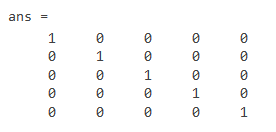

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

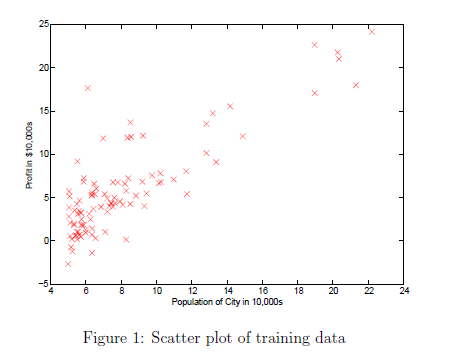

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

sqrErrors =   309.4785
   83.3606
  186.6502
  140.5173
   46.5574
  141.2770
   18.9077
  144.0000
   43.5428
   14.5664


ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

sqrErrors =    40.5998
    0.8560
    5.6416
    1.3280
   15.1812
   15.0528
   92.2464
   17.2740
   28.8767
   28.0116


ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

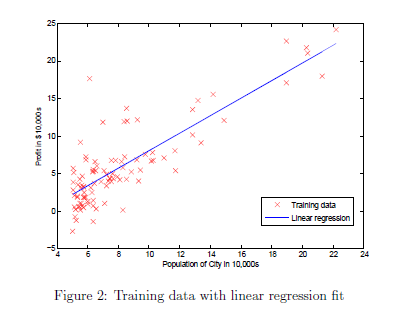    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

sqrErrors =   183.3844
   29.8184
   64.6176
   52.1356
    8.6246
   40.3372
    0.3532
   40.1656
    5.3036
    0.2080


sqrErrors =   164.4619
   23.1450
   49.5574
   40.9418
    5.0549
   28.8175
    2.1653
   28.4290
    2.3758
    0.0191


sqrErrors =   161.2636
   22.0716
   47.1008
   39.1151
    4.5298
   26.9816
    2.6437
   26.5628
    1.9826
    0.0582


sqrErrors =   160.7557
   21.9078
   46.6821
   38.8164
    4.4496
   26.6712
    2.7290
   26.2460
    1.9220
    0.0658


sqrErrors =   160.7228
   21.9031
   46.6194
   38.7850
    4.4456
   26.6257
    2.7394
   26.1982
    1.9170
    0.0657


sqrErrors =   160.7741
   21.9266
   46.6198
   38.8010
    4.4550
   26.6271
    2.7365
   26.1979
    1.9217
    0.0643


sqrErrors =   160.8403
   21.9550
   46.6313
   38.8254
    4.4668
   26.6369
    2.7312
   26.2061
    1.9282
    0.0626


sqrErrors =   160.9090
   21.9843
   46.6448
   38.8512
    4.4790
   26.6481
    2.7254
   26.2158
    1.9350
    0.0608


sqrErrors =   160.9781
   22.0138
   46.6587
   38.8772
    4.4913
   26.6595
    2.7197
   26.2258
    1.9419
    0.0591


sqrErrors =   161.0472
   22.0432
   46.6725
   38.9033
    4.5036
   26.6710
    2.7139
   26.2357
    1.9487
    0.0575


sqrErrors =   161.1162
   22.0726
   46.6864
   38.9293
    4.5159
   26.6825
    2.7081
   26.2457
    1.9556
    0.0558


sqrErrors =   161.1851
   22.1020
   46.7003
   38.9553
    4.5282
   26.6939
    2.7024
   26.2557
    1.9624
    0.0542


sqrErrors =   161.2538
   22.1313
   46.7141
   38.9813
    4.5405
   26.7054
    2.6966
   26.2656
    1.9693
    0.0526


sqrErrors =   161.3225
   22.1606
   46.7279
   39.0072
    4.5528
   26.7168
    2.6909
   26.2755
    1.9761
    0.0510


sqrErrors =   161.3910
   22.1898
   46.7417
   39.0331
    4.5650
   26.7282
    2.6852
   26.2854
    1.9830
    0.0495


sqrErrors =   161.4595
   22.2191
   46.7554
   39.0589
    4.5773
   26.7396
    2.6795
   26.2953
    1.9898
    0.0480


sqrErrors =   161.5278
   22.2483
   46.7691
   39.0847
    4.5896
   26.7510
    2.6738
   26.3052
    1.9967
    0.0465


sqrErrors =   161.5961
   22.2774
   46.7829
   39.1105
    4.6018
   26.7623
    2.6682
   26.3150
    2.0035
    0.0450


sqrErrors =   161.6642
   22.3066
   46.7965
   39.1362
    4.6141
   26.7736
    2.6625
   26.3249
    2.0104
    0.0436


sqrErrors =   161.7322
   22.3357
   46.8102
   39.1619
    4.6263
   26.7849
    2.6569
   26.3347
    2.0172
    0.0422


sqrErrors =   161.8001
   22.3647
   46.8238
   39.1875
    4.6386
   26.7962
    2.6513
   26.3445
    2.0240
    0.0408


sqrErrors =   161.8679
   22.3938
   46.8375
   39.2132
    4.6508
   26.8075
    2.6457
   26.3543
    2.0309
    0.0394


sqrErrors =   161.9356
   22.4228
   46.8511
   39.2387
    4.6630
   26.8188
    2.6402
   26.3641
    2.0377
    0.0381


sqrErrors =   162.0031
   22.4517
   46.8646
   39.2643
    4.6752
   26.8300
    2.6346
   26.3738
    2.0446
    0.0368


sqrErrors =   162.0706
   22.4806
   46.8782
   39.2898
    4.6875
   26.8412
    2.6291
   26.3836
    2.0514
    0.0355


sqrErrors =   162.1380
   22.5095
   46.8917
   39.3152
    4.6997
   26.8524
    2.6235
   26.3933
    2.0583
    0.0342


sqrErrors =   162.2052
   22.5384
   46.9052
   39.3407
    4.7119
   26.8636
    2.6180
   26.4030
    2.0651
    0.0330


sqrErrors =   162.2724
   22.5672
   46.9187
   39.3660
    4.7241
   26.8748
    2.6125
   26.4127
    2.0719
    0.0318


sqrErrors =   162.3394
   22.5960
   46.9322
   39.3914
    4.7363
   26.8860
    2.6070
   26.4224
    2.0788
    0.0306


sqrErrors =   162.4063
   22.6248
   46.9456
   39.4167
    4.7484
   26.8971
    2.6016
   26.4321
    2.0856
    0.0295


sqrErrors =   162.4732
   22.6535
   46.9590
   39.4420
    4.7606
   26.9082
    2.5961
   26.4417
    2.0925
    0.0283


sqrErrors =   162.5399
   22.6822
   46.9724
   39.4672
    4.7728
   26.9193
    2.5907
   26.4513
    2.0993
    0.0272


sqrErrors =   162.6065
   22.7109
   46.9858
   39.4924
    4.7850
   26.9304
    2.5853
   26.4610
    2.1061
    0.0261


sqrErrors =   162.6730
   22.7395
   46.9991
   39.5176
    4.7971
   26.9414
    2.5799
   26.4706
    2.1130
    0.0251


sqrErrors =   162.7394
   22.7681
   47.0125
   39.5427
    4.8093
   26.9525
    2.5745
   26.4802
    2.1198
    0.0240


sqrErrors =   162.8057
   22.7966
   47.0258
   39.5678
    4.8214
   26.9635
    2.5691
   26.4897
    2.1266
    0.0230


sqrErrors =   162.8719
   22.8252
   47.0391
   39.5928
    4.8335
   26.9745
    2.5638
   26.4993
    2.1335
    0.0220


sqrErrors =   162.9380
   22.8537
   47.0523
   39.6178
    4.8457
   26.9855
    2.5584
   26.5088
    2.1403
    0.0210


sqrErrors =   163.0039
   22.8821
   47.0656
   39.6428
    4.8578
   26.9965
    2.5531
   26.5184
    2.1471
    0.0201


sqrErrors =   163.0698
   22.9105
   47.0788
   39.6678
    4.8699
   27.0075
    2.5478
   26.5279
    2.1539
    0.0192


sqrErrors =   163.1356
   22.9389
   47.0920
   39.6927
    4.8820
   27.0184
    2.5425
   26.5374
    2.1608
    0.0183


sqrErrors =   163.2012
   22.9673
   47.1051
   39.7175
    4.8941
   27.0293
    2.5372
   26.5468
    2.1676
    0.0174


sqrErrors =   163.2668
   22.9956
   47.1183
   39.7424
    4.9062
   27.0402
    2.5319
   26.5563
    2.1744
    0.0165


sqrErrors =   163.3322
   23.0239
   47.1314
   39.7671
    4.9183
   27.0511
    2.5267
   26.5658
    2.1812
    0.0157


sqrErrors =   163.3976
   23.0522
   47.1445
   39.7919
    4.9304
   27.0620
    2.5215
   26.5752
    2.1880
    0.0149


sqrErrors =   163.4628
   23.0804
   47.1576
   39.8166
    4.9425
   27.0728
    2.5162
   26.5846
    2.1949
    0.0141


sqrErrors =   163.5280
   23.1086
   47.1707
   39.8413
    4.9546
   27.0837
    2.5110
   26.5940
    2.2017
    0.0134


sqrErrors = 97×1
  163.5930
   23.1367
   47.1837
   39.8659
    4.9666
   27.0945
    2.5058
   26.6034
    2.2085
    0.0126


sqrErrors = 97×1
  163.6579
   23.1649
   47.1968
   39.8905
    4.9787
   27.1053
    2.5007
   26.6128
    2.2153
    0.0119


sqrErrors = 97×1
  163.7227
   23.1929
   47.2098
   39.9151
    4.9907
   27.1161
    2.4955
   26.6221
    2.2221
    0.0112


sqrErrors = 97×1
  163.7875
   23.2210
   47.2227
   39.9396
    5.0028
   27.1268
    2.4904
   26.6315
    2.2289
    0.0105


sqrErrors = 97×1
  163.8521
   23.2490
   47.2357
   39.9641
    5.0148
   27.1376
    2.4852
   26.6408
    2.2357
    0.0099


sqrErrors = 97×1
  163.9166
   23.2770
   47.2486
   39.9886
    5.0268
   27.1483
    2.4801
   26.6501
    2.2425
    0.0093


sqrErrors = 97×1
  163.9810
   23.3050
   47.2615
   40.0130
    5.0388
   27.1590
    2.4750
   26.6594
    2.2493
    0.0087


sqrErrors = 97×1
  164.0453
   23.3329
   47.2744
   40.0374
    5.0509
   27.1697
    2.4699
   26.6687
    2.2561
    0.0081


sqrErrors = 97×1
  164.1095
   23.3608
   47.2873
   40.0618
    5.0629
   27.1804
    2.4648
   26.6779
    2.2629
    0.0075


sqrErrors = 97×1
  164.1736
   23.3886
   47.3001
   40.0861
    5.0749
   27.1911
    2.4598
   26.6872
    2.2697
    0.0070


sqrErrors = 97×1
  164.2376
   23.4164
   47.3130
   40.1103
    5.0868
   27.2017
    2.4547
   26.6964
    2.2765
    0.0064


sqrErrors = 97×1
  164.3015
   23.4442
   47.3258
   40.1346
    5.0988
   27.2123
    2.4497
   26.7057
    2.2833
    0.0059


sqrErrors = 97×1
  164.3653
   23.4720
   47.3386
   40.1588
    5.1108
   27.2229
    2.4447
   26.7149
    2.2901
    0.0055


sqrErrors = 97×1
  164.4289
   23.4997
   47.3513
   40.1830
    5.1228
   27.2335
    2.4397
   26.7240
    2.2969
    0.0050


sqrErrors = 97×1
  164.4925
   23.5274
   47.3641
   40.2071
    5.1347
   27.2441
    2.4347
   26.7332
    2.3036
    0.0046


sqrErrors = 97×1
  164.5560
   23.5550
   47.3768
   40.2312
    5.1467
   27.2547
    2.4297
   26.7424
    2.3104
    0.0042


sqrErrors = 97×1
  164.6194
   23.5826
   47.3895
   40.2552
    5.1586
   27.2652
    2.4248
   26.7515
    2.3172
    0.0038


sqrErrors = 97×1
  164.6827
   23.6102
   47.4022
   40.2793
    5.1706
   27.2757
    2.4198
   26.7607
    2.3240
    0.0034


sqrErrors = 97×1
  164.7458
   23.6378
   47.4148
   40.3032
    5.1825
   27.2863
    2.4149
   26.7698
    2.3308
    0.0030


sqrErrors = 97×1
  164.8089
   23.6653
   47.4275
   40.3272
    5.1944
   27.2967
    2.4100
   26.7789
    2.3375
    0.0027


sqrErrors = 97×1
  164.8719
   23.6928
   47.4401
   40.3511
    5.2063
   27.3072
    2.4051
   26.7880
    2.3443
    0.0024


sqrErrors = 97×1
  164.9347
   23.7202
   47.4527
   40.3750
    5.2182
   27.3177
    2.4002
   26.7970
    2.3511
    0.0021


sqrErrors = 97×1
  164.9975
   23.7476
   47.4652
   40.3988
    5.2301
   27.3281
    2.3953
   26.8061
    2.3578
    0.0018


sqrErrors = 97×1
  165.0602
   23.7750
   47.4778
   40.4226
    5.2420
   27.3385
    2.3904
   26.8151
    2.3646
    0.0016


sqrErrors = 97×1
  165.1227
   23.8024
   47.4903
   40.4464
    5.2539
   27.3489
    2.3856
   26.8242
    2.3714
    0.0013


sqrErrors = 97×1
  165.1852
   23.8297
   47.5028
   40.4701
    5.2658
   27.3593
    2.3807
   26.8332
    2.3781
    0.0011


sqrErrors = 97×1
  165.2476
   23.8570
   47.5153
   40.4938
    5.2776
   27.3697
    2.3759
   26.8422
    2.3849
    0.0009


sqrErrors = 97×1
  165.3098
   23.8842
   47.5278
   40.5175
    5.2895
   27.3801
    2.3711
   26.8512
    2.3916
    0.0007


sqrErrors = 97×1
  165.3720
   23.9114
   47.5402
   40.5411
    5.3013
   27.3904
    2.3663
   26.8601
    2.3984
    0.0006


sqrErrors = 97×1
  165.4341
   23.9386
   47.5527
   40.5647
    5.3132
   27.4007
    2.3615
   26.8691
    2.4051
    0.0004


sqrErrors = 97×1
  165.4960
   23.9657
   47.5651
   40.5883
    5.3250
   27.4110
    2.3568
   26.8780
    2.4119
    0.0003


sqrErrors = 97×1
  165.5579
   23.9929
   47.5774
   40.6118
    5.3368
   27.4213
    2.3520
   26.8869
    2.4186
    0.0002


sqrErrors = 97×1
  165.6196
   24.0199
   47.5898
   40.6353
    5.3487
   27.4316
    2.3473
   26.8958
    2.4253
    0.0001


sqrErrors = 97×1
  165.6813
   24.0470
   47.6022
   40.6587
    5.3605
   27.4419
    2.3425
   26.9047
    2.4321
    0.0001


sqrErrors = 97×1
  165.7429
   24.0740
   47.6145
   40.6821
    5.3723
   27.4521
    2.3378
   26.9136
    2.4388
    0.0000


sqrErrors = 97×1
  165.8043
   24.1010
   47.6268
   40.7055
    5.3841
   27.4623
    2.3331
   26.9225
    2.4455
    0.0000


sqrErrors = 97×1
  165.8657
   24.1279
   47.6391
   40.7288
    5.3958
   27.4725
    2.3284
   26.9313
    2.4523
    0.0000


sqrErrors = 97×1
  165.9270
   24.1548
   47.6513
   40.7522
    5.4076
   27.4827
    2.3237
   26.9402
    2.4590
    0.0000


sqrErrors = 97×1
  165.9881
   24.1817
   47.6636
   40.7754
    5.4194
   27.4929
    2.3191
   26.9490
    2.4657
    0.0000


sqrErrors = 97×1
  166.0492
   24.2086
   47.6758
   40.7987
    5.4311
   27.5031
    2.3144
   26.9578
    2.4724
    0.0001


sqrErrors = 97×1
  166.1102
   24.2354
   47.6880
   40.8219
    5.4429
   27.5132
    2.3098
   26.9666
    2.4791
    0.0002


sqrErrors = 97×1
  166.1710
   24.2621
   47.7002
   40.8450
    5.4546
   27.5233
    2.3052
   26.9754
    2.4859
    0.0002


sqrErrors = 97×1
  166.2318
   24.2889
   47.7123
   40.8682
    5.4664
   27.5334
    2.3006
   26.9841
    2.4926
    0.0003


sqrErrors = 97×1
  166.2925
   24.3156
   47.7245
   40.8912
    5.4781
   27.5435
    2.2960
   26.9929
    2.4993
    0.0005


sqrErrors = 97×1
  166.3530
   24.3423
   47.7366
   40.9143
    5.4898
   27.5536
    2.2914
   27.0016
    2.5060
    0.0006


sqrErrors = 97×1
  166.4135
   24.3689
   47.7487
   40.9373
    5.5015
   27.5637
    2.2868
   27.0104
    2.5127
    0.0008


sqrErrors = 97×1
  166.4739
   24.3955
   47.7607
   40.9603
    5.5132
   27.5737
    2.2822
   27.0191
    2.5194
    0.0009


sqrErrors = 97×1
  166.5342
   24.4221
   47.7728
   40.9833
    5.5249
   27.5837
    2.2777
   27.0278
    2.5261
    0.0011


sqrErrors = 97×1
  166.5943
   24.4486
   47.7848
   41.0062
    5.5366
   27.5938
    2.2732
   27.0364
    2.5328
    0.0013


sqrErrors = 97×1
  166.6544
   24.4752
   47.7969
   41.0291
    5.5482
   27.6037
    2.2686
   27.0451
    2.5394
    0.0016


sqrErrors = 97×1
  166.7144
   24.5016
   47.8089
   41.0519
    5.5599
   27.6137
    2.2641
   27.0537
    2.5461
    0.0018


sqrErrors = 97×1
  166.7743
   24.5281
   47.8208
   41.0747
    5.5716
   27.6237
    2.2596
   27.0624
    2.5528
    0.0021


sqrErrors = 97×1
  166.8341
   24.5545
   47.8328
   41.0975
    5.5832
   27.6336
    2.2552
   27.0710
    2.5595
    0.0023


sqrErrors = 97×1
  166.8938
   24.5809
   47.8447
   41.1203
    5.5948
   27.6436
    2.2507
   27.0796
    2.5662
    0.0026


sqrErrors = 97×1
  166.9534
   24.6072
   47.8566
   41.1430
    5.6065
   27.6535
    2.2462
   27.0882
    2.5728
    0.0029


sqrErrors = 97×1
  167.0129
   24.6335
   47.8685
   41.1657
    5.6181
   27.6634
    2.2418
   27.0968
    2.5795
    0.0033


sqrErrors = 97×1
  167.0723
   24.6598
   47.8804
   41.1883
    5.6297
   27.6733
    2.2374
   27.1053
    2.5862
    0.0036


sqrErrors = 97×1
  167.1316
   24.6860
   47.8923
   41.2109
    5.6413
   27.6831
    2.2329
   27.1139
    2.5928
    0.0040


sqrErrors = 97×1
  167.1908
   24.7122
   47.9041
   41.2335
    5.6529
   27.6930
    2.2285
   27.1224
    2.5995
    0.0043


sqrErrors = 97×1
  167.2499
   24.7384
   47.9159
   41.2560
    5.6645
   27.7028
    2.2241
   27.1310
    2.6061
    0.0047


sqrErrors = 97×1
  167.3089
   24.7645
   47.9277
   41.2785
    5.6760
   27.7126
    2.2197
   27.1395
    2.6128
    0.0051


sqrErrors = 97×1
  167.3679
   24.7907
   47.9395
   41.3010
    5.6876
   27.7224
    2.2154
   27.1480
    2.6194
    0.0056


sqrErrors = 97×1
  167.4267
   24.8167
   47.9512
   41.3234
    5.6992
   27.7322
    2.2110
   27.1564
    2.6261
    0.0060


sqrErrors = 97×1
  167.4854
   24.8428
   47.9630
   41.3458
    5.7107
   27.7420
    2.2067
   27.1649
    2.6327
    0.0065


sqrErrors = 97×1
  167.5440
   24.8688
   47.9747
   41.3682
    5.7222
   27.7517
    2.2023
   27.1734
    2.6393
    0.0069


sqrErrors = 97×1
  167.6026
   24.8948
   47.9864
   41.3905
    5.7338
   27.7615
    2.1980
   27.1818
    2.6460
    0.0074


sqrErrors = 97×1
  167.6610
   24.9207
   47.9981
   41.4128
    5.7453
   27.7712
    2.1937
   27.1902
    2.6526
    0.0079


sqrErrors = 97×1
  167.7194
   24.9466
   48.0097
   41.4351
    5.7568
   27.7809
    2.1894
   27.1986
    2.6592
    0.0085


sqrErrors = 97×1
  167.7776
   24.9725
   48.0214
   41.4573
    5.7683
   27.7906
    2.1851
   27.2070
    2.6659
    0.0090


sqrErrors = 97×1
  167.8358
   24.9983
   48.0330
   41.4795
    5.7798
   27.8003
    2.1808
   27.2154
    2.6725
    0.0095


sqrErrors = 97×1
  167.8939
   25.0241
   48.0446
   41.5017
    5.7913
   27.8099
    2.1766
   27.2238
    2.6791
    0.0101


sqrErrors = 97×1
  167.9518
   25.0499
   48.0562
   41.5238
    5.8027
   27.8196
    2.1723
   27.2321
    2.6857
    0.0107


sqrErrors = 97×1
  168.0097
   25.0756
   48.0677
   41.5459
    5.8142
   27.8292
    2.1681
   27.2405
    2.6923
    0.0113


sqrErrors = 97×1
  168.0675
   25.1014
   48.0793
   41.5679
    5.8257
   27.8388
    2.1638
   27.2488
    2.6989
    0.0119


sqrErrors = 97×1
  168.1252
   25.1270
   48.0908
   41.5900
    5.8371
   27.8484
    2.1596
   27.2571
    2.7055
    0.0125


sqrErrors = 97×1
  168.1828
   25.1527
   48.1023
   41.6119
    5.8485
   27.8580
    2.1554
   27.2654
    2.7121
    0.0132


sqrErrors = 97×1
  168.2403
   25.1783
   48.1138
   41.6339
    5.8600
   27.8676
    2.1512
   27.2737
    2.7187
    0.0138


sqrErrors = 97×1
  168.2977
   25.2039
   48.1252
   41.6558
    5.8714
   27.8771
    2.1470
   27.2820
    2.7253
    0.0145


sqrErrors = 97×1
  168.3550
   25.2294
   48.1367
   41.6777
    5.8828
   27.8866
    2.1429
   27.2902
    2.7319
    0.0152


sqrErrors = 97×1
  168.4122
   25.2549
   48.1481
   41.6996
    5.8942
   27.8962
    2.1387
   27.2985
    2.7384
    0.0159


sqrErrors = 97×1
  168.4693
   25.2804
   48.1595
   41.7214
    5.9056
   27.9057
    2.1346
   27.3067
    2.7450
    0.0166


sqrErrors = 97×1
  168.5263
   25.3058
   48.1709
   41.7432
    5.9169
   27.9151
    2.1304
   27.3149
    2.7516
    0.0173


sqrErrors = 97×1
  168.5833
   25.3312
   48.1823
   41.7649
    5.9283
   27.9246
    2.1263
   27.3232
    2.7581
    0.0181


sqrErrors = 97×1
  168.6401
   25.3566
   48.1936
   41.7867
    5.9397
   27.9341
    2.1222
   27.3313
    2.7647
    0.0188


sqrErrors = 97×1
  168.6969
   25.3820
   48.2050
   41.8083
    5.9510
   27.9435
    2.1181
   27.3395
    2.7713
    0.0196


sqrErrors = 97×1
  168.7535
   25.4073
   48.2163
   41.8300
    5.9624
   27.9529
    2.1140
   27.3477
    2.7778
    0.0204


sqrErrors = 97×1
  168.8101
   25.4325
   48.2276
   41.8516
    5.9737
   27.9624
    2.1099
   27.3558
    2.7844
    0.0212


sqrErrors = 97×1
  168.8666
   25.4578
   48.2388
   41.8732
    5.9850
   27.9717
    2.1059
   27.3640
    2.7909
    0.0220


sqrErrors = 97×1
  168.9230
   25.4830
   48.2501
   41.8948
    5.9963
   27.9811
    2.1018
   27.3721
    2.7975
    0.0228


sqrErrors = 97×1
  168.9792
   25.5082
   48.2613
   41.9163
    6.0076
   27.9905
    2.0978
   27.3802
    2.8040
    0.0237


sqrErrors = 97×1
  169.0354
   25.5333
   48.2725
   41.9378
    6.0189
   27.9998
    2.0937
   27.3883
    2.8105
    0.0245


sqrErrors = 97×1
  169.0915
   25.5584
   48.2837
   41.9592
    6.0302
   28.0092
    2.0897
   27.3964
    2.8171
    0.0254


sqrErrors = 97×1
  169.1476
   25.5835
   48.2949
   41.9806
    6.0415
   28.0185
    2.0857
   27.4045
    2.8236
    0.0263


sqrErrors = 97×1
  169.2035
   25.6086
   48.3061
   42.0020
    6.0527
   28.0278
    2.0817
   27.4125
    2.8301
    0.0272


sqrErrors = 97×1
  169.2593
   25.6336
   48.3172
   42.0234
    6.0640
   28.0371
    2.0777
   27.4206
    2.8366
    0.0281


sqrErrors = 97×1
  169.3150
   25.6586
   48.3283
   42.0447
    6.0752
   28.0464
    2.0737
   27.4286
    2.8431
    0.0290


sqrErrors = 97×1
  169.3707
   25.6835
   48.3394
   42.0660
    6.0864
   28.0556
    2.0698
   27.4366
    2.8496
    0.0299


sqrErrors = 97×1
  169.4262
   25.7084
   48.3505
   42.0872
    6.0977
   28.0649
    2.0658
   27.4446
    2.8562
    0.0309


sqrErrors = 97×1
  169.4817
   25.7333
   48.3616
   42.1085
    6.1089
   28.0741
    2.0619
   27.4526
    2.8627
    0.0318


sqrErrors = 97×1
  169.5371
   25.7582
   48.3726
   42.1297
    6.1201
   28.0833
    2.0579
   27.4606
    2.8691
    0.0328


sqrErrors = 97×1
  169.5924
   25.7830
   48.3836
   42.1508
    6.1313
   28.0925
    2.0540
   27.4685
    2.8756
    0.0338


sqrErrors = 97×1
  169.6476
   25.8078
   48.3947
   42.1719
    6.1425
   28.1017
    2.0501
   27.4765
    2.8821
    0.0348


sqrErrors = 97×1
  169.7027
   25.8325
   48.4056
   42.1930
    6.1536
   28.1108
    2.0462
   27.4844
    2.8886
    0.0358


sqrErrors = 97×1
  169.7577
   25.8572
   48.4166
   42.2141
    6.1648
   28.1200
    2.0423
   27.4924
    2.8951
    0.0368


sqrErrors = 97×1
  169.8126
   25.8819
   48.4276
   42.2351
    6.1759
   28.1291
    2.0384
   27.5003
    2.9016
    0.0379


sqrErrors = 97×1
  169.8674
   25.9066
   48.4385
   42.2561
    6.1871
   28.1382
    2.0345
   27.5082
    2.9080
    0.0389


sqrErrors = 97×1
  169.9222
   25.9312
   48.4494
   42.2771
    6.1982
   28.1474
    2.0307
   27.5161
    2.9145
    0.0400


sqrErrors = 97×1
  169.9768
   25.9558
   48.4603
   42.2980
    6.2093
   28.1564
    2.0268
   27.5239
    2.9210
    0.0411


sqrErrors = 97×1
  170.0314
   25.9803
   48.4712
   42.3189
    6.2204
   28.1655
    2.0230
   27.5318
    2.9274
    0.0422


sqrErrors = 97×1
  170.0858
   26.0049
   48.4821
   42.3397
    6.2315
   28.1746
    2.0192
   27.5396
    2.9339
    0.0433


sqrErrors = 97×1
  170.1402
   26.0293
   48.4929
   42.3606
    6.2426
   28.1836
    2.0154
   27.5475
    2.9403
    0.0444


sqrErrors = 97×1
  170.1945
   26.0538
   48.5037
   42.3814
    6.2537
   28.1927
    2.0115
   27.5553
    2.9467
    0.0455


sqrErrors = 97×1
  170.2487
   26.0782
   48.5145
   42.4021
    6.2648
   28.2017
    2.0077
   27.5631
    2.9532
    0.0466


sqrErrors = 97×1
  170.3028
   26.1026
   48.5253
   42.4229
    6.2758
   28.2107
    2.0040
   27.5709
    2.9596
    0.0478


sqrErrors = 97×1
  170.3569
   26.1270
   48.5361
   42.4436
    6.2869
   28.2197
    2.0002
   27.5787
    2.9660
    0.0489


sqrErrors = 97×1
  170.4108
   26.1513
   48.5468
   42.4642
    6.2979
   28.2286
    1.9964
   27.5864
    2.9725
    0.0501


sqrErrors = 97×1
  170.4646
   26.1756
   48.5576
   42.4849
    6.3090
   28.2376
    1.9927
   27.5942
    2.9789
    0.0513


sqrErrors = 97×1
  170.5184
   26.1999
   48.5683
   42.5055
    6.3200
   28.2465
    1.9889
   27.6019
    2.9853
    0.0525


sqrErrors = 97×1
  170.5721
   26.2241
   48.5790
   42.5260
    6.3310
   28.2555
    1.9852
   27.6097
    2.9917
    0.0537


sqrErrors = 97×1
  170.6257
   26.2483
   48.5897
   42.5466
    6.3420
   28.2644
    1.9815
   27.6174
    2.9981
    0.0549


sqrErrors = 97×1
  170.6792
   26.2725
   48.6003
   42.5671
    6.3530
   28.2733
    1.9778
   27.6251
    3.0045
    0.0561


sqrErrors = 97×1
  170.7326
   26.2966
   48.6110
   42.5876
    6.3640
   28.2822
    1.9740
   27.6328
    3.0109
    0.0574


sqrErrors = 97×1
  170.7859
   26.3207
   48.6216
   42.6080
    6.3749
   28.2910
    1.9704
   27.6405
    3.0173
    0.0586


sqrErrors = 97×1
  170.8391
   26.3447
   48.6322
   42.6284
    6.3859
   28.2999
    1.9667
   27.6481
    3.0237
    0.0599


sqrErrors = 97×1
  170.8922
   26.3688
   48.6428
   42.6488
    6.3968
   28.3087
    1.9630
   27.6558
    3.0301
    0.0612


sqrErrors = 97×1
  170.9453
   26.3928
   48.6534
   42.6692
    6.4078
   28.3176
    1.9593
   27.6634
    3.0364
    0.0625


sqrErrors = 97×1
  170.9983
   26.4168
   48.6639
   42.6895
    6.4187
   28.3264
    1.9557
   27.6710
    3.0428
    0.0638


sqrErrors = 97×1
  171.0512
   26.4407
   48.6744
   42.7098
    6.4296
   28.3352
    1.9520
   27.6787
    3.0492
    0.0651


sqrErrors = 97×1
  171.1039
   26.4646
   48.6850
   42.7300
    6.4405
   28.3440
    1.9484
   27.6863
    3.0555
    0.0664


sqrErrors = 97×1
  171.1567
   26.4885
   48.6955
   42.7502
    6.4514
   28.3527
    1.9448
   27.6938
    3.0619
    0.0677


sqrErrors = 97×1
  171.2093
   26.5123
   48.7059
   42.7704
    6.4623
   28.3615
    1.9412
   27.7014
    3.0683
    0.0691


sqrErrors = 97×1
  171.2618
   26.5361
   48.7164
   42.7906
    6.4732
   28.3702
    1.9376
   27.7090
    3.0746
    0.0704


sqrErrors = 97×1
  171.3142
   26.5599
   48.7268
   42.8107
    6.4840
   28.3789
    1.9340
   27.7165
    3.0809
    0.0718


sqrErrors = 97×1
  171.3666
   26.5836
   48.7373
   42.8308
    6.4949
   28.3877
    1.9304
   27.7241
    3.0873
    0.0731


sqrErrors = 97×1
  171.4189
   26.6073
   48.7477
   42.8508
    6.5057
   28.3963
    1.9268
   27.7316
    3.0936
    0.0745


sqrErrors = 97×1
  171.4711
   26.6310
   48.7581
   42.8709
    6.5166
   28.4050
    1.9233
   27.7391
    3.0999
    0.0759


sqrErrors = 97×1
  171.5232
   26.6547
   48.7685
   42.8909
    6.5274
   28.4137
    1.9197
   27.7466
    3.1063
    0.0773


sqrErrors = 97×1
  171.5752
   26.6783
   48.7788
   42.9108
    6.5382
   28.4223
    1.9162
   27.7541
    3.1126
    0.0787


sqrErrors = 97×1
  171.6271
   26.7019
   48.7891
   42.9308
    6.5490
   28.4310
    1.9126
   27.7616
    3.1189
    0.0802


sqrErrors = 97×1
  171.6790
   26.7254
   48.7995
   42.9507
    6.5598
   28.4396
    1.9091
   27.7690
    3.1252
    0.0816


sqrErrors = 97×1
  171.7307
   26.7489
   48.8098
   42.9706
    6.5706
   28.4482
    1.9056
   27.7765
    3.1315
    0.0830


sqrErrors = 97×1
  171.7824
   26.7724
   48.8201
   42.9904
    6.5813
   28.4568
    1.9021
   27.7839
    3.1378
    0.0845


sqrErrors = 97×1
  171.8340
   26.7959
   48.8303
   43.0102
    6.5921
   28.4654
    1.8986
   27.7914
    3.1441
    0.0860


sqrErrors = 97×1
  171.8855
   26.8193
   48.8406
   43.0300
    6.6028
   28.4740
    1.8951
   27.7988
    3.1504
    0.0874


sqrErrors = 97×1
  171.9369
   26.8427
   48.8508
   43.0497
    6.6136
   28.4825
    1.8916
   27.8062
    3.1567
    0.0889


sqrErrors = 97×1
  171.9882
   26.8660
   48.8610
   43.0695
    6.6243
   28.4911
    1.8881
   27.8136
    3.1629
    0.0904


sqrErrors = 97×1
  172.0395
   26.8894
   48.8712
   43.0892
    6.6350
   28.4996
    1.8847
   27.8209
    3.1692
    0.0919


sqrErrors = 97×1
  172.0906
   26.9127
   48.8814
   43.1088
    6.6457
   28.5081
    1.8812
   27.8283
    3.1755
    0.0934


sqrErrors = 97×1
  172.1417
   26.9359
   48.8916
   43.1284
    6.6564
   28.5166
    1.8778
   27.8357
    3.1817
    0.0950


sqrErrors = 97×1
  172.1927
   26.9592
   48.9017
   43.1480
    6.6671
   28.5251
    1.8744
   27.8430
    3.1880
    0.0965


sqrErrors = 97×1
  172.2436
   26.9824
   48.9119
   43.1676
    6.6778
   28.5335
    1.8709
   27.8503
    3.1943
    0.0980


sqrErrors = 97×1
  172.2944
   27.0055
   48.9220
   43.1871
    6.6884
   28.5420
    1.8675
   27.8576
    3.2005
    0.0996


sqrErrors = 97×1
  172.3452
   27.0287
   48.9321
   43.2066
    6.6991
   28.5504
    1.8641
   27.8650
    3.2067
    0.1011


sqrErrors = 97×1
  172.3958
   27.0518
   48.9422
   43.2261
    6.7097
   28.5589
    1.8607
   27.8722
    3.2130
    0.1027


sqrErrors = 97×1
  172.4464
   27.0748
   48.9522
   43.2455
    6.7204
   28.5673
    1.8573
   27.8795
    3.2192
    0.1043


sqrErrors = 97×1
  172.4969
   27.0979
   48.9623
   43.2649
    6.7310
   28.5757
    1.8540
   27.8868
    3.2254
    0.1059


sqrErrors = 97×1
  172.5473
   27.1209
   48.9723
   43.2843
    6.7416
   28.5841
    1.8506
   27.8940
    3.2317
    0.1075


sqrErrors = 97×1
  172.5976
   27.1439
   48.9823
   43.3037
    6.7522
   28.5924
    1.8472
   27.9013
    3.2379
    0.1091


sqrErrors = 97×1
  172.6478
   27.1668
   48.9923
   43.3230
    6.7628
   28.6008
    1.8439
   27.9085
    3.2441
    0.1107


sqrErrors = 97×1
  172.6980
   27.1897
   49.0023
   43.3423
    6.7734
   28.6091
    1.8406
   27.9157
    3.2503
    0.1123


sqrErrors = 97×1
  172.7481
   27.2126
   49.0122
   43.3615
    6.7839
   28.6175
    1.8372
   27.9229
    3.2565
    0.1140


sqrErrors = 97×1
  172.7980
   27.2354
   49.0222
   43.3808
    6.7945
   28.6258
    1.8339
   27.9301
    3.2627
    0.1156


sqrErrors = 97×1
  172.8480
   27.2583
   49.0321
   43.4000
    6.8050
   28.6341
    1.8306
   27.9373
    3.2689
    0.1172


sqrErrors = 97×1
  172.8978
   27.2810
   49.0420
   43.4191
    6.8155
   28.6424
    1.8273
   27.9445
    3.2751
    0.1189


sqrErrors = 97×1
  172.9475
   27.3038
   49.0519
   43.4383
    6.8261
   28.6507
    1.8240
   27.9516
    3.2812
    0.1206


sqrErrors = 97×1
  172.9972
   27.3265
   49.0618
   43.4574
    6.8366
   28.6589
    1.8207
   27.9588
    3.2874
    0.1222


sqrErrors = 97×1
  173.0467
   27.3492
   49.0716
   43.4764
    6.8471
   28.6672
    1.8174
   27.9659
    3.2936
    0.1239


sqrErrors = 97×1
  173.0962
   27.3719
   49.0815
   43.4955
    6.8576
   28.6754
    1.8142
   27.9730
    3.2997
    0.1256


sqrErrors = 97×1
  173.1456
   27.3945
   49.0913
   43.5145
    6.8680
   28.6836
    1.8109
   27.9802
    3.3059
    0.1273


sqrErrors = 97×1
  173.1950
   27.4171
   49.1011
   43.5335
    6.8785
   28.6918
    1.8077
   27.9873
    3.3120
    0.1290


sqrErrors = 97×1
  173.2442
   27.4397
   49.1109
   43.5524
    6.8890
   28.7000
    1.8044
   27.9943
    3.3182
    0.1308


sqrErrors = 97×1
  173.2934
   27.4622
   49.1207
   43.5714
    6.8994
   28.7082
    1.8012
   28.0014
    3.3243
    0.1325


sqrErrors = 97×1
  173.3425
   27.4847
   49.1304
   43.5903
    6.9099
   28.7164
    1.7980
   28.0085
    3.3305
    0.1342


sqrErrors = 97×1
  173.3915
   27.5072
   49.1402
   43.6091
    6.9203
   28.7245
    1.7947
   28.0155
    3.3366
    0.1360


sqrErrors = 97×1
  173.4404
   27.5296
   49.1499
   43.6280
    6.9307
   28.7327
    1.7915
   28.0226
    3.3427
    0.1377


sqrErrors = 97×1
  173.4892
   27.5520
   49.1596
   43.6468
    6.9411
   28.7408
    1.7883
   28.0296
    3.3488
    0.1395


sqrErrors = 97×1
  173.5380
   27.5744
   49.1693
   43.6655
    6.9515
   28.7489
    1.7852
   28.0366
    3.3550
    0.1412


sqrErrors = 97×1
  173.5867
   27.5967
   49.1790
   43.6843
    6.9619
   28.7570
    1.7820
   28.0436
    3.3611
    0.1430


sqrErrors = 97×1
  173.6353
   27.6191
   49.1886
   43.7030
    6.9722
   28.7651
    1.7788
   28.0506
    3.3672
    0.1448


sqrErrors = 97×1
  173.6838
   27.6413
   49.1983
   43.7217
    6.9826
   28.7731
    1.7756
   28.0576
    3.3733
    0.1466


sqrErrors = 97×1
  173.7322
   27.6636
   49.2079
   43.7403
    6.9929
   28.7812
    1.7725
   28.0646
    3.3794
    0.1484


sqrErrors = 97×1
  173.7806
   27.6858
   49.2175
   43.7590
    7.0033
   28.7892
    1.7693
   28.0715
    3.3854
    0.1502


sqrErrors = 97×1
  173.8288
   27.7080
   49.2271
   43.7776
    7.0136
   28.7973
    1.7662
   28.0785
    3.3915
    0.1520


sqrErrors = 97×1
  173.8770
   27.7302
   49.2367
   43.7961
    7.0239
   28.8053
    1.7631
   28.0854
    3.3976
    0.1538


sqrErrors = 97×1
  173.9251
   27.7523
   49.2463
   43.8147
    7.0342
   28.8133
    1.7599
   28.0923
    3.4037
    0.1557


sqrErrors = 97×1
  173.9732
   27.7744
   49.2558
   43.8332
    7.0445
   28.8213
    1.7568
   28.0992
    3.4097
    0.1575


sqrErrors = 97×1
  174.0211
   27.7964
   49.2653
   43.8516
    7.0548
   28.8293
    1.7537
   28.1061
    3.4158
    0.1593


sqrErrors = 97×1
  174.0690
   27.8185
   49.2748
   43.8701
    7.0651
   28.8372
    1.7506
   28.1130
    3.4218
    0.1612


sqrErrors = 97×1
  174.1168
   27.8405
   49.2843
   43.8885
    7.0753
   28.8452
    1.7475
   28.1199
    3.4279
    0.1631


sqrErrors = 97×1
  174.1645
   27.8625
   49.2938
   43.9069
    7.0856
   28.8531
    1.7445
   28.1267
    3.4339
    0.1649


sqrErrors = 97×1
  174.2121
   27.8844
   49.3033
   43.9253
    7.0958
   28.8610
    1.7414
   28.1336
    3.4400
    0.1668


sqrErrors = 97×1
  174.2597
   27.9063
   49.3127
   43.9436
    7.1060
   28.8690
    1.7383
   28.1404
    3.4460
    0.1687


sqrErrors = 97×1
  174.3072
   27.9282
   49.3222
   43.9619
    7.1162
   28.8769
    1.7353
   28.1473
    3.4520
    0.1706


sqrErrors = 97×1
  174.3545
   27.9500
   49.3316
   43.9802
    7.1264
   28.8847
    1.7322
   28.1541
    3.4580
    0.1725


sqrErrors = 97×1
  174.4019
   27.9719
   49.3410
   43.9984
    7.1366
   28.8926
    1.7292
   28.1609
    3.4641
    0.1744


sqrErrors = 97×1
  174.4491
   27.9936
   49.3504
   44.0166
    7.1468
   28.9005
    1.7262
   28.1677
    3.4701
    0.1763


sqrErrors = 97×1
  174.4963
   28.0154
   49.3597
   44.0348
    7.1570
   28.9083
    1.7231
   28.1745
    3.4761
    0.1782


sqrErrors = 97×1
  174.5433
   28.0371
   49.3691
   44.0530
    7.1671
   28.9161
    1.7201
   28.1812
    3.4821
    0.1801


sqrErrors = 97×1
  174.5903
   28.0588
   49.3784
   44.0711
    7.1773
   28.9240
    1.7171
   28.1880
    3.4881
    0.1820


sqrErrors = 97×1
  174.6373
   28.0805
   49.3877
   44.0892
    7.1874
   28.9318
    1.7141
   28.1947
    3.4940
    0.1840


sqrErrors = 97×1
  174.6841
   28.1021
   49.3970
   44.1073
    7.1975
   28.9396
    1.7111
   28.2015
    3.5000
    0.1859


sqrErrors = 97×1
  174.7309
   28.1237
   49.4063
   44.1253
    7.2077
   28.9473
    1.7081
   28.2082
    3.5060
    0.1879


sqrErrors = 97×1
  174.7776
   28.1453
   49.4156
   44.1433
    7.2178
   28.9551
    1.7052
   28.2149
    3.5120
    0.1898


sqrErrors = 97×1
  174.8242
   28.1668
   49.4248
   44.1613
    7.2279
   28.9629
    1.7022
   28.2216
    3.5179
    0.1918


sqrErrors = 97×1
  174.8707
   28.1883
   49.4341
   44.1792
    7.2379
   28.9706
    1.6992
   28.2283
    3.5239
    0.1938


sqrErrors = 97×1
  174.9172
   28.2098
   49.4433
   44.1972
    7.2480
   28.9783
    1.6963
   28.2350
    3.5298
    0.1957


sqrErrors = 97×1
  174.9635
   28.2313
   49.4525
   44.2151
    7.2581
   28.9861
    1.6934
   28.2417
    3.5358
    0.1977


sqrErrors = 97×1
  175.0098
   28.2527
   49.4617
   44.2329
    7.2681
   28.9938
    1.6904
   28.2483
    3.5417
    0.1997


sqrErrors = 97×1
  175.0561
   28.2741
   49.4709
   44.2508
    7.2781
   29.0014
    1.6875
   28.2550
    3.5477
    0.2017


sqrErrors = 97×1
  175.1022
   28.2954
   49.4800
   44.2686
    7.2882
   29.0091
    1.6846
   28.2616
    3.5536
    0.2037


sqrErrors = 97×1
  175.1483
   28.3168
   49.4892
   44.2864
    7.2982
   29.0168
    1.6817
   28.2682
    3.5595
    0.2057


sqrErrors = 97×1
  175.1943
   28.3381
   49.4983
   44.3041
    7.3082
   29.0244
    1.6788
   28.2749
    3.5654
    0.2077


sqrErrors = 97×1
  175.2402
   28.3593
   49.5074
   44.3219
    7.3182
   29.0321
    1.6759
   28.2815
    3.5713
    0.2097


sqrErrors = 97×1
  175.2860
   28.3806
   49.5165
   44.3395
    7.3282
   29.0397
    1.6730
   28.2880
    3.5772
    0.2118


sqrErrors = 97×1
  175.3318
   28.4018
   49.5256
   44.3572
    7.3381
   29.0473
    1.6701
   28.2946
    3.5831
    0.2138


sqrErrors = 97×1
  175.3775
   28.4229
   49.5347
   44.3749
    7.3481
   29.0549
    1.6672
   28.3012
    3.5890
    0.2158


sqrErrors = 97×1
  175.4231
   28.4441
   49.5437
   44.3925
    7.3580
   29.0625
    1.6644
   28.3078
    3.5949
    0.2179


sqrErrors = 97×1
  175.4686
   28.4652
   49.5528
   44.4101
    7.3680
   29.0701
    1.6615
   28.3143
    3.6008
    0.2199


sqrErrors = 97×1
  175.5141
   28.4863
   49.5618
   44.4276
    7.3779
   29.0776
    1.6587
   28.3208
    3.6067
    0.2220


sqrErrors = 97×1
  175.5594
   28.5073
   49.5708
   44.4451
    7.3878
   29.0852
    1.6558
   28.3274
    3.6125
    0.2240


sqrErrors = 97×1
  175.6047
   28.5284
   49.5798
   44.4626
    7.3977
   29.0927
    1.6530
   28.3339
    3.6184
    0.2261


sqrErrors = 97×1
  175.6500
   28.5494
   49.5888
   44.4801
    7.4076
   29.1003
    1.6502
   28.3404
    3.6243
    0.2282


sqrErrors = 97×1
  175.6951
   28.5703
   49.5977
   44.4976
    7.4175
   29.1078
    1.6473
   28.3469
    3.6301
    0.2303


sqrErrors = 97×1
  175.7402
   28.5913
   49.6067
   44.5150
    7.4273
   29.1153
    1.6445
   28.3534
    3.6360
    0.2323


sqrErrors = 97×1
  175.7852
   28.6122
   49.6156
   44.5324
    7.4372
   29.1228
    1.6417
   28.3598
    3.6418
    0.2344


sqrErrors = 97×1
  175.8301
   28.6330
   49.6245
   44.5497
    7.4470
   29.1302
    1.6389
   28.3663
    3.6477
    0.2365


sqrErrors = 97×1
  175.8750
   28.6539
   49.6334
   44.5670
    7.4569
   29.1377
    1.6361
   28.3727
    3.6535
    0.2386


sqrErrors = 97×1
  175.9198
   28.6747
   49.6423
   44.5843
    7.4667
   29.1451
    1.6333
   28.3792
    3.6593
    0.2407


sqrErrors = 97×1
  175.9645
   28.6955
   49.6511
   44.6016
    7.4765
   29.1526
    1.6306
   28.3856
    3.6651
    0.2429


sqrErrors = 97×1
  176.0091
   28.7162
   49.6600
   44.6189
    7.4863
   29.1600
    1.6278
   28.3920
    3.6709
    0.2450


sqrErrors = 97×1
  176.0536
   28.7369
   49.6688
   44.6361
    7.4961
   29.1674
    1.6250
   28.3984
    3.6767
    0.2471


sqrErrors = 97×1
  176.0981
   28.7576
   49.6777
   44.6533
    7.5059
   29.1748
    1.6223
   28.4048
    3.6825
    0.2492


sqrErrors = 97×1
  176.1425
   28.7783
   49.6865
   44.6704
    7.5156
   29.1822
    1.6195
   28.4112
    3.6883
    0.2514


sqrErrors = 97×1
  176.1868
   28.7989
   49.6953
   44.6876
    7.5254
   29.1896
    1.6168
   28.4176
    3.6941
    0.2535


sqrErrors = 97×1
  176.2311
   28.8195
   49.7040
   44.7047
    7.5351
   29.1969
    1.6141
   28.4239
    3.6999
    0.2556


sqrErrors = 97×1
  176.2753
   28.8401
   49.7128
   44.7218
    7.5449
   29.2043
    1.6114
   28.4303
    3.7057
    0.2578


sqrErrors = 97×1
  176.3194
   28.8607
   49.7215
   44.7388
    7.5546
   29.2116
    1.6086
   28.4366
    3.7115
    0.2599


sqrErrors = 97×1
  176.3634
   28.8812
   49.7303
   44.7559
    7.5643
   29.2190
    1.6059
   28.4430
    3.7172
    0.2621


sqrErrors = 97×1
  176.4074
   28.9017
   49.7390
   44.7729
    7.5740
   29.2263
    1.6032
   28.4493
    3.7230
    0.2643


sqrErrors = 97×1
  176.4512
   28.9221
   49.7477
   44.7898
    7.5837
   29.2336
    1.6005
   28.4556
    3.7287
    0.2664


sqrErrors = 97×1
  176.4950
   28.9425
   49.7564
   44.8068
    7.5934
   29.2409
    1.5978
   28.4619
    3.7345
    0.2686


sqrErrors = 97×1
  176.5388
   28.9629
   49.7650
   44.8237
    7.6030
   29.2481
    1.5952
   28.4682
    3.7402
    0.2708


sqrErrors = 97×1
  176.5824
   28.9833
   49.7737
   44.8406
    7.6127
   29.2554
    1.5925
   28.4744
    3.7460
    0.2730


sqrErrors = 97×1
  176.6260
   29.0036
   49.7823
   44.8574
    7.6223
   29.2626
    1.5898
   28.4807
    3.7517
    0.2752


sqrErrors = 97×1
  176.6695
   29.0240
   49.7910
   44.8743
    7.6320
   29.2699
    1.5872
   28.4870
    3.7574
    0.2774


sqrErrors = 97×1
  176.7130
   29.0442
   49.7996
   44.8911
    7.6416
   29.2771
    1.5845
   28.4932
    3.7631
    0.2796


sqrErrors = 97×1
  176.7564
   29.0645
   49.8082
   44.9079
    7.6512
   29.2843
    1.5819
   28.4994
    3.7688
    0.2818


sqrErrors = 97×1
  176.7997
   29.0847
   49.8168
   44.9246
    7.6608
   29.2915
    1.5792
   28.5057
    3.7745
    0.2840


sqrErrors = 97×1
  176.8429
   29.1049
   49.8253
   44.9413
    7.6704
   29.2987
    1.5766
   28.5119
    3.7802
    0.2862


sqrErrors = 97×1
  176.8860
   29.1250
   49.8339
   44.9580
    7.6799
   29.3059
    1.5740
   28.5181
    3.7859
    0.2884


sqrErrors = 97×1
  176.9291
   29.1452
   49.8424
   44.9747
    7.6895
   29.3131
    1.5713
   28.5243
    3.7916
    0.2906


sqrErrors = 97×1
  176.9721
   29.1653
   49.8509
   44.9914
    7.6991
   29.3202
    1.5687
   28.5305
    3.7973
    0.2928


sqrErrors = 97×1
  177.0150
   29.1854
   49.8595
   45.0080
    7.7086
   29.3274
    1.5661
   28.5366
    3.8030
    0.2951


sqrErrors = 97×1
  177.0579
   29.2054
   49.8680
   45.0246
    7.7181
   29.3345
    1.5635
   28.5428
    3.8086
    0.2973


sqrErrors = 97×1
  177.1007
   29.2254
   49.8764
   45.0411
    7.7276
   29.3416
    1.5609
   28.5489
    3.8143
    0.2995


sqrErrors = 97×1
  177.1434
   29.2454
   49.8849
   45.0577
    7.7371
   29.3487
    1.5584
   28.5551
    3.8200
    0.3018


sqrErrors = 97×1
  177.1861
   29.2653
   49.8934
   45.0742
    7.7466
   29.3558
    1.5558
   28.5612
    3.8256
    0.3040


sqrErrors = 97×1
  177.2286
   29.2853
   49.9018
   45.0907
    7.7561
   29.3629
    1.5532
   28.5673
    3.8313
    0.3063


sqrErrors = 97×1
  177.2711
   29.3052
   49.9102
   45.1071
    7.7656
   29.3700
    1.5506
   28.5734
    3.8369
    0.3085


sqrErrors = 97×1
  177.3136
   29.3250
   49.9186
   45.1236
    7.7751
   29.3770
    1.5481
   28.5795
    3.8425
    0.3108


sqrErrors = 97×1
  177.3559
   29.3449
   49.9270
   45.1400
    7.7845
   29.3841
    1.5455
   28.5856
    3.8482
    0.3131


sqrErrors = 97×1
  177.3982
   29.3647
   49.9354
   45.1563
    7.7939
   29.3911
    1.5430
   28.5917
    3.8538
    0.3153


sqrErrors = 97×1
  177.4404
   29.3845
   49.9438
   45.1727
    7.8034
   29.3981
    1.5405
   28.5978
    3.8594
    0.3176


sqrErrors = 97×1
  177.4826
   29.4042
   49.9521
   45.1890
    7.8128
   29.4052
    1.5379
   28.6038
    3.8650
    0.3199


sqrErrors = 97×1
  177.5247
   29.4239
   49.9604
   45.2053
    7.8222
   29.4122
    1.5354
   28.6099
    3.8706
    0.3222


sqrErrors = 97×1
  177.5667
   29.4436
   49.9688
   45.2216
    7.8316
   29.4191
    1.5329
   28.6159
    3.8762
    0.3244


sqrErrors = 97×1
  177.6086
   29.4633
   49.9771
   45.2378
    7.8410
   29.4261
    1.5304
   28.6219
    3.8818
    0.3267


sqrErrors = 97×1
  177.6505
   29.4829
   49.9854
   45.2541
    7.8503
   29.4331
    1.5279
   28.6279
    3.8874
    0.3290


sqrErrors = 97×1
  177.6922
   29.5025
   49.9936
   45.2702
    7.8597
   29.4400
    1.5254
   28.6339
    3.8930
    0.3313


sqrErrors = 97×1
  177.7340
   29.5221
   50.0019
   45.2864
    7.8691
   29.4470
    1.5229
   28.6399
    3.8985
    0.3336


sqrErrors = 97×1
  177.7756
   29.5417
   50.0102
   45.3026
    7.8784
   29.4539
    1.5204
   28.6459
    3.9041
    0.3359


sqrErrors = 97×1
  177.8172
   29.5612
   50.0184
   45.3187
    7.8877
   29.4608
    1.5179
   28.6519
    3.9097
    0.3382


sqrErrors = 97×1
  177.8587
   29.5807
   50.0266
   45.3348
    7.8970
   29.4677
    1.5155
   28.6579
    3.9152
    0.3405


sqrErrors = 97×1
  177.9001
   29.6001
   50.0348
   45.3508
    7.9063
   29.4746
    1.5130
   28.6638
    3.9208
    0.3429


sqrErrors = 97×1
  177.9415
   29.6196
   50.0430
   45.3669
    7.9156
   29.4815
    1.5105
   28.6698
    3.9263
    0.3452


sqrErrors = 97×1
  177.9828
   29.6390
   50.0512
   45.3829
    7.9249
   29.4884
    1.5081
   28.6757
    3.9318
    0.3475


sqrErrors = 97×1
  178.0240
   29.6584
   50.0594
   45.3988
    7.9342
   29.4952
    1.5056
   28.6816
    3.9374
    0.3498


sqrErrors = 97×1
  178.0652
   29.6777
   50.0675
   45.4148
    7.9434
   29.5021
    1.5032
   28.6875
    3.9429
    0.3522


sqrErrors = 97×1
  178.1063
   29.6970
   50.0756
   45.4307
    7.9527
   29.5089
    1.5008
   28.6934
    3.9484
    0.3545


sqrErrors = 97×1
  178.1473
   29.7163
   50.0838
   45.4466
    7.9619
   29.5158
    1.4983
   28.6993
    3.9539
    0.3568


sqrErrors = 97×1
  178.1883
   29.7356
   50.0919
   45.4625
    7.9711
   29.5226
    1.4959
   28.7052
    3.9594
    0.3592


sqrErrors = 97×1
  178.2292
   29.7548
   50.1000
   45.4784
    7.9803
   29.5294
    1.4935
   28.7111
    3.9649
    0.3615


sqrErrors = 97×1
  178.2700
   29.7740
   50.1081
   45.4942
    7.9895
   29.5362
    1.4911
   28.7170
    3.9704
    0.3639


sqrErrors = 97×1
  178.3107
   29.7932
   50.1161
   45.5100
    7.9987
   29.5429
    1.4887
   28.7228
    3.9759
    0.3662


sqrErrors = 97×1
  178.3514
   29.8123
   50.1242
   45.5258
    8.0079
   29.5497
    1.4863
   28.7287
    3.9814
    0.3686


sqrErrors = 97×1
  178.3920
   29.8315
   50.1322
   45.5415
    8.0171
   29.5565
    1.4839
   28.7345
    3.9869
    0.3709


sqrErrors = 97×1
  178.4326
   29.8506
   50.1402
   45.5573
    8.0262
   29.5632
    1.4815
   28.7403
    3.9923
    0.3733


sqrErrors = 97×1
  178.4730
   29.8696
   50.1482
   45.5730
    8.0354
   29.5699
    1.4792
   28.7461
    3.9978
    0.3756


sqrErrors = 97×1
  178.5134
   29.8887
   50.1562
   45.5886
    8.0445
   29.5767
    1.4768
   28.7519
    4.0033
    0.3780


sqrErrors = 97×1
  178.5538
   29.9077
   50.1642
   45.6043
    8.0536
   29.5834
    1.4744
   28.7577
    4.0087
    0.3804


sqrErrors = 97×1
  178.5940
   29.9266
   50.1722
   45.6199
    8.0628
   29.5901
    1.4721
   28.7635
    4.0142
    0.3827


sqrErrors = 97×1
  178.6342
   29.9456
   50.1802
   45.6355
    8.0719
   29.5968
    1.4697
   28.7693
    4.0196
    0.3851


sqrErrors = 97×1
  178.6744
   29.9645
   50.1881
   45.6511
    8.0809
   29.6034
    1.4674
   28.7751
    4.0250
    0.3875


sqrErrors = 97×1
  178.7144
   29.9834
   50.1960
   45.6666
    8.0900
   29.6101
    1.4650
   28.7808
    4.0305
    0.3899


sqrErrors = 97×1
  178.7544
   30.0023
   50.2039
   45.6821
    8.0991
   29.6168
    1.4627
   28.7866
    4.0359
    0.3923


sqrErrors = 97×1
  178.7944
   30.0211
   50.2118
   45.6976
    8.1081
   29.6234
    1.4604
   28.7923
    4.0413
    0.3947


sqrErrors = 97×1
  178.8342
   30.0399
   50.2197
   45.7131
    8.1172
   29.6300
    1.4581
   28.7980
    4.0467
    0.3970


sqrErrors = 97×1
  178.8740
   30.0587
   50.2276
   45.7285
    8.1262
   29.6367
    1.4557
   28.8037
    4.0521
    0.3994


sqrErrors = 97×1
  178.9137
   30.0775
   50.2355
   45.7440
    8.1352
   29.6433
    1.4534
   28.8094
    4.0575
    0.4018


sqrErrors = 97×1
  178.9534
   30.0962
   50.2433
   45.7594
    8.1442
   29.6499
    1.4511
   28.8151
    4.0629
    0.4042


sqrErrors = 97×1
  178.9930
   30.1149
   50.2512
   45.7747
    8.1532
   29.6564
    1.4488
   28.8208
    4.0683
    0.4066


sqrErrors = 97×1
  179.0325
   30.1336
   50.2590
   45.7901
    8.1622
   29.6630
    1.4465
   28.8265
    4.0737
    0.4090


sqrErrors = 97×1
  179.0720
   30.1522
   50.2668
   45.8054
    8.1712
   29.6696
    1.4443
   28.8322
    4.0790
    0.4114


sqrErrors = 97×1
  179.1114
   30.1708
   50.2746
   45.8207
    8.1802
   29.6761
    1.4420
   28.8378
    4.0844
    0.4139


sqrErrors = 97×1
  179.1507
   30.1894
   50.2824
   45.8360
    8.1891
   29.6827
    1.4397
   28.8435
    4.0897
    0.4163


sqrErrors = 97×1
  179.1899
   30.2080
   50.2901
   45.8512
    8.1981
   29.6892
    1.4374
   28.8491
    4.0951
    0.4187


sqrErrors = 97×1
  179.2291
   30.2265
   50.2979
   45.8664
    8.2070
   29.6957
    1.4352
   28.8547
    4.1004
    0.4211


sqrErrors = 97×1
  179.2683
   30.2450
   50.3056
   45.8816
    8.2159
   29.7022
    1.4329
   28.8604
    4.1058
    0.4235


sqrErrors = 97×1
  179.3073
   30.2635
   50.3133
   45.8968
    8.2248
   29.7087
    1.4307
   28.8660
    4.1111
    0.4259


sqrErrors = 97×1
  179.3463
   30.2819
   50.3211
   45.9119
    8.2337
   29.7152
    1.4284
   28.8716
    4.1164
    0.4284


sqrErrors = 97×1
  179.3852
   30.3003
   50.3288
   45.9270
    8.2426
   29.7217
    1.4262
   28.8772
    4.1218
    0.4308


sqrErrors = 97×1
  179.4241
   30.3187
   50.3364
   45.9421
    8.2515
   29.7282
    1.4240
   28.8827
    4.1271
    0.4332


sqrErrors = 97×1
  179.4629
   30.3371
   50.3441
   45.9572
    8.2603
   29.7346
    1.4217
   28.8883
    4.1324
    0.4357


sqrErrors = 97×1
  179.5016
   30.3554
   50.3518
   45.9723
    8.2692
   29.7411
    1.4195
   28.8939
    4.1377
    0.4381


sqrErrors = 97×1
  179.5403
   30.3737
   50.3594
   45.9873
    8.2780
   29.7475
    1.4173
   28.8994
    4.1430
    0.4405


sqrErrors = 97×1
  179.5789
   30.3920
   50.3671
   46.0023
    8.2869
   29.7539
    1.4151
   28.9050
    4.1483
    0.4430


sqrErrors = 97×1
  179.6174
   30.4103
   50.3747
   46.0172
    8.2957
   29.7603
    1.4129
   28.9105
    4.1536
    0.4454


sqrErrors = 97×1
  179.6559
   30.4285
   50.3823
   46.0322
    8.3045
   29.7667
    1.4107
   28.9160
    4.1588
    0.4479


sqrErrors = 97×1
  179.6943
   30.4467
   50.3899
   46.0471
    8.3133
   29.7731
    1.4085
   28.9215
    4.1641
    0.4503


sqrErrors = 97×1
  179.7326
   30.4649
   50.3975
   46.0620
    8.3221
   29.7795
    1.4063
   28.9270
    4.1694
    0.4528


sqrErrors = 97×1
  179.7709
   30.4830
   50.4050
   46.0769
    8.3308
   29.7859
    1.4041
   28.9325
    4.1746
    0.4552


sqrErrors = 97×1
  179.8091
   30.5011
   50.4126
   46.0917
    8.3396
   29.7922
    1.4019
   28.9380
    4.1799
    0.4577


sqrErrors = 97×1
  179.8472
   30.5192
   50.4201
   46.1066
    8.3484
   29.7986
    1.3998
   28.9435
    4.1851
    0.4601


sqrErrors = 97×1
  179.8853
   30.5373
   50.4277
   46.1214
    8.3571
   29.8049
    1.3976
   28.9490
    4.1904
    0.4626


sqrErrors = 97×1
  179.9233
   30.5553
   50.4352
   46.1361
    8.3658
   29.8112
    1.3954
   28.9544
    4.1956
    0.4650


sqrErrors = 97×1
  179.9613
   30.5733
   50.4427
   46.1509
    8.3745
   29.8175
    1.3933
   28.9599
    4.2009
    0.4675


sqrErrors = 97×1
  179.9991
   30.5913
   50.4502
   46.1656
    8.3832
   29.8239
    1.3911
   28.9653
    4.2061
    0.4700


sqrErrors = 97×1
  180.0370
   30.6093
   50.4576
   46.1803
    8.3919
   29.8301
    1.3890
   28.9708
    4.2113
    0.4724


sqrErrors = 97×1
  180.0747
   30.6272
   50.4651
   46.1950
    8.4006
   29.8364
    1.3869
   28.9762
    4.2165
    0.4749


sqrErrors = 97×1
  180.1124
   30.6451
   50.4726
   46.2097
    8.4093
   29.8427
    1.3847
   28.9816
    4.2217
    0.4774


sqrErrors = 97×1
  180.1500
   30.6630
   50.4800
   46.2243
    8.4180
   29.8490
    1.3826
   28.9870
    4.2269
    0.4798


sqrErrors = 97×1
  180.1876
   30.6808
   50.4874
   46.2389
    8.4266
   29.8552
    1.3805
   28.9924
    4.2321
    0.4823


sqrErrors = 97×1
  180.2251
   30.6986
   50.4948
   46.2535
    8.4352
   29.8614
    1.3784
   28.9978
    4.2373
    0.4848


sqrErrors = 97×1
  180.2625
   30.7164
   50.5022
   46.2680
    8.4439
   29.8677
    1.3763
   29.0031
    4.2425
    0.4873


sqrErrors = 97×1
  180.2999
   30.7342
   50.5096
   46.2826
    8.4525
   29.8739
    1.3742
   29.0085
    4.2476
    0.4898


sqrErrors = 97×1
  180.3372
   30.7519
   50.5170
   46.2971
    8.4611
   29.8801
    1.3721
   29.0139
    4.2528
    0.4922


sqrErrors = 97×1
  180.3745
   30.7697
   50.5244
   46.3116
    8.4697
   29.8863
    1.3700
   29.0192
    4.2580
    0.4947


sqrErrors = 97×1
  180.4116
   30.7873
   50.5317
   46.3260
    8.4783
   29.8925
    1.3679
   29.0246
    4.2631
    0.4972


sqrErrors = 97×1
  180.4488
   30.8050
   50.5390
   46.3405
    8.4868
   29.8987
    1.3658
   29.0299
    4.2683
    0.4997


sqrErrors = 97×1
  180.4858
   30.8226
   50.5464
   46.3549
    8.4954
   29.9048
    1.3637
   29.0352
    4.2734
    0.5022


sqrErrors = 97×1
  180.5228
   30.8402
   50.5537
   46.3693
    8.5040
   29.9110
    1.3617
   29.0405
    4.2786
    0.5047


sqrErrors = 97×1
  180.5597
   30.8578
   50.5610
   46.3836
    8.5125
   29.9171
    1.3596
   29.0458
    4.2837
    0.5072


sqrErrors = 97×1
  180.5966
   30.8754
   50.5683
   46.3980
    8.5210
   29.9233
    1.3575
   29.0511
    4.2888
    0.5096


sqrErrors = 97×1
  180.6334
   30.8929
   50.5755
   46.4123
    8.5295
   29.9294
    1.3555
   29.0564
    4.2939
    0.5121


sqrErrors = 97×1
  180.6701
   30.9104
   50.5828
   46.4266
    8.5380
   29.9355
    1.3534
   29.0617
    4.2990
    0.5146


sqrErrors = 97×1
  180.7068
   30.9279
   50.5900
   46.4409
    8.5465
   29.9416
    1.3514
   29.0669
    4.3041
    0.5171


sqrErrors = 97×1
  180.7434
   30.9453
   50.5973
   46.4551
    8.5550
   29.9477
    1.3493
   29.0722
    4.3092
    0.5196


sqrErrors = 97×1
  180.7800
   30.9627
   50.6045
   46.4694
    8.5635
   29.9538
    1.3473
   29.0774
    4.3143
    0.5221


sqrErrors = 97×1
  180.8165
   30.9801
   50.6117
   46.4836
    8.5720
   29.9598
    1.3453
   29.0827
    4.3194
    0.5246


sqrErrors = 97×1
  180.8529
   30.9975
   50.6189
   46.4977
    8.5804
   29.9659
    1.3432
   29.0879
    4.3245
    0.5271


sqrErrors = 97×1
  180.8893
   31.0148
   50.6261
   46.5119
    8.5888
   29.9720
    1.3412
   29.0931
    4.3296
    0.5297


sqrErrors = 97×1
  180.9256
   31.0321
   50.6333
   46.5260
    8.5973
   29.9780
    1.3392
   29.0983
    4.3346
    0.5322


sqrErrors = 97×1
  180.9618
   31.0494
   50.6404
   46.5401
    8.6057
   29.9840
    1.3372
   29.1035
    4.3397
    0.5347


sqrErrors = 97×1
  180.9980
   31.0667
   50.6476
   46.5542
    8.6141
   29.9900
    1.3352
   29.1087
    4.3448
    0.5372


sqrErrors = 97×1
  181.0341
   31.0839
   50.6547
   46.5683
    8.6225
   29.9961
    1.3332
   29.1139
    4.3498
    0.5397


sqrErrors = 97×1
  181.0702
   31.1011
   50.6618
   46.5823
    8.6309
   30.0021
    1.3312
   29.1191
    4.3549
    0.5422


sqrErrors = 97×1
  181.1062
   31.1183
   50.6689
   46.5963
    8.6392
   30.0080
    1.3292
   29.1243
    4.3599
    0.5447


sqrErrors = 97×1
  181.1421
   31.1355
   50.6760
   46.6103
    8.6476
   30.0140
    1.3272
   29.1294
    4.3649
    0.5472


sqrErrors = 97×1
  181.1780
   31.1526
   50.6831
   46.6243
    8.6560
   30.0200
    1.3253
   29.1346
    4.3700
    0.5497


sqrErrors = 97×1
  181.2138
   31.1697
   50.6902
   46.6383
    8.6643
   30.0259
    1.3233
   29.1397
    4.3750
    0.5523


sqrErrors = 97×1
  181.2496
   31.1868
   50.6973
   46.6522
    8.6726
   30.0319
    1.3213
   29.1448
    4.3800
    0.5548


sqrErrors = 97×1
  181.2853
   31.2038
   50.7043
   46.6661
    8.6809
   30.0378
    1.3194
   29.1500
    4.3850
    0.5573


sqrErrors = 97×1
  181.3209
   31.2208
   50.7113
   46.6800
    8.6892
   30.0438
    1.3174
   29.1551
    4.3900
    0.5598


sqrErrors = 97×1
  181.3565
   31.2378
   50.7184
   46.6938
    8.6975
   30.0497
    1.3154
   29.1602
    4.3950
    0.5623


sqrErrors = 97×1
  181.3920
   31.2548
   50.7254
   46.7076
    8.7058
   30.0556
    1.3135
   29.1653
    4.4000
    0.5649


sqrErrors = 97×1
  181.4274
   31.2717
   50.7324
   46.7215
    8.7141
   30.0615
    1.3115
   29.1704
    4.4050
    0.5674


sqrErrors = 97×1
  181.4628
   31.2887
   50.7394
   46.7352
    8.7224
   30.0674
    1.3096
   29.1755
    4.4099
    0.5699


sqrErrors = 97×1
  181.4981
   31.3056
   50.7463
   46.7490
    8.7306
   30.0733
    1.3077
   29.1805
    4.4149
    0.5724


sqrErrors = 97×1
  181.5334
   31.3224
   50.7533
   46.7627
    8.7389
   30.0791
    1.3057
   29.1856
    4.4199
    0.5750


sqrErrors = 97×1
  181.5686
   31.3393
   50.7603
   46.7765
    8.7471
   30.0850
    1.3038
   29.1906
    4.4248
    0.5775


sqrErrors = 97×1
  181.6038
   31.3561
   50.7672
   46.7902
    8.7553
   30.0908
    1.3019
   29.1957
    4.4298
    0.5800


sqrErrors = 97×1
  181.6389
   31.3729
   50.7741
   46.8038
    8.7635
   30.0967
    1.3000
   29.2007
    4.4347
    0.5826


sqrErrors = 97×1
  181.6739
   31.3896
   50.7810
   46.8175
    8.7717
   30.1025
    1.2981
   29.2057
    4.4397
    0.5851


sqrErrors = 97×1
  181.7089
   31.4064
   50.7879
   46.8311
    8.7799
   30.1083
    1.2962
   29.2108
    4.4446
    0.5876


sqrErrors = 97×1
  181.7438
   31.4231
   50.7948
   46.8447
    8.7881
   30.1141
    1.2943
   29.2158
    4.4495
    0.5902


sqrErrors = 97×1
  181.7786
   31.4398
   50.8017
   46.8583
    8.7962
   30.1199
    1.2924
   29.2208
    4.4544
    0.5927


sqrErrors = 97×1
  181.8134
   31.4564
   50.8086
   46.8719
    8.8044
   30.1257
    1.2905
   29.2258
    4.4594
    0.5952


sqrErrors = 97×1
  181.8481
   31.4731
   50.8154
   46.8854
    8.8125
   30.1315
    1.2886
   29.2308
    4.4643
    0.5978


sqrErrors = 97×1
  181.8828
   31.4897
   50.8223
   46.8989
    8.8207
   30.1373
    1.2867
   29.2357
    4.4692
    0.6003


sqrErrors = 97×1
  181.9174
   31.5063
   50.8291
   46.9124
    8.8288
   30.1430
    1.2848
   29.2407
    4.4741
    0.6028


sqrErrors = 97×1
  181.9520
   31.5228
   50.8359
   46.9259
    8.8369
   30.1488
    1.2830
   29.2457
    4.4789
    0.6054


sqrErrors = 97×1
  181.9865
   31.5394
   50.8427
   46.9393
    8.8450
   30.1545
    1.2811
   29.2506
    4.4838
    0.6079


sqrErrors = 97×1
  182.0209
   31.5559
   50.8495
   46.9527
    8.8531
   30.1602
    1.2793
   29.2556
    4.4887
    0.6104


sqrErrors = 97×1
  182.0553
   31.5724
   50.8563
   46.9662
    8.8611
   30.1660
    1.2774
   29.2605
    4.4936
    0.6130


sqrErrors = 97×1
  182.0896
   31.5888
   50.8631
   46.9795
    8.8692
   30.1717
    1.2755
   29.2654
    4.4984
    0.6155


sqrErrors = 97×1
  182.1238
   31.6053
   50.8699
   46.9929
    8.8773
   30.1774
    1.2737
   29.2703
    4.5033
    0.6181


sqrErrors = 97×1
  182.1580
   31.6217
   50.8766
   47.0062
    8.8853
   30.1831
    1.2719
   29.2752
    4.5082
    0.6206


sqrErrors = 97×1
  182.1922
   31.6380
   50.8834
   47.0195
    8.8933
   30.1887
    1.2700
   29.2801
    4.5130
    0.6231


sqrErrors = 97×1
  182.2263
   31.6544
   50.8901
   47.0328
    8.9014
   30.1944
    1.2682
   29.2850
    4.5178
    0.6257


sqrErrors = 97×1
  182.2603
   31.6707
   50.8968
   47.0461
    8.9094
   30.2001
    1.2664
   29.2899
    4.5227
    0.6282


sqrErrors = 97×1
  182.2943
   31.6870
   50.9035
   47.0594
    8.9174
   30.2057
    1.2645
   29.2948
    4.5275
    0.6308


sqrErrors = 97×1
  182.3282
   31.7033
   50.9102
   47.0726
    8.9254
   30.2114
    1.2627
   29.2996
    4.5323
    0.6333


sqrErrors = 97×1
  182.3620
   31.7196
   50.9169
   47.0858
    8.9333
   30.2170
    1.2609
   29.3045
    4.5371
    0.6359


sqrErrors = 97×1
  182.3958
   31.7358
   50.9235
   47.0990
    8.9413
   30.2226
    1.2591
   29.3094
    4.5420
    0.6384


sqrErrors = 97×1
  182.4295
   31.7520
   50.9302
   47.1121
    8.9493
   30.2282
    1.2573
   29.3142
    4.5468
    0.6410


sqrErrors = 97×1
  182.4632
   31.7682
   50.9368
   47.1253
    8.9572
   30.2338
    1.2555
   29.3190
    4.5516
    0.6435


sqrErrors = 97×1
  182.4968
   31.7843
   50.9435
   47.1384
    8.9652
   30.2394
    1.2537
   29.3239
    4.5563
    0.6461


sqrErrors = 97×1
  182.5304
   31.8005
   50.9501
   47.1515
    8.9731
   30.2450
    1.2519
   29.3287
    4.5611
    0.6486


sqrErrors = 97×1
  182.5639
   31.8166
   50.9567
   47.1645
    8.9810
   30.2506
    1.2501
   29.3335
    4.5659
    0.6512


sqrErrors = 97×1
  182.5974
   31.8327
   50.9633
   47.1776
    8.9889
   30.2561
    1.2483
   29.3383
    4.5707
    0.6537


sqrErrors = 97×1
  182.6307
   31.8487
   50.9699
   47.1906
    8.9968
   30.2617
    1.2465
   29.3431
    4.5754
    0.6562


sqrErrors = 97×1
  182.6641
   31.8647
   50.9765
   47.2036
    9.0047
   30.2672
    1.2448
   29.3478
    4.5802
    0.6588


sqrErrors = 97×1
  182.6974
   31.8807
   50.9830
   47.2166
    9.0125
   30.2728
    1.2430
   29.3526
    4.5850
    0.6613


sqrErrors = 97×1
  182.7306
   31.8967
   50.9896
   47.2296
    9.0204
   30.2783
    1.2412
   29.3574
    4.5897
    0.6639


sqrErrors = 97×1
  182.7637
   31.9127
   50.9961
   47.2425
    9.0282
   30.2838
    1.2395
   29.3621
    4.5945
    0.6664


sqrErrors = 97×1
  182.7968
   31.9286
   51.0027
   47.2554
    9.0361
   30.2893
    1.2377
   29.3669
    4.5992
    0.6690


sqrErrors = 97×1
  182.8299
   31.9445
   51.0092
   47.2683
    9.0439
   30.2948
    1.2360
   29.3716
    4.6039
    0.6715


sqrErrors = 97×1
  182.8629
   31.9604
   51.0157
   47.2812
    9.0517
   30.3003
    1.2342
   29.3764
    4.6086
    0.6741


sqrErrors = 97×1
  182.8958
   31.9763
   51.0222
   47.2941
    9.0595
   30.3058
    1.2325
   29.3811
    4.6134
    0.6766


sqrErrors = 97×1
  182.9287
   31.9921
   51.0287
   47.3069
    9.0673
   30.3113
    1.2307
   29.3858
    4.6181
    0.6792


sqrErrors = 97×1
  182.9615
   32.0079
   51.0351
   47.3197
    9.0751
   30.3167
    1.2290
   29.3905
    4.6228
    0.6818


sqrErrors = 97×1
  182.9943
   32.0237
   51.0416
   47.3325
    9.0829
   30.3222
    1.2273
   29.3952
    4.6275
    0.6843


sqrErrors = 97×1
  183.0270
   32.0394
   51.0481
   47.3453
    9.0907
   30.3276
    1.2255
   29.3999
    4.6322
    0.6869


sqrErrors = 97×1
  183.0597
   32.0552
   51.0545
   47.3580
    9.0984
   30.3331
    1.2238
   29.4046
    4.6369
    0.6894


sqrErrors = 97×1
  183.0923
   32.0709
   51.0609
   47.3708
    9.1061
   30.3385
    1.2221
   29.4093
    4.6415
    0.6920


sqrErrors = 97×1
  183.1248
   32.0866
   51.0673
   47.3835
    9.1139
   30.3439
    1.2204
   29.4139
    4.6462
    0.6945


sqrErrors = 97×1
  183.1573
   32.1022
   51.0737
   47.3962
    9.1216
   30.3493
    1.2187
   29.4186
    4.6509
    0.6971


sqrErrors = 97×1
  183.1897
   32.1179
   51.0801
   47.4088
    9.1293
   30.3547
    1.2170
   29.4233
    4.6556
    0.6996


sqrErrors = 97×1
  183.2221
   32.1335
   51.0865
   47.4215
    9.1370
   30.3601
    1.2153
   29.4279
    4.6602
    0.7022


sqrErrors = 97×1
  183.2544
   32.1491
   51.0929
   47.4341
    9.1447
   30.3655
    1.2136
   29.4325
    4.6649
    0.7047


sqrErrors = 97×1
  183.2867
   32.1646
   51.0993
   47.4467
    9.1524
   30.3708
    1.2119
   29.4372
    4.6695
    0.7073


sqrErrors = 97×1
  183.3189
   32.1802
   51.1056
   47.4593
    9.1600
   30.3762
    1.2102
   29.4418
    4.6741
    0.7098


sqrErrors = 97×1
  183.3510
   32.1957
   51.1120
   47.4718
    9.1677
   30.3815
    1.2085
   29.4464
    4.6788
    0.7124


sqrErrors = 97×1
  183.3831
   32.2112
   51.1183
   47.4844
    9.1753
   30.3869
    1.2068
   29.4510
    4.6834
    0.7149


sqrErrors = 97×1
  183.4152
   32.2266
   51.1246
   47.4969
    9.1830
   30.3922
    1.2052
   29.4556
    4.6880
    0.7175


sqrErrors = 97×1
  183.4472
   32.2421
   51.1309
   47.5094
    9.1906
   30.3975
    1.2035
   29.4602
    4.6926
    0.7200


sqrErrors = 97×1
  183.4791
   32.2575
   51.1372
   47.5219
    9.1982
   30.4029
    1.2018
   29.4648
    4.6972
    0.7226


sqrErrors = 97×1
  183.5110
   32.2729
   51.1435
   47.5343
    9.2058
   30.4082
    1.2002
   29.4693
    4.7019
    0.7251


sqrErrors = 97×1
  183.5428
   32.2882
   51.1498
   47.5468
    9.2134
   30.4135
    1.1985
   29.4739
    4.7064
    0.7277


sqrErrors = 97×1
  183.5746
   32.3036
   51.1560
   47.5592
    9.2210
   30.4187
    1.1968
   29.4785
    4.7110
    0.7302


sqrErrors = 97×1
  183.6063
   32.3189
   51.1623
   47.5716
    9.2286
   30.4240
    1.1952
   29.4830
    4.7156
    0.7328


sqrErrors = 97×1
  183.6380
   32.3342
   51.1685
   47.5839
    9.2361
   30.4293
    1.1935
   29.4876
    4.7202
    0.7353


sqrErrors = 97×1
  183.6696
   32.3495
   51.1747
   47.5963
    9.2437
   30.4345
    1.1919
   29.4921
    4.7248
    0.7379


sqrErrors = 97×1
  183.7011
   32.3647
   51.1810
   47.6086
    9.2512
   30.4398
    1.1903
   29.4966
    4.7293
    0.7404


sqrErrors = 97×1
  183.7326
   32.3800
   51.1872
   47.6209
    9.2588
   30.4450
    1.1886
   29.5011
    4.7339
    0.7430


sqrErrors = 97×1
  183.7641
   32.3952
   51.1934
   47.6332
    9.2663
   30.4503
    1.1870
   29.5056
    4.7385
    0.7456


sqrErrors = 97×1
  183.7954
   32.4103
   51.1996
   47.6455
    9.2738
   30.4555
    1.1854
   29.5102
    4.7430
    0.7481


sqrErrors = 97×1
  183.8268
   32.4255
   51.2057
   47.6577
    9.2813
   30.4607
    1.1838
   29.5146
    4.7475
    0.7507


sqrErrors = 97×1
  183.8581
   32.4406
   51.2119
   47.6700
    9.2888
   30.4659
    1.1821
   29.5191
    4.7521
    0.7532


sqrErrors = 97×1
  183.8893
   32.4557
   51.2181
   47.6822
    9.2962
   30.4711
    1.1805
   29.5236
    4.7566
    0.7558


sqrErrors = 97×1
  183.9205
   32.4708
   51.2242
   47.6944
    9.3037
   30.4763
    1.1789
   29.5281
    4.7611
    0.7583


sqrErrors = 97×1
  183.9516
   32.4859
   51.2303
   47.7065
    9.3112
   30.4815
    1.1773
   29.5325
    4.7657
    0.7608


sqrErrors = 97×1
  183.9827
   32.5009
   51.2365
   47.7187
    9.3186
   30.4866
    1.1757
   29.5370
    4.7702
    0.7634


sqrErrors = 97×1
  184.0137
   32.5159
   51.2426
   47.7308
    9.3261
   30.4918
    1.1741
   29.5415
    4.7747
    0.7659


sqrErrors = 97×1
  184.0446
   32.5309
   51.2487
   47.7429
    9.3335
   30.4970
    1.1725
   29.5459
    4.7792
    0.7685


sqrErrors = 97×1
  184.0755
   32.5459
   51.2548
   47.7550
    9.3409
   30.5021
    1.1709
   29.5503
    4.7837
    0.7710


sqrErrors = 97×1
  184.1064
   32.5608
   51.2608
   47.7670
    9.3483
   30.5072
    1.1693
   29.5548
    4.7882
    0.7736


sqrErrors = 97×1
  184.1372
   32.5757
   51.2669
   47.7791
    9.3557
   30.5124
    1.1678
   29.5592
    4.7926
    0.7761


sqrErrors = 97×1
  184.1679
   32.5906
   51.2730
   47.7911
    9.3631
   30.5175
    1.1662
   29.5636
    4.7971
    0.7787


sqrErrors = 97×1
  184.1986
   32.6055
   51.2790
   47.8031
    9.3704
   30.5226
    1.1646
   29.5680
    4.8016
    0.7812


sqrErrors = 97×1
  184.2293
   32.6203
   51.2851
   47.8151
    9.3778
   30.5277
    1.1630
   29.5724
    4.8060
    0.7838


sqrErrors = 97×1
  184.2599
   32.6352
   51.2911
   47.8271
    9.3852
   30.5328
    1.1615
   29.5768
    4.8105
    0.7863


sqrErrors = 97×1
  184.2904
   32.6500
   51.2971
   47.8390
    9.3925
   30.5378
    1.1599
   29.5811
    4.8150
    0.7889


sqrErrors = 97×1
  184.3209
   32.6647
   51.3031
   47.8509
    9.3998
   30.5429
    1.1584
   29.5855
    4.8194
    0.7914


sqrErrors = 97×1
  184.3513
   32.6795
   51.3091
   47.8628
    9.4072
   30.5480
    1.1568
   29.5899
    4.8238
    0.7940


sqrErrors = 97×1
  184.3817
   32.6942
   51.3151
   47.8747
    9.4145
   30.5530
    1.1553
   29.5942
    4.8283
    0.7965


sqrErrors = 97×1
  184.4120
   32.7089
   51.3211
   47.8866
    9.4218
   30.5581
    1.1537
   29.5986
    4.8327
    0.7990


sqrErrors = 97×1
  184.4423
   32.7236
   51.3270
   47.8984
    9.4291
   30.5631
    1.1522
   29.6029
    4.8371
    0.8016


sqrErrors = 97×1
  184.4725
   32.7383
   51.3330
   47.9103
    9.4363
   30.5682
    1.1506
   29.6073
    4.8415
    0.8041


sqrErrors = 97×1
  184.5027
   32.7529
   51.3389
   47.9221
    9.4436
   30.5732
    1.1491
   29.6116
    4.8460
    0.8067


sqrErrors = 97×1
  184.5328
   32.7675
   51.3449
   47.9338
    9.4509
   30.5782
    1.1476
   29.6159
    4.8504
    0.8092


sqrErrors = 97×1
  184.5629
   32.7821
   51.3508
   47.9456
    9.4581
   30.5832
    1.1460
   29.6202
    4.8548
    0.8117


sqrErrors = 97×1
  184.5929
   32.7967
   51.3567
   47.9574
    9.4654
   30.5882
    1.1445
   29.6245
    4.8592
    0.8143


sqrErrors = 97×1
  184.6229
   32.8112
   51.3626
   47.9691
    9.4726
   30.5932
    1.1430
   29.6288
    4.8635
    0.8168


sqrErrors = 97×1
  184.6528
   32.8257
   51.3685
   47.9808
    9.4798
   30.5981
    1.1415
   29.6331
    4.8679
    0.8194


sqrErrors = 97×1
  184.6827
   32.8402
   51.3744
   47.9925
    9.4870
   30.6031
    1.1400
   29.6374
    4.8723
    0.8219


sqrErrors = 97×1
  184.7125
   32.8547
   51.3802
   48.0041
    9.4942
   30.6081
    1.1384
   29.6417
    4.8767
    0.8244


sqrErrors = 97×1
  184.7422
   32.8692
   51.3861
   48.0158
    9.5014
   30.6130
    1.1369
   29.6459
    4.8810
    0.8270


sqrErrors = 97×1
  184.7719
   32.8836
   51.3920
   48.0274
    9.5086
   30.6180
    1.1354
   29.6502
    4.8854
    0.8295


sqrErrors = 97×1
  184.8016
   32.8980
   51.3978
   48.0390
    9.5157
   30.6229
    1.1339
   29.6544
    4.8897
    0.8320


sqrErrors = 97×1
  184.8312
   32.9124
   51.4036
   48.0506
    9.5229
   30.6278
    1.1324
   29.6587
    4.8941
    0.8346


sqrErrors = 97×1
  184.8607
   32.9268
   51.4094
   48.0622
    9.5300
   30.6327
    1.1310
   29.6629
    4.8984
    0.8371


sqrErrors = 97×1
  184.8903
   32.9411
   51.4153
   48.0737
    9.5372
   30.6377
    1.1295
   29.6672
    4.9028
    0.8396


sqrErrors = 97×1
  184.9197
   32.9554
   51.4211
   48.0852
    9.5443
   30.6426
    1.1280
   29.6714
    4.9071
    0.8422


sqrErrors = 97×1
  184.9491
   32.9697
   51.4268
   48.0968
    9.5514
   30.6474
    1.1265
   29.6756
    4.9114
    0.8447


sqrErrors = 97×1
  184.9785
   32.9840
   51.4326
   48.1083
    9.5585
   30.6523
    1.1250
   29.6798
    4.9157
    0.8472


sqrErrors = 97×1
  185.0078
   32.9982
   51.4384
   48.1197
    9.5656
   30.6572
    1.1236
   29.6840
    4.9200
    0.8498


sqrErrors = 97×1
  185.0370
   33.0125
   51.4442
   48.1312
    9.5727
   30.6621
    1.1221
   29.6882
    4.9243
    0.8523


sqrErrors = 97×1
  185.0662
   33.0267
   51.4499
   48.1426
    9.5798
   30.6669
    1.1206
   29.6924
    4.9286
    0.8548


sqrErrors = 97×1
  185.0954
   33.0408
   51.4556
   48.1540
    9.5868
   30.6718
    1.1192
   29.6966
    4.9329
    0.8573


sqrErrors = 97×1
  185.1245
   33.0550
   51.4614
   48.1654
    9.5939
   30.6766
    1.1177
   29.7007
    4.9372
    0.8599


sqrErrors = 97×1
  185.1535
   33.0691
   51.4671
   48.1768
    9.6009
   30.6815
    1.1162
   29.7049
    4.9415
    0.8624


sqrErrors = 97×1
  185.1825
   33.0832
   51.4728
   48.1881
    9.6080
   30.6863
    1.1148
   29.7091
    4.9458
    0.8649


sqrErrors = 97×1
  185.2115
   33.0973
   51.4785
   48.1995
    9.6150
   30.6911
    1.1134
   29.7132
    4.9500
    0.8674


sqrErrors = 97×1
  185.2404
   33.1114
   51.4842
   48.2108
    9.6220
   30.6959
    1.1119
   29.7174
    4.9543
    0.8700


sqrErrors = 97×1
  185.2692
   33.1255
   51.4899
   48.2221
    9.6290
   30.7007
    1.1105
   29.7215
    4.9586
    0.8725


sqrErrors = 97×1
  185.2980
   33.1395
   51.4955
   48.2334
    9.6360
   30.7055
    1.1090
   29.7256
    4.9628
    0.8750


sqrErrors = 97×1
  185.3268
   33.1535
   51.5012
   48.2446
    9.6430
   30.7103
    1.1076
   29.7297
    4.9671
    0.8775


sqrErrors = 97×1
  185.3555
   33.1675
   51.5069
   48.2559
    9.6500
   30.7151
    1.1062
   29.7339
    4.9713
    0.8800


sqrErrors = 97×1
  185.3841
   33.1814
   51.5125
   48.2671
    9.6569
   30.7198
    1.1047
   29.7380
    4.9755
    0.8826


sqrErrors = 97×1
  185.4127
   33.1953
   51.5181
   48.2783
    9.6639
   30.7246
    1.1033
   29.7421
    4.9798
    0.8851


sqrErrors = 97×1
  185.4413
   33.2093
   51.5237
   48.2895
    9.6708
   30.7293
    1.1019
   29.7462
    4.9840
    0.8876


sqrErrors = 97×1
  185.4698
   33.2231
   51.5294
   48.3007
    9.6778
   30.7341
    1.1005
   29.7503
    4.9882
    0.8901


sqrErrors = 97×1
  185.4982
   33.2370
   51.5350
   48.3118
    9.6847
   30.7388
    1.0991
   29.7543
    4.9924
    0.8926


sqrErrors = 97×1
  185.5266
   33.2509
   51.5405
   48.3229
    9.6916
   30.7435
    1.0977
   29.7584
    4.9966
    0.8951


sqrErrors = 97×1
  185.5550
   33.2647
   51.5461
   48.3340
    9.6985
   30.7483
    1.0963
   29.7625
    5.0008
    0.8976


sqrErrors = 97×1
  185.5833
   33.2785
   51.5517
   48.3451
    9.7054
   30.7530
    1.0949
   29.7665
    5.0050
    0.9002


sqrErrors = 97×1
  185.6115
   33.2923
   51.5573
   48.3562
    9.7123
   30.7577
    1.0935
   29.7706
    5.0092
    0.9027


sqrErrors = 97×1
  185.6397
   33.3060
   51.5628
   48.3673
    9.7192
   30.7624
    1.0921
   29.7746
    5.0134
    0.9052


sqrErrors = 97×1
  185.6679
   33.3198
   51.5684
   48.3783
    9.7260
   30.7670
    1.0907
   29.7787
    5.0175
    0.9077


sqrErrors = 97×1
  185.6960
   33.3335
   51.5739
   48.3893
    9.7329
   30.7717
    1.0893
   29.7827
    5.0217
    0.9102


sqrErrors = 97×1
  185.7241
   33.3472
   51.5794
   48.4003
    9.7397
   30.7764
    1.0879
   29.7867
    5.0259
    0.9127


sqrErrors = 97×1
  185.7521
   33.3608
   51.5849
   48.4113
    9.7466
   30.7811
    1.0865
   29.7907
    5.0300
    0.9152


sqrErrors = 97×1
  185.7801
   33.3745
   51.5904
   48.4222
    9.7534
   30.7857
    1.0851
   29.7947
    5.0342
    0.9177


sqrErrors = 97×1
  185.8080
   33.3881
   51.5959
   48.4332
    9.7602
   30.7904
    1.0838
   29.7987
    5.0383
    0.9202


sqrErrors = 97×1
  185.8358
   33.4017
   51.6014
   48.4441
    9.7670
   30.7950
    1.0824
   29.8027
    5.0425
    0.9227


sqrErrors = 97×1
  185.8637
   33.4153
   51.6069
   48.4550
    9.7738
   30.7996
    1.0810
   29.8067
    5.0466
    0.9252


sqrErrors = 97×1
  185.8914
   33.4289
   51.6123
   48.4659
    9.7806
   30.8042
    1.0797
   29.8107
    5.0507
    0.9277


sqrErrors = 97×1
  185.9192
   33.4424
   51.6178
   48.4768
    9.7874
   30.8089
    1.0783
   29.8147
    5.0549
    0.9302


sqrErrors = 97×1
  185.9468
   33.4559
   51.6232
   48.4876
    9.7941
   30.8135
    1.0769
   29.8186
    5.0590
    0.9327


sqrErrors = 97×1
  185.9745
   33.4694
   51.6287
   48.4984
    9.8009
   30.8181
    1.0756
   29.8226
    5.0631
    0.9352


sqrErrors = 97×1
  186.0021
   33.4829
   51.6341
   48.5093
    9.8076
   30.8226
    1.0742
   29.8266
    5.0672
    0.9377


sqrErrors = 97×1
  186.0296
   33.4963
   51.6395
   48.5201
    9.8144
   30.8272
    1.0729
   29.8305
    5.0713
    0.9402


sqrErrors = 97×1
  186.0571
   33.5098
   51.6449
   48.5308
    9.8211
   30.8318
    1.0715
   29.8344
    5.0754
    0.9427


sqrErrors = 97×1
  186.0845
   33.5232
   51.6503
   48.5416
    9.8278
   30.8364
    1.0702
   29.8384
    5.0795
    0.9452


sqrErrors = 97×1
  186.1119
   33.5366
   51.6557
   48.5523
    9.8345
   30.8409
    1.0689
   29.8423
    5.0836
    0.9477


sqrErrors = 97×1
  186.1392
   33.5499
   51.6611
   48.5630
    9.8412
   30.8455
    1.0675
   29.8462
    5.0876
    0.9501


sqrErrors = 97×1
  186.1665
   33.5633
   51.6665
   48.5738
    9.8479
   30.8500
    1.0662
   29.8501
    5.0917
    0.9526


sqrErrors = 97×1
  186.1938
   33.5766
   51.6718
   48.5844
    9.8546
   30.8545
    1.0649
   29.8540
    5.0958
    0.9551


sqrErrors = 97×1
  186.2210
   33.5899
   51.6772
   48.5951
    9.8612
   30.8591
    1.0635
   29.8579
    5.0998
    0.9576


sqrErrors = 97×1
  186.2481
   33.6032
   51.6825
   48.6058
    9.8679
   30.8636
    1.0622
   29.8618
    5.1039
    0.9601


sqrErrors = 97×1
  186.2753
   33.6165
   51.6879
   48.6164
    9.8745
   30.8681
    1.0609
   29.8657
    5.1079
    0.9626


sqrErrors = 97×1
  186.3023
   33.6297
   51.6932
   48.6270
    9.8812
   30.8726
    1.0596
   29.8696
    5.1120
    0.9651


sqrErrors = 97×1
  186.3293
   33.6429
   51.6985
   48.6376
    9.8878
   30.8771
    1.0583
   29.8735
    5.1160
    0.9675


sqrErrors = 97×1
  186.3563
   33.6561
   51.7038
   48.6482
    9.8944
   30.8816
    1.0570
   29.8773
    5.1201
    0.9700


sqrErrors = 97×1
  186.3832
   33.6693
   51.7091
   48.6587
    9.9010
   30.8861
    1.0557
   29.8812
    5.1241
    0.9725


sqrErrors = 97×1
  186.4101
   33.6824
   51.7144
   48.6693
    9.9076
   30.8905
    1.0543
   29.8850
    5.1281
    0.9750


sqrErrors = 97×1
  186.4369
   33.6956
   51.7197
   48.6798
    9.9142
   30.8950
    1.0530
   29.8889
    5.1321
    0.9774


sqrErrors = 97×1
  186.4637
   33.7087
   51.7249
   48.6903
    9.9208
   30.8995
    1.0518
   29.8927
    5.1361
    0.9799


sqrErrors = 97×1
  186.4904
   33.7218
   51.7302
   48.7008
    9.9274
   30.9039
    1.0505
   29.8966
    5.1401
    0.9824


sqrErrors = 97×1
  186.5171
   33.7348
   51.7354
   48.7113
    9.9339
   30.9083
    1.0492
   29.9004
    5.1441
    0.9849


sqrErrors = 97×1
  186.5438
   33.7479
   51.7407
   48.7217
    9.9405
   30.9128
    1.0479
   29.9042
    5.1481
    0.9873


sqrErrors = 97×1
  186.5704
   33.7609
   51.7459
   48.7321
    9.9470
   30.9172
    1.0466
   29.9080
    5.1521
    0.9898


sqrErrors = 97×1
  186.5969
   33.7739
   51.7511
   48.7426
    9.9535
   30.9216
    1.0453
   29.9118
    5.1561
    0.9923


sqrErrors = 97×1
  186.6234
   33.7869
   51.7563
   48.7530
    9.9601
   30.9260
    1.0440
   29.9156
    5.1601
    0.9947


sqrErrors = 97×1
  186.6499
   33.7999
   51.7615
   48.7633
    9.9666
   30.9304
    1.0428
   29.9194
    5.1640
    0.9972


sqrErrors = 97×1
  186.6763
   33.8128
   51.7667
   48.7737
    9.9731
   30.9348
    1.0415
   29.9232
    5.1680
    0.9996


sqrErrors = 97×1
  186.7027
   33.8257
   51.7719
   48.7841
    9.9796
   30.9392
    1.0402
   29.9270
    5.1720
    1.0021


sqrErrors = 97×1
  186.7290
   33.8386
   51.7771
   48.7944
    9.9860
   30.9436
    1.0390
   29.9308
    5.1759
    1.0046


sqrErrors = 97×1
  186.7553
   33.8515
   51.7823
   48.8047
    9.9925
   30.9480
    1.0377
   29.9345
    5.1799
    1.0070


sqrErrors = 97×1
  186.7815
   33.8644
   51.7874
   48.8150
    9.9990
   30.9523
    1.0364
   29.9383
    5.1838
    1.0095


sqrErrors = 97×1
  186.8077
   33.8772
   51.7926
   48.8253
   10.0054
   30.9567
    1.0352
   29.9420
    5.1877
    1.0119


sqrErrors = 97×1
  186.8338
   33.8900
   51.7977
   48.8355
   10.0119
   30.9610
    1.0339
   29.9458
    5.1917
    1.0144


sqrErrors = 97×1
  186.8599
   33.9028
   51.8028
   48.8458
   10.0183
   30.9654
    1.0327
   29.9495
    5.1956
    1.0168


sqrErrors = 97×1
  186.8860
   33.9156
   51.8080
   48.8560
   10.0247
   30.9697
    1.0314
   29.9532
    5.1995
    1.0193


sqrErrors = 97×1
  186.9120
   33.9284
   51.8131
   48.8662
   10.0311
   30.9740
    1.0302
   29.9570
    5.2034
    1.0217


sqrErrors = 97×1
  186.9379
   33.9411
   51.8182
   48.8764
   10.0376
   30.9784
    1.0289
   29.9607
    5.2073
    1.0242


sqrErrors = 97×1
  186.9638
   33.9538
   51.8233
   48.8866
   10.0440
   30.9827
    1.0277
   29.9644
    5.2112
    1.0266


sqrErrors = 97×1
  186.9897
   33.9665
   51.8284
   48.8967
   10.0503
   30.9870
    1.0265
   29.9681
    5.2151
    1.0291


sqrErrors = 97×1
  187.0155
   33.9792
   51.8334
   48.9068
   10.0567
   30.9913
    1.0252
   29.9718
    5.2190
    1.0315


sqrErrors = 97×1
  187.0413
   33.9918
   51.8385
   48.9170
   10.0631
   30.9956
    1.0240
   29.9755
    5.2229
    1.0340


sqrErrors = 97×1
  187.0670
   34.0045
   51.8436
   48.9271
   10.0694
   30.9999
    1.0228
   29.9792
    5.2268
    1.0364


sqrErrors = 97×1
  187.0927
   34.0171
   51.8486
   48.9372
   10.0758
   31.0041
    1.0215
   29.9829
    5.2307
    1.0388


sqrErrors = 97×1
  187.1184
   34.0297
   51.8537
   48.9472
   10.0821
   31.0084
    1.0203
   29.9866
    5.2345
    1.0413


sqrErrors = 97×1
  187.1440
   34.0423
   51.8587
   48.9573
   10.0885
   31.0127
    1.0191
   29.9902
    5.2384
    1.0437


sqrErrors = 97×1
  187.1695
   34.0548
   51.8637
   48.9673
   10.0948
   31.0169
    1.0179
   29.9939
    5.2423
    1.0462


sqrErrors = 97×1
  187.1950
   34.0673
   51.8687
   48.9773
   10.1011
   31.0211
    1.0167
   29.9975
    5.2461
    1.0486


sqrErrors = 97×1
  187.2205
   34.0798
   51.8737
   48.9873
   10.1074
   31.0254
    1.0155
   30.0012
    5.2500
    1.0510


sqrErrors = 97×1
  187.2459
   34.0923
   51.8787
   48.9973
   10.1137
   31.0296
    1.0143
   30.0048
    5.2538
    1.0534


sqrErrors = 97×1
  187.2713
   34.1048
   51.8837
   49.0073
   10.1200
   31.0338
    1.0131
   30.0085
    5.2576
    1.0559


sqrErrors = 97×1
  187.2967
   34.1173
   51.8887
   49.0172
   10.1262
   31.0381
    1.0119
   30.0121
    5.2615
    1.0583


sqrErrors = 97×1
  187.3219
   34.1297
   51.8937
   49.0272
   10.1325
   31.0423
    1.0107
   30.0157
    5.2653
    1.0607


sqrErrors = 97×1
  187.3472
   34.1421
   51.8986
   49.0371
   10.1388
   31.0465
    1.0095
   30.0193
    5.2691
    1.0631


sqrErrors = 97×1
  187.3724
   34.1545
   51.9036
   49.0470
   10.1450
   31.0507
    1.0083
   30.0230
    5.2729
    1.0656


sqrErrors = 97×1
  187.3976
   34.1669
   51.9085
   49.0569
   10.1512
   31.0548
    1.0071
   30.0266
    5.2767
    1.0680


sqrErrors = 97×1
  187.4227
   34.1792
   51.9135
   49.0667
   10.1575
   31.0590
    1.0059
   30.0302
    5.2805
    1.0704


sqrErrors = 97×1
  187.4477
   34.1915
   51.9184
   49.0766
   10.1637
   31.0632
    1.0047
   30.0337
    5.2843
    1.0728


sqrErrors = 97×1
  187.4728
   34.2039
   51.9233
   49.0864
   10.1699
   31.0674
    1.0035
   30.0373
    5.2881
    1.0752


sqrErrors = 97×1
  187.4978
   34.2161
   51.9282
   49.0962
   10.1761
   31.0715
    1.0024
   30.0409
    5.2919
    1.0776


sqrErrors = 97×1
  187.5227
   34.2284
   51.9331
   49.1060
   10.1823
   31.0757
    1.0012
   30.0445
    5.2957
    1.0801


sqrErrors = 97×1
  187.5476
   34.2407
   51.9380
   49.1158
   10.1885
   31.0798
    1.0000
   30.0481
    5.2995
    1.0825


sqrErrors = 97×1
  187.5725
   34.2529
   51.9429
   49.1256
   10.1946
   31.0839
    0.9988
   30.0516
    5.3032
    1.0849


sqrErrors = 97×1
  187.5973
   34.2651
   51.9478
   49.1353
   10.2008
   31.0881
    0.9977
   30.0552
    5.3070
    1.0873


sqrErrors = 97×1
  187.6220
   34.2773
   51.9527
   49.1450
   10.2070
   31.0922
    0.9965
   30.0587
    5.3108
    1.0897


sqrErrors = 97×1
  187.6468
   34.2895
   51.9575
   49.1548
   10.2131
   31.0963
    0.9953
   30.0623
    5.3145
    1.0921


sqrErrors = 97×1
  187.6715
   34.3016
   51.9624
   49.1645
   10.2192
   31.1004
    0.9942
   30.0658
    5.3183
    1.0945


sqrErrors = 97×1
  187.6961
   34.3137
   51.9672
   49.1741
   10.2254
   31.1045
    0.9930
   30.0693
    5.3220
    1.0969


sqrErrors = 97×1
  187.7207
   34.3259
   51.9720
   49.1838
   10.2315
   31.1086
    0.9919
   30.0729
    5.3257
    1.0993


sqrErrors = 97×1
  187.7452
   34.3380
   51.9769
   49.1935
   10.2376
   31.1127
    0.9907
   30.0764
    5.3295
    1.1017


sqrErrors = 97×1
  187.7698
   34.3500
   51.9817
   49.2031
   10.2437
   31.1168
    0.9896
   30.0799
    5.3332
    1.1041


sqrErrors = 97×1
  187.7942
   34.3621
   51.9865
   49.2127
   10.2498
   31.1208
    0.9884
   30.0834
    5.3369
    1.1065


sqrErrors = 97×1
  187.8187
   34.3741
   51.9913
   49.2223
   10.2558
   31.1249
    0.9873
   30.0869
    5.3406
    1.1089


sqrErrors = 97×1
  187.8430
   34.3861
   51.9961
   49.2319
   10.2619
   31.1290
    0.9862
   30.0904
    5.3443
    1.1113


sqrErrors = 97×1
  187.8674
   34.3981
   52.0009
   49.2415
   10.2680
   31.1330
    0.9850
   30.0939
    5.3481
    1.1136


sqrErrors = 97×1
  187.8917
   34.4101
   52.0056
   49.2510
   10.2740
   31.1371
    0.9839
   30.0974
    5.3518
    1.1160


sqrErrors = 97×1
  187.9159
   34.4220
   52.0104
   49.2605
   10.2801
   31.1411
    0.9828
   30.1008
    5.3554
    1.1184


sqrErrors = 97×1
  187.9402
   34.4340
   52.0152
   49.2701
   10.2861
   31.1451
    0.9816
   30.1043
    5.3591
    1.1208


sqrErrors = 97×1
  187.9643
   34.4459
   52.0199
   49.2796
   10.2921
   31.1492
    0.9805
   30.1078
    5.3628
    1.1232


sqrErrors = 97×1
  187.9885
   34.4578
   52.0247
   49.2890
   10.2981
   31.1532
    0.9794
   30.1112
    5.3665
    1.1256


sqrErrors = 97×1
  188.0126
   34.4697
   52.0294
   49.2985
   10.3042
   31.1572
    0.9783
   30.1147
    5.3702
    1.1279


sqrErrors = 97×1
  188.0366
   34.4815
   52.0341
   49.3080
   10.3101
   31.1612
    0.9771
   30.1181
    5.3738
    1.1303


sqrErrors = 97×1
  188.0606
   34.4934
   52.0388
   49.3174
   10.3161
   31.1652
    0.9760
   30.1216
    5.3775
    1.1327


sqrErrors = 97×1
  188.0846
   34.5052
   52.0435
   49.3268
   10.3221
   31.1692
    0.9749
   30.1250
    5.3812
    1.1351


sqrErrors = 97×1
  188.1085
   34.5170
   52.0482
   49.3362
   10.3281
   31.1731
    0.9738
   30.1284
    5.3848
    1.1374


sqrErrors = 97×1
  188.1324
   34.5288
   52.0529
   49.3456
   10.3340
   31.1771
    0.9727
   30.1318
    5.3885
    1.1398


sqrErrors = 97×1
  188.1562
   34.5405
   52.0576
   49.3550
   10.3400
   31.1811
    0.9716
   30.1353
    5.3921
    1.1422


sqrErrors = 97×1
  188.1800
   34.5523
   52.0623
   49.3643
   10.3459
   31.1850
    0.9705
   30.1387
    5.3957
    1.1445


sqrErrors = 97×1
  188.2038
   34.5640
   52.0669
   49.3737
   10.3519
   31.1890
    0.9694
   30.1421
    5.3994
    1.1469


sqrErrors = 97×1
  188.2275
   34.5757
   52.0716
   49.3830
   10.3578
   31.1929
    0.9683
   30.1455
    5.4030
    1.1492


sqrErrors = 97×1
  188.2512
   34.5874
   52.0763
   49.3923
   10.3637
   31.1969
    0.9672
   30.1489
    5.4066
    1.1516


sqrErrors = 97×1
  188.2748
   34.5990
   52.0809
   49.4016
   10.3696
   31.2008
    0.9661
   30.1522
    5.4102
    1.1540


sqrErrors = 97×1
  188.2984
   34.6107
   52.0855
   49.4109
   10.3755
   31.2047
    0.9650
   30.1556
    5.4138
    1.1563


sqrErrors = 97×1
  188.3219
   34.6223
   52.0902
   49.4202
   10.3814
   31.2087
    0.9639
   30.1590
    5.4174
    1.1587


sqrErrors = 97×1
  188.3455
   34.6339
   52.0948
   49.4294
   10.3873
   31.2126
    0.9629
   30.1624
    5.4210
    1.1610


sqrErrors = 97×1
  188.3689
   34.6455
   52.0994
   49.4386
   10.3932
   31.2165
    0.9618
   30.1657
    5.4246
    1.1634


sqrErrors = 97×1
  188.3924
   34.6571
   52.1040
   49.4478
   10.3990
   31.2204
    0.9607
   30.1691
    5.4282
    1.1657


sqrErrors = 97×1
  188.4157
   34.6686
   52.1086
   49.4570
   10.4049
   31.2243
    0.9596
   30.1724
    5.4318
    1.1681


sqrErrors = 97×1
  188.4391
   34.6802
   52.1132
   49.4662
   10.4107
   31.2281
    0.9585
   30.1758
    5.4354
    1.1704


sqrErrors = 97×1
  188.4624
   34.6917
   52.1177
   49.4754
   10.4166
   31.2320
    0.9575
   30.1791
    5.4389
    1.1728


sqrErrors = 97×1
  188.4857
   34.7032
   52.1223
   49.4845
   10.4224
   31.2359
    0.9564
   30.1824
    5.4425
    1.1751


sqrErrors = 97×1
  188.5089
   34.7147
   52.1269
   49.4937
   10.4282
   31.2398
    0.9553
   30.1858
    5.4461
    1.1774


sqrErrors = 97×1
  188.5321
   34.7261
   52.1314
   49.5028
   10.4340
   31.2436
    0.9543
   30.1891
    5.4496
    1.1798


sqrErrors = 97×1
  188.5552
   34.7376
   52.1360
   49.5119
   10.4398
   31.2475
    0.9532
   30.1924
    5.4532
    1.1821


sqrErrors = 97×1
  188.5783
   34.7490
   52.1405
   49.5210
   10.4456
   31.2513
    0.9522
   30.1957
    5.4567
    1.1844


sqrErrors = 97×1
  188.6014
   34.7604
   52.1450
   49.5301
   10.4514
   31.2552
    0.9511
   30.1990
    5.4603
    1.1868


sqrErrors = 97×1
  188.6244
   34.7718
   52.1496
   49.5391
   10.4572
   31.2590
    0.9500
   30.2023
    5.4638
    1.1891


sqrErrors = 97×1
  188.6474
   34.7831
   52.1541
   49.5482
   10.4629
   31.2628
    0.9490
   30.2056
    5.4673
    1.1914


sqrErrors = 97×1
  188.6703
   34.7945
   52.1586
   49.5572
   10.4687
   31.2666
    0.9479
   30.2089
    5.4708
    1.1937


sqrErrors = 97×1
  188.6932
   34.8058
   52.1631
   49.5662
   10.4744
   31.2704
    0.9469
   30.2122
    5.4744
    1.1961


sqrErrors = 97×1
  188.7161
   34.8171
   52.1676
   49.5752
   10.4802
   31.2742
    0.9459
   30.2155
    5.4779
    1.1984


sqrErrors = 97×1
  188.7389
   34.8284
   52.1720
   49.5842
   10.4859
   31.2780
    0.9448
   30.2187
    5.4814
    1.2007


sqrErrors = 97×1
  188.7617
   34.8397
   52.1765
   49.5931
   10.4916
   31.2818
    0.9438
   30.2220
    5.4849
    1.2030


sqrErrors = 97×1
  188.7844
   34.8509
   52.1810
   49.6021
   10.4973
   31.2856
    0.9427
   30.2252
    5.4884
    1.2053


sqrErrors = 97×1
  188.8072
   34.8621
   52.1854
   49.6110
   10.5030
   31.2894
    0.9417
   30.2285
    5.4919
    1.2077


sqrErrors = 97×1
  188.8298
   34.8734
   52.1899
   49.6199
   10.5087
   31.2932
    0.9407
   30.2317
    5.4954
    1.2100


sqrErrors = 97×1
  188.8524
   34.8846
   52.1943
   49.6288
   10.5144
   31.2969
    0.9396
   30.2350
    5.4988
    1.2123


sqrErrors = 97×1
  188.8750
   34.8957
   52.1988
   49.6377
   10.5201
   31.3007
    0.9386
   30.2382
    5.5023
    1.2146


sqrErrors = 97×1
  188.8976
   34.9069
   52.2032
   49.6466
   10.5258
   31.3044
    0.9376
   30.2414
    5.5058
    1.2169


sqrErrors = 97×1
  188.9201
   34.9180
   52.2076
   49.6555
   10.5314
   31.3082
    0.9366
   30.2447
    5.5093
    1.2192


sqrErrors = 97×1
  188.9425
   34.9292
   52.2120
   49.6643
   10.5371
   31.3119
    0.9356
   30.2479
    5.5127
    1.2215


sqrErrors = 97×1
  188.9650
   34.9403
   52.2164
   49.6731
   10.5427
   31.3157
    0.9345
   30.2511
    5.5162
    1.2238


sqrErrors = 97×1
  188.9874
   34.9514
   52.2208
   49.6820
   10.5483
   31.3194
    0.9335
   30.2543
    5.5196
    1.2261


sqrErrors = 97×1
  189.0097
   34.9624
   52.2252
   49.6907
   10.5540
   31.3231
    0.9325
   30.2575
    5.5231
    1.2284


sqrErrors = 97×1
  189.0320
   34.9735
   52.2296
   49.6995
   10.5596
   31.3268
    0.9315
   30.2607
    5.5265
    1.2307


sqrErrors = 97×1
  189.0543
   34.9845
   52.2340
   49.7083
   10.5652
   31.3305
    0.9305
   30.2639
    5.5300
    1.2330


sqrErrors = 97×1
  189.0765
   34.9955
   52.2383
   49.7171
   10.5708
   31.3342
    0.9295
   30.2671
    5.5334
    1.2353


sqrErrors = 97×1
  189.0987
   35.0065
   52.2427
   49.7258
   10.5764
   31.3379
    0.9285
   30.2703
    5.5368
    1.2375


sqrErrors = 97×1
  189.1209
   35.0175
   52.2470
   49.7345
   10.5820
   31.3416
    0.9275
   30.2734
    5.5402
    1.2398


sqrErrors = 97×1
  189.1430
   35.0285
   52.2514
   49.7432
   10.5875
   31.3453
    0.9265
   30.2766
    5.5436
    1.2421


sqrErrors = 97×1
  189.1651
   35.0394
   52.2557
   49.7519
   10.5931
   31.3490
    0.9255
   30.2798
    5.5471
    1.2444


sqrErrors = 97×1
  189.1871
   35.0503
   52.2600
   49.7606
   10.5987
   31.3526
    0.9245
   30.2829
    5.5505
    1.2467


sqrErrors = 97×1
  189.2091
   35.0612
   52.2643
   49.7692
   10.6042
   31.3563
    0.9235
   30.2861
    5.5539
    1.2490


sqrErrors = 97×1
  189.2311
   35.0721
   52.2687
   49.7779
   10.6097
   31.3599
    0.9225
   30.2892
    5.5573
    1.2512


sqrErrors = 97×1
  189.2530
   35.0830
   52.2730
   49.7865
   10.6153
   31.3636
    0.9215
   30.2924
    5.5607
    1.2535


sqrErrors = 97×1
  189.2749
   35.0938
   52.2773
   49.7951
   10.6208
   31.3672
    0.9205
   30.2955
    5.5640
    1.2558


sqrErrors = 97×1
  189.2968
   35.1047
   52.2815
   49.8038
   10.6263
   31.3709
    0.9196
   30.2986
    5.5674
    1.2580


sqrErrors = 97×1
  189.3186
   35.1155
   52.2858
   49.8123
   10.6318
   31.3745
    0.9186
   30.3017
    5.5708
    1.2603


sqrErrors = 97×1
  189.3403
   35.1263
   52.2901
   49.8209
   10.6373
   31.3781
    0.9176
   30.3049
    5.5742
    1.2626


sqrErrors = 97×1
  189.3621
   35.1371
   52.2944
   49.8295
   10.6428
   31.3817
    0.9166
   30.3080
    5.5775
    1.2648


sqrErrors = 97×1
  189.3838
   35.1478
   52.2986
   49.8380
   10.6483
   31.3853
    0.9157
   30.3111
    5.5809
    1.2671


sqrErrors = 97×1
  189.4054
   35.1586
   52.3029
   49.8465
   10.6537
   31.3889
    0.9147
   30.3142
    5.5842
    1.2694


sqrErrors = 97×1
  189.4271
   35.1693
   52.3071
   49.8551
   10.6592
   31.3925
    0.9137
   30.3173
    5.5876
    1.2716


sqrErrors = 97×1
  189.4486
   35.1800
   52.3113
   49.8636
   10.6647
   31.3961
    0.9128
   30.3204
    5.5909
    1.2739


sqrErrors = 97×1
  189.4702
   35.1907
   52.3156
   49.8720
   10.6701
   31.3997
    0.9118
   30.3235
    5.5943
    1.2761


sqrErrors = 97×1
  189.4917
   35.2014
   52.3198
   49.8805
   10.6755
   31.4033
    0.9108
   30.3265
    5.5976
    1.2784


sqrErrors = 97×1
  189.5132
   35.2120
   52.3240
   49.8890
   10.6810
   31.4069
    0.9099
   30.3296
    5.6009
    1.2806


sqrErrors = 97×1
  189.5346
   35.2227
   52.3282
   49.8974
   10.6864
   31.4104
    0.9089
   30.3327
    5.6043
    1.2829


sqrErrors = 97×1
  189.5560
   35.2333
   52.3324
   49.9058
   10.6918
   31.4140
    0.9080
   30.3357
    5.6076
    1.2851


sqrErrors = 97×1
  189.5774
   35.2439
   52.3366
   49.9143
   10.6972
   31.4176
    0.9070
   30.3388
    5.6109
    1.2874


sqrErrors = 97×1
  189.5987
   35.2545
   52.3408
   49.9227
   10.7026
   31.4211
    0.9061
   30.3419
    5.6142
    1.2896


sqrErrors = 97×1
  189.6200
   35.2650
   52.3450
   49.9310
   10.7080
   31.4246
    0.9051
   30.3449
    5.6175
    1.2918


sqrErrors = 97×1
  189.6412
   35.2756
   52.3491
   49.9394
   10.7134
   31.4282
    0.9042
   30.3479
    5.6208
    1.2941


sqrErrors = 97×1
  189.6624
   35.2861
   52.3533
   49.9478
   10.7187
   31.4317
    0.9032
   30.3510
    5.6241
    1.2963


sqrErrors = 97×1
  189.6836
   35.2967
   52.3574
   49.9561
   10.7241
   31.4352
    0.9023
   30.3540
    5.6274
    1.2985


sqrErrors = 97×1
  189.7047
   35.3072
   52.3616
   49.9644
   10.7294
   31.4387
    0.9013
   30.3570
    5.6307
    1.3008


sqrErrors = 97×1
  189.7258
   35.3176
   52.3657
   49.9727
   10.7348
   31.4423
    0.9004
   30.3601
    5.6340
    1.3030


sqrErrors = 97×1
  189.7469
   35.3281
   52.3699
   49.9810
   10.7401
   31.4458
    0.8995
   30.3631
    5.6372
    1.3052


sqrErrors = 97×1
  189.7679
   35.3385
   52.3740
   49.9893
   10.7455
   31.4493
    0.8985
   30.3661
    5.6405
    1.3074


sqrErrors = 97×1
  189.7889
   35.3490
   52.3781
   49.9976
   10.7508
   31.4528
    0.8976
   30.3691
    5.6438
    1.3097


sqrErrors = 97×1
  189.8098
   35.3594
   52.3822
   50.0059
   10.7561
   31.4562
    0.8967
   30.3721
    5.6470
    1.3119


sqrErrors = 97×1
  189.8308
   35.3698
   52.3863
   50.0141
   10.7614
   31.4597
    0.8957
   30.3751
    5.6503
    1.3141


sqrErrors = 97×1
  189.8516
   35.3802
   52.3904
   50.0223
   10.7667
   31.4632
    0.8948
   30.3781
    5.6535
    1.3163


sqrErrors = 97×1
  189.8725
   35.3905
   52.3945
   50.0305
   10.7720
   31.4667
    0.8939
   30.3811
    5.6568
    1.3185


sqrErrors = 97×1
  189.8933
   35.4009
   52.3986
   50.0387
   10.7773
   31.4701
    0.8930
   30.3840
    5.6600
    1.3207


sqrErrors = 97×1
  189.9141
   35.4112
   52.4027
   50.0469
   10.7825
   31.4736
    0.8921
   30.3870
    5.6633
    1.3230


sqrErrors = 97×1
  189.9348
   35.4215
   52.4067
   50.0551
   10.7878
   31.4770
    0.8911
   30.3900
    5.6665
    1.3252


sqrErrors = 97×1
  189.9555
   35.4318
   52.4108
   50.0632
   10.7930
   31.4805
    0.8902
   30.3929
    5.6697
    1.3274


sqrErrors = 97×1
  189.9762
   35.4421
   52.4148
   50.0714
   10.7983
   31.4839
    0.8893
   30.3959
    5.6729
    1.3296


sqrErrors = 97×1
  189.9968
   35.4523
   52.4189
   50.0795
   10.8035
   31.4873
    0.8884
   30.3989
    5.6761
    1.3318


sqrErrors = 97×1
  190.0174
   35.4626
   52.4229
   50.0876
   10.8088
   31.4908
    0.8875
   30.4018
    5.6794
    1.3340


sqrErrors = 97×1
  190.0379
   35.4728
   52.4270
   50.0957
   10.8140
   31.4942
    0.8866
   30.4048
    5.6826
    1.3362


sqrErrors = 97×1
  190.0584
   35.4830
   52.4310
   50.1038
   10.8192
   31.4976
    0.8857
   30.4077
    5.6858
    1.3384


sqrErrors = 97×1
  190.0789
   35.4932
   52.4350
   50.1119
   10.8244
   31.5010
    0.8848
   30.4106
    5.6890
    1.3405


sqrErrors = 97×1
  190.0994
   35.5034
   52.4390
   50.1199
   10.8296
   31.5044
    0.8839
   30.4135
    5.6922
    1.3427


sqrErrors = 97×1
  190.1198
   35.5135
   52.4430
   50.1280
   10.8348
   31.5078
    0.8830
   30.4165
    5.6953
    1.3449


sqrErrors = 97×1
  190.1401
   35.5237
   52.4470
   50.1360
   10.8400
   31.5112
    0.8821
   30.4194
    5.6985
    1.3471


sqrErrors = 97×1
  190.1605
   35.5338
   52.4510
   50.1440
   10.8451
   31.5146
    0.8812
   30.4223
    5.7017
    1.3493


sqrErrors = 97×1
  190.1808
   35.5439
   52.4550
   50.1520
   10.8503
   31.5180
    0.8803
   30.4252
    5.7049
    1.3515


sqrErrors = 97×1
  190.2010
   35.5540
   52.4590
   50.1600
   10.8555
   31.5213
    0.8794
   30.4281
    5.7080
    1.3536


sqrErrors = 97×1
  190.2213
   35.5641
   52.4629
   50.1680
   10.8606
   31.5247
    0.8785
   30.4310
    5.7112
    1.3558


sqrErrors = 97×1
  190.2415
   35.5741
   52.4669
   50.1760
   10.8657
   31.5281
    0.8777
   30.4339
    5.7144
    1.3580


sqrErrors = 97×1
  190.2616
   35.5841
   52.4708
   50.1839
   10.8709
   31.5314
    0.8768
   30.4368
    5.7175
    1.3602


sqrErrors = 97×1
  190.2818
   35.5942
   52.4748
   50.1919
   10.8760
   31.5348
    0.8759
   30.4397
    5.7207
    1.3623


sqrErrors = 97×1
  190.3018
   35.6042
   52.4787
   50.1998
   10.8811
   31.5381
    0.8750
   30.4425
    5.7238
    1.3645


sqrErrors = 97×1
  190.3219
   35.6142
   52.4827
   50.2077
   10.8862
   31.5414
    0.8741
   30.4454
    5.7269
    1.3667


sqrErrors = 97×1
  190.3419
   35.6241
   52.4866
   50.2156
   10.8913
   31.5448
    0.8733
   30.4483
    5.7301
    1.3688


sqrErrors = 97×1
  190.3619
   35.6341
   52.4905
   50.2235
   10.8964
   31.5481
    0.8724
   30.4511
    5.7332
    1.3710


sqrErrors = 97×1
  190.3819
   35.6440
   52.4944
   50.2313
   10.9015
   31.5514
    0.8715
   30.4540
    5.7363
    1.3732


sqrErrors = 97×1
  190.4018
   35.6540
   52.4983
   50.2392
   10.9066
   31.5547
    0.8707
   30.4568
    5.7394
    1.3753


sqrErrors = 97×1
  190.4217
   35.6639
   52.5022
   50.2470
   10.9116
   31.5580
    0.8698
   30.4597
    5.7426
    1.3775


sqrErrors = 97×1
  190.4415
   35.6738
   52.5061
   50.2548
   10.9167
   31.5613
    0.8689
   30.4625
    5.7457
    1.3796


sqrErrors = 97×1
  190.4613
   35.6836
   52.5100
   50.2627
   10.9218
   31.5646
    0.8681
   30.4654
    5.7488
    1.3818


sqrErrors = 97×1
  190.4811
   35.6935
   52.5139
   50.2705
   10.9268
   31.5679
    0.8672
   30.4682
    5.7519
    1.3839


sqrErrors = 97×1
  190.5008
   35.7033
   52.5177
   50.2782
   10.9318
   31.5712
    0.8663
   30.4710
    5.7550
    1.3861


sqrErrors = 97×1
  190.5205
   35.7131
   52.5216
   50.2860
   10.9369
   31.5745
    0.8655
   30.4738
    5.7581
    1.3882


sqrErrors = 97×1
  190.5402
   35.7230
   52.5255
   50.2938
   10.9419
   31.5778
    0.8646
   30.4767
    5.7611
    1.3903


sqrErrors = 97×1
  190.5598
   35.7327
   52.5293
   50.3015
   10.9469
   31.5810
    0.8638
   30.4795
    5.7642
    1.3925


sqrErrors = 97×1
  190.5794
   35.7425
   52.5332
   50.3092
   10.9519
   31.5843
    0.8629
   30.4823
    5.7673
    1.3946


sqrErrors = 97×1
  190.5990
   35.7523
   52.5370
   50.3170
   10.9569
   31.5876
    0.8621
   30.4851
    5.7704
    1.3968


sqrErrors = 97×1
  190.6185
   35.7620
   52.5408
   50.3247
   10.9619
   31.5908
    0.8612
   30.4879
    5.7734
    1.3989


sqrErrors = 97×1
  190.6380
   35.7718
   52.5446
   50.3324
   10.9669
   31.5940
    0.8604
   30.4907
    5.7765
    1.4010


sqrErrors = 97×1
  190.6575
   35.7815
   52.5485
   50.3400
   10.9718
   31.5973
    0.8596
   30.4935
    5.7796
    1.4031


sqrErrors = 97×1
  190.6769
   35.7912
   52.5523
   50.3477
   10.9768
   31.6005
    0.8587
   30.4962
    5.7826
    1.4053


sqrErrors = 97×1
  190.6963
   35.8008
   52.5561
   50.3554
   10.9818
   31.6038
    0.8579
   30.4990
    5.7857
    1.4074


sqrErrors = 97×1
  190.7157
   35.8105
   52.5599
   50.3630
   10.9867
   31.6070
    0.8570
   30.5018
    5.7887
    1.4095


sqrErrors = 97×1
  190.7350
   35.8201
   52.5637
   50.3706
   10.9917
   31.6102
    0.8562
   30.5046
    5.7917
    1.4116


sqrErrors = 97×1
  190.7543
   35.8298
   52.5674
   50.3782
   10.9966
   31.6134
    0.8554
   30.5073
    5.7948
    1.4137


sqrErrors = 97×1
  190.7736
   35.8394
   52.5712
   50.3858
   11.0015
   31.6166
    0.8545
   30.5101
    5.7978
    1.4159


sqrErrors = 97×1
  190.7928
   35.8490
   52.5750
   50.3934
   11.0064
   31.6198
    0.8537
   30.5128
    5.8008
    1.4180


sqrErrors = 97×1
  190.8120
   35.8586
   52.5788
   50.4010
   11.0114
   31.6230
    0.8529
   30.5156
    5.8038
    1.4201


sqrErrors = 97×1
  190.8312
   35.8681
   52.5825
   50.4086
   11.0163
   31.6262
    0.8521
   30.5183
    5.8069
    1.4222


sqrErrors = 97×1
  190.8503
   35.8777
   52.5863
   50.4161
   11.0212
   31.6294
    0.8512
   30.5211
    5.8099
    1.4243


sqrErrors = 97×1
  190.8694
   35.8872
   52.5900
   50.4236
   11.0260
   31.6325
    0.8504
   30.5238
    5.8129
    1.4264


sqrErrors = 97×1
  190.8885
   35.8967
   52.5937
   50.4312
   11.0309
   31.6357
    0.8496
   30.5265
    5.8159
    1.4285


sqrErrors = 97×1
  190.9075
   35.9062
   52.5975
   50.4387
   11.0358
   31.6389
    0.8488
   30.5292
    5.8189
    1.4306


sqrErrors = 97×1
  190.9265
   35.9157
   52.6012
   50.4462
   11.0407
   31.6420
    0.8480
   30.5320
    5.8219
    1.4327


sqrErrors = 97×1
  190.9454
   35.9252
   52.6049
   50.4536
   11.0455
   31.6452
    0.8471
   30.5347
    5.8249
    1.4348


sqrErrors = 97×1
  190.9644
   35.9346
   52.6086
   50.4611
   11.0504
   31.6484
    0.8463
   30.5374
    5.8278
    1.4369


sqrErrors = 97×1
  190.9833
   35.9441
   52.6123
   50.4686
   11.0552
   31.6515
    0.8455
   30.5401
    5.8308
    1.4390


sqrErrors = 97×1
  191.0021
   35.9535
   52.6160
   50.4760
   11.0600
   31.6546
    0.8447
   30.5428
    5.8338
    1.4411


sqrErrors = 97×1
  191.0210
   35.9629
   52.6197
   50.4834
   11.0649
   31.6578
    0.8439
   30.5455
    5.8368
    1.4431


sqrErrors = 97×1
  191.0397
   35.9723
   52.6234
   50.4909
   11.0697
   31.6609
    0.8431
   30.5482
    5.8397
    1.4452


sqrErrors = 97×1
  191.0585
   35.9817
   52.6271
   50.4983
   11.0745
   31.6640
    0.8423
   30.5509
    5.8427
    1.4473


sqrErrors = 97×1
  191.0772
   35.9910
   52.6307
   50.5056
   11.0793
   31.6671
    0.8415
   30.5535
    5.8456
    1.4494


sqrErrors = 97×1
  191.0959
   36.0004
   52.6344
   50.5130
   11.0841
   31.6702
    0.8407
   30.5562
    5.8486
    1.4515


sqrErrors = 97×1
  191.1146
   36.0097
   52.6381
   50.5204
   11.0889
   31.6733
    0.8399
   30.5589
    5.8515
    1.4535


sqrErrors = 97×1
  191.1332
   36.0190
   52.6417
   50.5277
   11.0937
   31.6764
    0.8391
   30.5616
    5.8545
    1.4556


sqrErrors = 97×1
  191.1518
   36.0283
   52.6454
   50.5351
   11.0984
   31.6795
    0.8383
   30.5642
    5.8574
    1.4577


sqrErrors = 97×1
  191.1704
   36.0376
   52.6490
   50.5424
   11.1032
   31.6826
    0.8375
   30.5669
    5.8603
    1.4597


sqrErrors = 97×1
  191.1889
   36.0469
   52.6526
   50.5497
   11.1080
   31.6857
    0.8367
   30.5695
    5.8633
    1.4618


sqrErrors = 97×1
  191.2074
   36.0561
   52.6563
   50.5570
   11.1127
   31.6888
    0.8359
   30.5722
    5.8662
    1.4639


sqrErrors = 97×1
  191.2259
   36.0653
   52.6599
   50.5643
   11.1174
   31.6919
    0.8351
   30.5748
    5.8691
    1.4659


sqrErrors = 97×1
  191.2443
   36.0746
   52.6635
   50.5716
   11.1222
   31.6949
    0.8344
   30.5775
    5.8720
    1.4680


sqrErrors = 97×1
  191.2627
   36.0838
   52.6671
   50.5789
   11.1269
   31.6980
    0.8336
   30.5801
    5.8749
    1.4700


sqrErrors = 97×1
  191.2811
   36.0930
   52.6707
   50.5861
   11.1316
   31.7011
    0.8328
   30.5827
    5.8778
    1.4721


sqrErrors = 97×1
  191.2994
   36.1021
   52.6743
   50.5934
   11.1363
   31.7041
    0.8320
   30.5853
    5.8807
    1.4742


sqrErrors = 97×1
  191.3178
   36.1113
   52.6779
   50.6006
   11.1410
   31.7072
    0.8312
   30.5880
    5.8836
    1.4762


sqrErrors = 97×1
  191.3360
   36.1204
   52.6815
   50.6078
   11.1457
   31.7102
    0.8305
   30.5906
    5.8865
    1.4782


sqrErrors = 97×1
  191.3543
   36.1296
   52.6850
   50.6150
   11.1504
   31.7132
    0.8297
   30.5932
    5.8894
    1.4803


sqrErrors = 97×1
  191.3725
   36.1387
   52.6886
   50.6222
   11.1551
   31.7163
    0.8289
   30.5958
    5.8923
    1.4823


sqrErrors = 97×1
  191.3907
   36.1478
   52.6922
   50.6294
   11.1598
   31.7193
    0.8281
   30.5984
    5.8952
    1.4844


sqrErrors = 97×1
  191.4088
   36.1569
   52.6957
   50.6365
   11.1645
   31.7223
    0.8274
   30.6010
    5.8980
    1.4864


sqrErrors = 97×1
  191.4269
   36.1659
   52.6993
   50.6437
   11.1691
   31.7253
    0.8266
   30.6036
    5.9009
    1.4884


sqrErrors = 97×1
  191.4450
   36.1750
   52.7028
   50.6508
   11.1738
   31.7283
    0.8258
   30.6062
    5.9038
    1.4905


sqrErrors = 97×1
  191.4631
   36.1840
   52.7063
   50.6580
   11.1784
   31.7313
    0.8251
   30.6088
    5.9066
    1.4925


sqrErrors = 97×1
  191.4811
   36.1930
   52.7099
   50.6651
   11.1831
   31.7343
    0.8243
   30.6113
    5.9095
    1.4945


sqrErrors = 97×1
  191.4991
   36.2020
   52.7134
   50.6722
   11.1877
   31.7373
    0.8236
   30.6139
    5.9123
    1.4966


sqrErrors = 97×1
  191.5170
   36.2110
   52.7169
   50.6793
   11.1923
   31.7403
    0.8228
   30.6165
    5.9152
    1.4986


sqrErrors = 97×1
  191.5349
   36.2200
   52.7204
   50.6863
   11.1969
   31.7433
    0.8220
   30.6191
    5.9180
    1.5006


sqrErrors = 97×1
  191.5528
   36.2290
   52.7239
   50.6934
   11.2015
   31.7463
    0.8213
   30.6216
    5.9209
    1.5026


sqrErrors = 97×1
  191.5707
   36.2379
   52.7274
   50.7005
   11.2061
   31.7492
    0.8205
   30.6242
    5.9237
    1.5046


sqrErrors = 97×1
  191.5885
   36.2468
   52.7309
   50.7075
   11.2107
   31.7522
    0.8198
   30.6267
    5.9265
    1.5067


sqrErrors = 97×1
  191.6063
   36.2557
   52.7344
   50.7145
   11.2153
   31.7552
    0.8190
   30.6293
    5.9294
    1.5087


sqrErrors = 97×1
  191.6241
   36.2646
   52.7379
   50.7216
   11.2199
   31.7581
    0.8183
   30.6318
    5.9322
    1.5107


sqrErrors = 97×1
  191.6418
   36.2735
   52.7414
   50.7286
   11.2245
   31.7611
    0.8175
   30.6344
    5.9350
    1.5127


sqrErrors = 97×1
  191.6595
   36.2824
   52.7448
   50.7356
   11.2290
   31.7640
    0.8168
   30.6369
    5.9378
    1.5147


sqrErrors = 97×1
  191.6772
   36.2913
   52.7483
   50.7425
   11.2336
   31.7670
    0.8160
   30.6394
    5.9406
    1.5167


sqrErrors = 97×1
  191.6949
   36.3001
   52.7518
   50.7495
   11.2381
   31.7699
    0.8153
   30.6419
    5.9434
    1.5187


sqrErrors = 97×1
  191.7125
   36.3089
   52.7552
   50.7565
   11.2427
   31.7728
    0.8146
   30.6445
    5.9462
    1.5207


sqrErrors = 97×1
  191.7300
   36.3177
   52.7587
   50.7634
   11.2472
   31.7758
    0.8138
   30.6470
    5.9490
    1.5227


sqrErrors = 97×1
  191.7476
   36.3265
   52.7621
   50.7703
   11.2517
   31.7787
    0.8131
   30.6495
    5.9518
    1.5247


sqrErrors = 97×1
  191.7651
   36.3353
   52.7655
   50.7773
   11.2563
   31.7816
    0.8124
   30.6520
    5.9546
    1.5267


sqrErrors = 97×1
  191.7826
   36.3441
   52.7689
   50.7842
   11.2608
   31.7845
    0.8116
   30.6545
    5.9574
    1.5287


sqrErrors = 97×1
  191.8001
   36.3528
   52.7724
   50.7911
   11.2653
   31.7874
    0.8109
   30.6570
    5.9601
    1.5307


sqrErrors = 97×1
  191.8175
   36.3616
   52.7758
   50.7979
   11.2698
   31.7903
    0.8102
   30.6595
    5.9629
    1.5326


sqrErrors = 97×1
  191.8349
   36.3703
   52.7792
   50.8048
   11.2743
   31.7932
    0.8094
   30.6620
    5.9657
    1.5346


sqrErrors = 97×1
  191.8523
   36.3790
   52.7826
   50.8117
   11.2788
   31.7961
    0.8087
   30.6645
    5.9684
    1.5366


sqrErrors = 97×1
  191.8696
   36.3877
   52.7860
   50.8185
   11.2832
   31.7990
    0.8080
   30.6669
    5.9712
    1.5386


sqrErrors = 97×1
  191.8869
   36.3964
   52.7894
   50.8254
   11.2877
   31.8019
    0.8073
   30.6694
    5.9740
    1.5406


sqrErrors = 97×1
  191.9042
   36.4050
   52.7928
   50.8322
   11.2922
   31.8047
    0.8065
   30.6719
    5.9767
    1.5425


sqrErrors = 97×1
  191.9214
   36.4137
   52.7961
   50.8390
   11.2966
   31.8076
    0.8058
   30.6744
    5.9795
    1.5445


sqrErrors = 97×1
  191.9386
   36.4223
   52.7995
   50.8458
   11.3011
   31.8105
    0.8051
   30.6768
    5.9822
    1.5465


sqrErrors = 97×1
  191.9558
   36.4309
   52.8029
   50.8526
   11.3055
   31.8133
    0.8044
   30.6793
    5.9849
    1.5484


sqrErrors = 97×1
  191.9730
   36.4395
   52.8062
   50.8594
   11.3099
   31.8162
    0.8037
   30.6817
    5.9877
    1.5504


sqrErrors = 97×1
  191.9901
   36.4481
   52.8096
   50.8661
   11.3144
   31.8190
    0.8029
   30.6842
    5.9904
    1.5524


sqrErrors = 97×1
  192.0072
   36.4567
   52.8129
   50.8729
   11.3188
   31.8219
    0.8022
   30.6866
    5.9931
    1.5543


sqrErrors = 97×1
  192.0242
   36.4653
   52.8163
   50.8796
   11.3232
   31.8247
    0.8015
   30.6891
    5.9958
    1.5563


sqrErrors = 97×1
  192.0413
   36.4738
   52.8196
   50.8864
   11.3276
   31.8275
    0.8008
   30.6915
    5.9986
    1.5582


sqrErrors = 97×1
  192.0583
   36.4824
   52.8229
   50.8931
   11.3320
   31.8304
    0.8001
   30.6940
    6.0013
    1.5602


sqrErrors = 97×1
  192.0753
   36.4909
   52.8263
   50.8998
   11.3364
   31.8332
    0.7994
   30.6964
    6.0040
    1.5621


sqrErrors = 97×1
  192.0922
   36.4994
   52.8296
   50.9065
   11.3408
   31.8360
    0.7987
   30.6988
    6.0067
    1.5641


sqrErrors = 97×1
  192.1091
   36.5079
   52.8329
   50.9132
   11.3452
   31.8388
    0.7980
   30.7012
    6.0094
    1.5660


sqrErrors = 97×1
  192.1260
   36.5163
   52.8362
   50.9198
   11.3495
   31.8416
    0.7973
   30.7036
    6.0121
    1.5680


sqrErrors = 97×1
  192.1429
   36.5248
   52.8395
   50.9265
   11.3539
   31.8444
    0.7966
   30.7061
    6.0148
    1.5699


sqrErrors = 97×1
  192.1597
   36.5333
   52.8428
   50.9332
   11.3583
   31.8472
    0.7959
   30.7085
    6.0174
    1.5719


sqrErrors = 97×1
  192.1765
   36.5417
   52.8461
   50.9398
   11.3626
   31.8500
    0.7952
   30.7109
    6.0201
    1.5738


sqrErrors = 97×1
  192.1932
   36.5501
   52.8494
   50.9464
   11.3669
   31.8528
    0.7945
   30.7133
    6.0228
    1.5757


sqrErrors = 97×1
  192.2100
   36.5585
   52.8527
   50.9530
   11.3713
   31.8556
    0.7938
   30.7157
    6.0255
    1.5777


sqrErrors = 97×1
  192.2267
   36.5669
   52.8559
   50.9596
   11.3756
   31.8584
    0.7931
   30.7181
    6.0281
    1.5796


sqrErrors = 97×1
  192.2434
   36.5753
   52.8592
   50.9662
   11.3799
   31.8612
    0.7924
   30.7204
    6.0308
    1.5815


sqrErrors = 97×1
  192.2600
   36.5836
   52.8624
   50.9728
   11.3842
   31.8639
    0.7917
   30.7228
    6.0335
    1.5834


sqrErrors = 97×1
  192.2766
   36.5920
   52.8657
   50.9794
   11.3886
   31.8667
    0.7910
   30.7252
    6.0361
    1.5854


sqrErrors = 97×1
  192.2932
   36.6003
   52.8690
   50.9859
   11.3929
   31.8695
    0.7904
   30.7276
    6.0388
    1.5873


sqrErrors = 97×1
  192.3098
   36.6086
   52.8722
   50.9925
   11.3971
   31.8722
    0.7897
   30.7299
    6.0414
    1.5892


sqrErrors = 97×1
  192.3263
   36.6169
   52.8754
   50.9990
   11.4014
   31.8750
    0.7890
   30.7323
    6.0441
    1.5911


sqrErrors = 97×1
  192.3428
   36.6252
   52.8787
   51.0055
   11.4057
   31.8777
    0.7883
   30.7347
    6.0467
    1.5930


sqrErrors = 97×1
  192.3593
   36.6335
   52.8819
   51.0121
   11.4100
   31.8805
    0.7876
   30.7370
    6.0493
    1.5949


sqrErrors = 97×1
  192.3757
   36.6418
   52.8851
   51.0186
   11.4143
   31.8832
    0.7870
   30.7394
    6.0520
    1.5969


sqrErrors = 97×1
  192.3921
   36.6500
   52.8883
   51.0250
   11.4185
   31.8859
    0.7863
   30.7417
    6.0546
    1.5988


sqrErrors = 97×1
  192.4085
   36.6583
   52.8915
   51.0315
   11.4228
   31.8887
    0.7856
   30.7441
    6.0572
    1.6007


sqrErrors = 97×1
  192.4249
   36.6665
   52.8947
   51.0380
   11.4270
   31.8914
    0.7849
   30.7464
    6.0598
    1.6026


sqrErrors = 97×1
  192.4412
   36.6747
   52.8979
   51.0444
   11.4313
   31.8941
    0.7843
   30.7487
    6.0625
    1.6045


sqrErrors = 97×1
  192.4575
   36.6829
   52.9011
   51.0509
   11.4355
   31.8968
    0.7836
   30.7511
    6.0651
    1.6064


sqrErrors = 97×1
  192.4738
   36.6911
   52.9043
   51.0573
   11.4397
   31.8995
    0.7829
   30.7534
    6.0677
    1.6083


sqrErrors = 97×1
  192.4900
   36.6992
   52.9075
   51.0637
   11.4439
   31.9022
    0.7823
   30.7557
    6.0703
    1.6102


sqrErrors = 97×1
  192.5062
   36.7074
   52.9107
   51.0702
   11.4481
   31.9049
    0.7816
   30.7581
    6.0729
    1.6120


sqrErrors = 97×1
  192.5224
   36.7155
   52.9138
   51.0766
   11.4523
   31.9076
    0.7809
   30.7604
    6.0755
    1.6139


sqrErrors = 97×1
  192.5386
   36.7236
   52.9170
   51.0829
   11.4565
   31.9103
    0.7803
   30.7627
    6.0781
    1.6158


sqrErrors = 97×1
  192.5547
   36.7318
   52.9202
   51.0893
   11.4607
   31.9130
    0.7796
   30.7650
    6.0806
    1.6177


sqrErrors = 97×1
  192.5708
   36.7399
   52.9233
   51.0957
   11.4649
   31.9157
    0.7789
   30.7673
    6.0832
    1.6196


sqrErrors = 97×1
  192.5869
   36.7479
   52.9264
   51.1020
   11.4691
   31.9183
    0.7783
   30.7696
    6.0858
    1.6215


sqrErrors = 97×1
  192.6029
   36.7560
   52.9296
   51.1084
   11.4733
   31.9210
    0.7776
   30.7719
    6.0884
    1.6233


sqrErrors = 97×1
  192.6189
   36.7641
   52.9327
   51.1147
   11.4774
   31.9237
    0.7770
   30.7742
    6.0909
    1.6252


sqrErrors = 97×1
  192.6349
   36.7721
   52.9359
   51.1210
   11.4816
   31.9263
    0.7763
   30.7765
    6.0935
    1.6271


sqrErrors = 97×1
  192.6509
   36.7801
   52.9390
   51.1274
   11.4857
   31.9290
    0.7757
   30.7787
    6.0961
    1.6290


sqrErrors = 97×1
  192.6668
   36.7882
   52.9421
   51.1337
   11.4899
   31.9316
    0.7750
   30.7810
    6.0986
    1.6308


sqrErrors = 97×1
  192.6827
   36.7962
   52.9452
   51.1399
   11.4940
   31.9343
    0.7744
   30.7833
    6.1012
    1.6327


sqrErrors = 97×1
  192.6986
   36.8041
   52.9483
   51.1462
   11.4981
   31.9369
    0.7737
   30.7856
    6.1037
    1.6346


sqrErrors = 97×1
  192.7144
   36.8121
   52.9514
   51.1525
   11.5023
   31.9396
    0.7731
   30.7878
    6.1063
    1.6364


sqrErrors = 97×1
  192.7303
   36.8201
   52.9545
   51.1587
   11.5064
   31.9422
    0.7724
   30.7901
    6.1088
    1.6383


sqrErrors = 97×1
  192.7460
   36.8280
   52.9576
   51.1650
   11.5105
   31.9448
    0.7718
   30.7924
    6.1113
    1.6401


sqrErrors = 97×1
  192.7618
   36.8360
   52.9607
   51.1712
   11.5146
   31.9474
    0.7711
   30.7946
    6.1139
    1.6420


sqrErrors = 97×1
  192.7775
   36.8439
   52.9638
   51.1774
   11.5187
   31.9501
    0.7705
   30.7969
    6.1164
    1.6438


sqrErrors = 97×1
  192.7933
   36.8518
   52.9668
   51.1837
   11.5228
   31.9527
    0.7698
   30.7991
    6.1189
    1.6457


sqrErrors = 97×1
  192.8089
   36.8597
   52.9699
   51.1899
   11.5269
   31.9553
    0.7692
   30.8014
    6.1214
    1.6475


sqrErrors = 97×1
  192.8246
   36.8676
   52.9730
   51.1961
   11.5309
   31.9579
    0.7686
   30.8036
    6.1240
    1.6494


sqrErrors = 97×1
  192.8402
   36.8754
   52.9760
   51.2022
   11.5350
   31.9605
    0.7679
   30.8058
    6.1265
    1.6512


sqrErrors = 97×1
  192.8558
   36.8833
   52.9791
   51.2084
   11.5391
   31.9631
    0.7673
   30.8081
    6.1290
    1.6531


sqrErrors = 97×1
  192.8714
   36.8911
   52.9821
   51.2146
   11.5431
   31.9657
    0.7667
   30.8103
    6.1315
    1.6549


sqrErrors = 97×1
  192.8869
   36.8990
   52.9852
   51.2207
   11.5472
   31.9683
    0.7660
   30.8125
    6.1340
    1.6567


sqrErrors = 97×1
  192.9024
   36.9068
   52.9882
   51.2268
   11.5512
   31.9708
    0.7654
   30.8147
    6.1365
    1.6586


sqrErrors = 97×1
  192.9179
   36.9146
   52.9912
   51.2330
   11.5553
   31.9734
    0.7648
   30.8170
    6.1390
    1.6604


sqrErrors = 97×1
  192.9334
   36.9224
   52.9943
   51.2391
   11.5593
   31.9760
    0.7642
   30.8192
    6.1415
    1.6622


sqrErrors = 97×1
  192.9488
   36.9301
   52.9973
   51.2452
   11.5633
   31.9786
    0.7635
   30.8214
    6.1440
    1.6640


sqrErrors = 97×1
  192.9642
   36.9379
   53.0003
   51.2513
   11.5673
   31.9811
    0.7629
   30.8236
    6.1464
    1.6659


sqrErrors = 97×1
  192.9796
   36.9456
   53.0033
   51.2574
   11.5713
   31.9837
    0.7623
   30.8258
    6.1489
    1.6677


sqrErrors = 97×1
  192.9949
   36.9534
   53.0063
   51.2634
   11.5753
   31.9862
    0.7617
   30.8280
    6.1514
    1.6695


sqrErrors = 97×1
  193.0103
   36.9611
   53.0093
   51.2695
   11.5793
   31.9888
    0.7610
   30.8302
    6.1538
    1.6713


sqrErrors = 97×1
  193.0256
   36.9688
   53.0123
   51.2756
   11.5833
   31.9913
    0.7604
   30.8324
    6.1563
    1.6731


sqrErrors = 97×1
  193.0408
   36.9765
   53.0153
   51.2816
   11.5873
   31.9939
    0.7598
   30.8345
    6.1588
    1.6750


sqrErrors = 97×1
  193.0561
   36.9842
   53.0183
   51.2876
   11.5913
   31.9964
    0.7592
   30.8367
    6.1612
    1.6768


sqrErrors = 97×1
  193.0713
   36.9919
   53.0213
   51.2937
   11.5953
   31.9989
    0.7586
   30.8389
    6.1637
    1.6786


sqrErrors = 97×1
  193.0865
   36.9995
   53.0242
   51.2997
   11.5992
   32.0015
    0.7580
   30.8411
    6.1661
    1.6804


sqrErrors = 97×1
  193.1017
   37.0072
   53.0272
   51.3057
   11.6032
   32.0040
    0.7573
   30.8432
    6.1686
    1.6822


sqrErrors = 97×1
  193.1168
   37.0148
   53.0302
   51.3117
   11.6071
   32.0065
    0.7567
   30.8454
    6.1710
    1.6840


sqrErrors = 97×1
  193.1319
   37.0224
   53.0331
   51.3176
   11.6111
   32.0090
    0.7561
   30.8476
    6.1735
    1.6858


sqrErrors = 97×1
  193.1470
   37.0300
   53.0361
   51.3236
   11.6150
   32.0115
    0.7555
   30.8497
    6.1759
    1.6876


sqrErrors = 97×1
  193.1620
   37.0376
   53.0390
   51.3296
   11.6190
   32.0140
    0.7549
   30.8519
    6.1783
    1.6894


sqrErrors = 97×1
  193.1771
   37.0452
   53.0420
   51.3355
   11.6229
   32.0165
    0.7543
   30.8540
    6.1807
    1.6912


sqrErrors = 97×1
  193.1921
   37.0527
   53.0449
   51.3414
   11.6268
   32.0190
    0.7537
   30.8562
    6.1832
    1.6930


sqrErrors = 97×1
  193.2070
   37.0603
   53.0478
   51.3474
   11.6307
   32.0215
    0.7531
   30.8583
    6.1856
    1.6947


sqrErrors = 97×1
  193.2220
   37.0678
   53.0508
   51.3533
   11.6346
   32.0240
    0.7525
   30.8605
    6.1880
    1.6965


sqrErrors = 97×1
  193.2369
   37.0754
   53.0537
   51.3592
   11.6385
   32.0265
    0.7519
   30.8626
    6.1904
    1.6983


sqrErrors = 97×1
  193.2518
   37.0829
   53.0566
   51.3651
   11.6424
   32.0290
    0.7513
   30.8647
    6.1928
    1.7001


sqrErrors = 97×1
  193.2667
   37.0904
   53.0595
   51.3710
   11.6463
   32.0315
    0.7507
   30.8669
    6.1952
    1.7019


sqrErrors = 97×1
  193.2815
   37.0979
   53.0624
   51.3769
   11.6502
   32.0339
    0.7501
   30.8690
    6.1976
    1.7036


sqrErrors = 97×1
  193.2964
   37.1053
   53.0653
   51.3827
   11.6541
   32.0364
    0.7495
   30.8711
    6.2000
    1.7054


sqrErrors = 97×1
  193.3111
   37.1128
   53.0682
   51.3886
   11.6579
   32.0389
    0.7489
   30.8732
    6.2024
    1.7072


sqrErrors = 97×1
  193.3259
   37.1203
   53.0711
   51.3944
   11.6618
   32.0413
    0.7483
   30.8753
    6.2048
    1.7090


sqrErrors = 97×1
  193.3407
   37.1277
   53.0740
   51.4003
   11.6657
   32.0438
    0.7477
   30.8774
    6.2072
    1.7107


sqrErrors = 97×1
  193.3554
   37.1351
   53.0769
   51.4061
   11.6695
   32.0462
    0.7471
   30.8795
    6.2095
    1.7125


sqrErrors = 97×1
  193.3701
   37.1425
   53.0797
   51.4119
   11.6734
   32.0487
    0.7466
   30.8816
    6.2119
    1.7143


sqrErrors = 97×1
  193.3847
   37.1499
   53.0826
   51.4177
   11.6772
   32.0511
    0.7460
   30.8837
    6.2143
    1.7160


sqrErrors = 97×1
  193.3994
   37.1573
   53.0855
   51.4235
   11.6810
   32.0535
    0.7454
   30.8858
    6.2167
    1.7178


sqrErrors = 97×1
  193.4140
   37.1647
   53.0883
   51.4293
   11.6848
   32.0560
    0.7448
   30.8879
    6.2190
    1.7195


sqrErrors = 97×1
  193.4286
   37.1721
   53.0912
   51.4350
   11.6887
   32.0584
    0.7442
   30.8900
    6.2214
    1.7213


sqrErrors = 97×1
  193.4431
   37.1794
   53.0940
   51.4408
   11.6925
   32.0608
    0.7436
   30.8921
    6.2237
    1.7230


sqrErrors = 97×1
  193.4576
   37.1867
   53.0969
   51.4466
   11.6963
   32.0632
    0.7430
   30.8942
    6.2261
    1.7248


sqrErrors = 97×1
  193.4722
   37.1941
   53.0997
   51.4523
   11.7001
   32.0656
    0.7425
   30.8962
    6.2284
    1.7265


sqrErrors = 97×1
  193.4866
   37.2014
   53.1025
   51.4580
   11.7039
   32.0681
    0.7419
   30.8983
    6.2308
    1.7283


sqrErrors = 97×1
  193.5011
   37.2087
   53.1054
   51.4638
   11.7077
   32.0705
    0.7413
   30.9004
    6.2331
    1.7300


sqrErrors = 97×1
  193.5155
   37.2160
   53.1082
   51.4695
   11.7114
   32.0729
    0.7407
   30.9024
    6.2355
    1.7318


sqrErrors = 97×1
  193.5299
   37.2232
   53.1110
   51.4752
   11.7152
   32.0753
    0.7402
   30.9045
    6.2378
    1.7335


sqrErrors = 97×1
  193.5443
   37.2305
   53.1138
   51.4809
   11.7190
   32.0777
    0.7396
   30.9066
    6.2401
    1.7352


sqrErrors = 97×1
  193.5587
   37.2378
   53.1166
   51.4866
   11.7227
   32.0800
    0.7390
   30.9086
    6.2424
    1.7370


sqrErrors = 97×1
  193.5730
   37.2450
   53.1194
   51.4922
   11.7265
   32.0824
    0.7384
   30.9107
    6.2448
    1.7387


sqrErrors = 97×1
  193.5873
   37.2522
   53.1222
   51.4979
   11.7303
   32.0848
    0.7379
   30.9127
    6.2471
    1.7404


sqrErrors = 97×1
  193.6016
   37.2594
   53.1250
   51.5035
   11.7340
   32.0872
    0.7373
   30.9148
    6.2494
    1.7421


sqrErrors = 97×1
  193.6158
   37.2666
   53.1278
   51.5092
   11.7377
   32.0896
    0.7367
   30.9168
    6.2517
    1.7439


sqrErrors = 97×1
  193.6301
   37.2738
   53.1306
   51.5148
   11.7415
   32.0919
    0.7362
   30.9188
    6.2540
    1.7456


sqrErrors = 97×1
  193.6443
   37.2810
   53.1334
   51.5205
   11.7452
   32.0943
    0.7356
   30.9209
    6.2563
    1.7473


sqrErrors = 97×1
  193.6584
   37.2882
   53.1361
   51.5261
   11.7489
   32.0966
    0.7351
   30.9229
    6.2586
    1.7490


sqrErrors = 97×1
  193.6726
   37.2953
   53.1389
   51.5317
   11.7526
   32.0990
    0.7345
   30.9249
    6.2609
    1.7507


sqrErrors = 97×1
  193.6867
   37.3025
   53.1417
   51.5373
   11.7563
   32.1014
    0.7339
   30.9269
    6.2632
    1.7525


sqrErrors = 97×1
  193.7008
   37.3096
   53.1444
   51.5428
   11.7600
   32.1037
    0.7334
   30.9290
    6.2655
    1.7542


sqrErrors = 97×1
  193.7149
   37.3167
   53.1472
   51.5484
   11.7637
   32.1060
    0.7328
   30.9310
    6.2678
    1.7559


sqrErrors = 97×1
  193.7290
   37.3238
   53.1499
   51.5540
   11.7674
   32.1084
    0.7323
   30.9330
    6.2701
    1.7576


sqrErrors = 97×1
  193.7430
   37.3309
   53.1527
   51.5595
   11.7711
   32.1107
    0.7317
   30.9350
    6.2723
    1.7593


sqrErrors = 97×1
  193.7570
   37.3380
   53.1554
   51.5651
   11.7748
   32.1130
    0.7311
   30.9370
    6.2746
    1.7610


sqrErrors = 97×1
  193.7710
   37.3450
   53.1582
   51.5706
   11.7785
   32.1154
    0.7306
   30.9390
    6.2769
    1.7627


sqrErrors = 97×1
  193.7849
   37.3521
   53.1609
   51.5762
   11.7821
   32.1177
    0.7300
   30.9410
    6.2791
    1.7644


sqrErrors = 97×1
  193.7989
   37.3591
   53.1636
   51.5817
   11.7858
   32.1200
    0.7295
   30.9430
    6.2814
    1.7661


sqrErrors = 97×1
  193.8128
   37.3662
   53.1663
   51.5872
   11.7894
   32.1223
    0.7289
   30.9450
    6.2837
    1.7678


sqrErrors = 97×1
  193.8266
   37.3732
   53.1690
   51.5927
   11.7931
   32.1246
    0.7284
   30.9470
    6.2859
    1.7695


sqrErrors = 97×1
  193.8405
   37.3802
   53.1718
   51.5982
   11.7967
   32.1269
    0.7278
   30.9489
    6.2882
    1.7711


sqrErrors = 97×1
  193.8543
   37.3872
   53.1745
   51.6036
   11.8003
   32.1292
    0.7273
   30.9509
    6.2904
    1.7728


sqrErrors = 97×1
  193.8681
   37.3942
   53.1772
   51.6091
   11.8040
   32.1315
    0.7267
   30.9529
    6.2927
    1.7745


sqrErrors = 97×1
  193.8819
   37.4011
   53.1799
   51.6146
   11.8076
   32.1338
    0.7262
   30.9549
    6.2949
    1.7762


sqrErrors = 97×1
  193.8957
   37.4081
   53.1825
   51.6200
   11.8112
   32.1361
    0.7257
   30.9568
    6.2971
    1.7779


sqrErrors = 97×1
  193.9094
   37.4150
   53.1852
   51.6255
   11.8148
   32.1384
    0.7251
   30.9588
    6.2994
    1.7795


sqrErrors = 97×1
  193.9231
   37.4220
   53.1879
   51.6309
   11.8184
   32.1407
    0.7246
   30.9608
    6.3016
    1.7812


sqrErrors = 97×1
  193.9368
   37.4289
   53.1906
   51.6363
   11.8220
   32.1430
    0.7240
   30.9627
    6.3038
    1.7829


sqrErrors = 97×1
  193.9505
   37.4358
   53.1933
   51.6417
   11.8256
   32.1452
    0.7235
   30.9647
    6.3061
    1.7846


sqrErrors = 97×1
  193.9641
   37.4427
   53.1959
   51.6471
   11.8292
   32.1475
    0.7230
   30.9666
    6.3083
    1.7862


sqrErrors = 97×1
  193.9777
   37.4496
   53.1986
   51.6525
   11.8328
   32.1498
    0.7224
   30.9686
    6.3105
    1.7879


sqrErrors = 97×1
  193.9913
   37.4565
   53.2013
   51.6579
   11.8364
   32.1520
    0.7219
   30.9705
    6.3127
    1.7896


sqrErrors = 97×1
  194.0049
   37.4633
   53.2039
   51.6633
   11.8399
   32.1543
    0.7214
   30.9724
    6.3149
    1.7912


sqrErrors = 97×1
  194.0184
   37.4702
   53.2066
   51.6686
   11.8435
   32.1566
    0.7208
   30.9744
    6.3171
    1.7929


sqrErrors = 97×1
  194.0319
   37.4770
   53.2092
   51.6740
   11.8471
   32.1588
    0.7203
   30.9763
    6.3193
    1.7945


sqrErrors = 97×1
  194.0454
   37.4839
   53.2118
   51.6793
   11.8506
   32.1610
    0.7198
   30.9782
    6.3215
    1.7962


sqrErrors = 97×1
  194.0589
   37.4907
   53.2145
   51.6847
   11.8542
   32.1633
    0.7192
   30.9802
    6.3237
    1.7978


sqrErrors = 97×1
  194.0723
   37.4975
   53.2171
   51.6900
   11.8577
   32.1655
    0.7187
   30.9821
    6.3259
    1.7995


sqrErrors = 97×1
  194.0858
   37.5043
   53.2197
   51.6953
   11.8612
   32.1678
    0.7182
   30.9840
    6.3281
    1.8011


sqrErrors = 97×1
  194.0992
   37.5111
   53.2223
   51.7006
   11.8648
   32.1700
    0.7177
   30.9859
    6.3303
    1.8028


sqrErrors = 97×1
  194.1125
   37.5178
   53.2250
   51.7059
   11.8683
   32.1722
    0.7171
   30.9878
    6.3324
    1.8044


sqrErrors = 97×1
  194.1259
   37.5246
   53.2276
   51.7112
   11.8718
   32.1744
    0.7166
   30.9898
    6.3346
    1.8061


sqrErrors = 97×1
  194.1392
   37.5313
   53.2302
   51.7165
   11.8753
   32.1767
    0.7161
   30.9917
    6.3368
    1.8077


sqrErrors = 97×1
  194.1525
   37.5381
   53.2328
   51.7218
   11.8788
   32.1789
    0.7156
   30.9936
    6.3390
    1.8093


sqrErrors = 97×1
  194.1658
   37.5448
   53.2354
   51.7270
   11.8823
   32.1811
    0.7151
   30.9955
    6.3411
    1.8110


sqrErrors = 97×1
  194.1791
   37.5515
   53.2380
   51.7323
   11.8858
   32.1833
    0.7145
   30.9974
    6.3433
    1.8126


sqrErrors = 97×1
  194.1923
   37.5582
   53.2406
   51.7375
   11.8893
   32.1855
    0.7140
   30.9992
    6.3454
    1.8142


sqrErrors = 97×1
  194.2055
   37.5649
   53.2431
   51.7428
   11.8928
   32.1877
    0.7135
   31.0011
    6.3476
    1.8159


sqrErrors = 97×1
  194.2187
   37.5716
   53.2457
   51.7480
   11.8962
   32.1899
    0.7130
   31.0030
    6.3497
    1.8175


sqrErrors = 97×1
  194.2319
   37.5782
   53.2483
   51.7532
   11.8997
   32.1921
    0.7125
   31.0049
    6.3519
    1.8191


sqrErrors = 97×1
  194.2450
   37.5849
   53.2509
   51.7584
   11.9032
   32.1943
    0.7120
   31.0068
    6.3540
    1.8207


sqrErrors = 97×1
  194.2581
   37.5915
   53.2534
   51.7636
   11.9066
   32.1964
    0.7114
   31.0087
    6.3562
    1.8224


sqrErrors = 97×1
  194.2712
   37.5982
   53.2560
   51.7688
   11.9101
   32.1986
    0.7109
   31.0105
    6.3583
    1.8240


sqrErrors = 97×1
  194.2843
   37.6048
   53.2585
   51.7740
   11.9135
   32.2008
    0.7104
   31.0124
    6.3604
    1.8256


sqrErrors = 97×1
  194.2973
   37.6114
   53.2611
   51.7791
   11.9170
   32.2030
    0.7099
   31.0143
    6.3626
    1.8272


sqrErrors = 97×1
  194.3103
   37.6180
   53.2636
   51.7843
   11.9204
   32.2051
    0.7094
   31.0161
    6.3647
    1.8288


sqrErrors = 97×1
  194.3233
   37.6246
   53.2662
   51.7895
   11.9238
   32.2073
    0.7089
   31.0180
    6.3668
    1.8304


sqrErrors = 97×1
  194.3363
   37.6312
   53.2687
   51.7946
   11.9273
   32.2095
    0.7084
   31.0198
    6.3689
    1.8320


sqrErrors = 97×1
  194.3493
   37.6377
   53.2713
   51.7997
   11.9307
   32.2116
    0.7079
   31.0217
    6.3711
    1.8336


sqrErrors = 97×1
  194.3622
   37.6443
   53.2738
   51.8049
   11.9341
   32.2138
    0.7074
   31.0236
    6.3732
    1.8352


sqrErrors = 97×1
  194.3751
   37.6508
   53.2763
   51.8100
   11.9375
   32.2159
    0.7069
   31.0254
    6.3753
    1.8368


sqrErrors = 97×1
  194.3880
   37.6574
   53.2788
   51.8151
   11.9409
   32.2181
    0.7064
   31.0272
    6.3774
    1.8384


sqrErrors = 97×1
  194.4009
   37.6639
   53.2813
   51.8202
   11.9443
   32.2202
    0.7059
   31.0291
    6.3795
    1.8400


sqrErrors = 97×1
  194.4137
   37.6704
   53.2838
   51.8253
   11.9477
   32.2223
    0.7054
   31.0309
    6.3816
    1.8416


sqrErrors = 97×1
  194.4265
   37.6769
   53.2864
   51.8304
   11.9511
   32.2245
    0.7049
   31.0327
    6.3837
    1.8432


sqrErrors = 97×1
  194.4393
   37.6834
   53.2889
   51.8354
   11.9545
   32.2266
    0.7044
   31.0346
    6.3858
    1.8448


sqrErrors = 97×1
  194.4521
   37.6899
   53.2914
   51.8405
   11.9578
   32.2287
    0.7039
   31.0364
    6.3879
    1.8464


sqrErrors = 97×1
  194.4649
   37.6963
   53.2938
   51.8455
   11.9612
   32.2308
    0.7034
   31.0382
    6.3899
    1.8480


sqrErrors = 97×1
  194.4776
   37.7028
   53.2963
   51.8506
   11.9646
   32.2330
    0.7029
   31.0400
    6.3920
    1.8495


sqrErrors = 97×1
  194.4903
   37.7092
   53.2988
   51.8556
   11.9679
   32.2351
    0.7024
   31.0419
    6.3941
    1.8511


sqrErrors = 97×1
  194.5030
   37.7156
   53.3013
   51.8607
   11.9713
   32.2372
    0.7019
   31.0437
    6.3962
    1.8527


sqrErrors = 97×1
  194.5156
   37.7221
   53.3038
   51.8657
   11.9746
   32.2393
    0.7014
   31.0455
    6.3983
    1.8543


sqrErrors = 97×1
  194.5283
   37.7285
   53.3062
   51.8707
   11.9780
   32.2414
    0.7010
   31.0473
    6.4003
    1.8559


sqrErrors = 97×1
  194.5409
   37.7349
   53.3087
   51.8757
   11.9813
   32.2435
    0.7005
   31.0491
    6.4024
    1.8574


sqrErrors = 97×1
  194.5535
   37.7413
   53.3112
   51.8807
   11.9846
   32.2456
    0.7000
   31.0509
    6.4044
    1.8590


sqrErrors = 97×1
  194.5660
   37.7476
   53.3136
   51.8857
   11.9879
   32.2477
    0.6995
   31.0527
    6.4065
    1.8606


sqrErrors = 97×1
  194.5786
   37.7540
   53.3161
   51.8906
   11.9913
   32.2498
    0.6990
   31.0545
    6.4086
    1.8621


sqrErrors = 97×1
  194.5911
   37.7603
   53.3185
   51.8956
   11.9946
   32.2519
    0.6985
   31.0563
    6.4106
    1.8637


sqrErrors = 97×1
  194.6036
   37.7667
   53.3210
   51.9006
   11.9979
   32.2539
    0.6980
   31.0581
    6.4127
    1.8652


sqrErrors = 97×1
  194.6161
   37.7730
   53.3234
   51.9055
   12.0012
   32.2560
    0.6976
   31.0599
    6.4147
    1.8668


sqrErrors = 97×1
  194.6286
   37.7793
   53.3258
   51.9104
   12.0045
   32.2581
    0.6971
   31.0616
    6.4167
    1.8684


sqrErrors = 97×1
  194.6410
   37.7857
   53.3283
   51.9154
   12.0078
   32.2602
    0.6966
   31.0634
    6.4188
    1.8699


sqrErrors = 97×1
  194.6534
   37.7920
   53.3307
   51.9203
   12.0111
   32.2622
    0.6961
   31.0652
    6.4208
    1.8715


sqrErrors = 97×1
  194.6658
   37.7982
   53.3331
   51.9252
   12.0143
   32.2643
    0.6956
   31.0670
    6.4228
    1.8730


sqrErrors = 97×1
  194.6782
   37.8045
   53.3355
   51.9301
   12.0176
   32.2663
    0.6952
   31.0687
    6.4249
    1.8746


sqrErrors = 97×1
  194.6905
   37.8108
   53.3380
   51.9350
   12.0209
   32.2684
    0.6947
   31.0705
    6.4269
    1.8761


sqrErrors = 97×1
  194.7029
   37.8170
   53.3404
   51.9399
   12.0241
   32.2704
    0.6942
   31.0723
    6.4289
    1.8776


sqrErrors = 97×1
  194.7152
   37.8233
   53.3428
   51.9448
   12.0274
   32.2725
    0.6937
   31.0740
    6.4309
    1.8792


sqrErrors = 97×1
  194.7275
   37.8295
   53.3452
   51.9497
   12.0307
   32.2745
    0.6933
   31.0758
    6.4330
    1.8807


sqrErrors = 97×1
  194.7397
   37.8357
   53.3476
   51.9545
   12.0339
   32.2766
    0.6928
   31.0775
    6.4350
    1.8823


sqrErrors = 97×1
  194.7520
   37.8420
   53.3500
   51.9594
   12.0371
   32.2786
    0.6923
   31.0793
    6.4370
    1.8838


sqrErrors = 97×1
  194.7642
   37.8482
   53.3524
   51.9642
   12.0404
   32.2806
    0.6919
   31.0810
    6.4390
    1.8853


sqrErrors = 97×1
  194.7764
   37.8544
   53.3547
   51.9691
   12.0436
   32.2827
    0.6914
   31.0828
    6.4410
    1.8869


sqrErrors = 97×1
  194.7886
   37.8605
   53.3571
   51.9739
   12.0468
   32.2847
    0.6909
   31.0845
    6.4430
    1.8884


sqrErrors = 97×1
  194.8007
   37.8667
   53.3595
   51.9787
   12.0500
   32.2867
    0.6905
   31.0863
    6.4450
    1.8899


sqrErrors = 97×1
  194.8128
   37.8729
   53.3619
   51.9835
   12.0533
   32.2887
    0.6900
   31.0880
    6.4470
    1.8914


sqrErrors = 97×1
  194.8250
   37.8790
   53.3642
   51.9883
   12.0565
   32.2908
    0.6895
   31.0897
    6.4489
    1.8930


sqrErrors = 97×1
  194.8370
   37.8852
   53.3666
   51.9931
   12.0597
   32.2928
    0.6891
   31.0915
    6.4509
    1.8945


sqrErrors = 97×1
  194.8491
   37.8913
   53.3690
   51.9979
   12.0629
   32.2948
    0.6886
   31.0932
    6.4529
    1.8960


sqrErrors = 97×1
  194.8612
   37.8974
   53.3713
   52.0027
   12.0661
   32.2968
    0.6881
   31.0949
    6.4549
    1.8975


sqrErrors = 97×1
  194.8732
   37.9035
   53.3737
   52.0074
   12.0693
   32.2988
    0.6877
   31.0966
    6.4569
    1.8990


sqrErrors = 97×1
  194.8852
   37.9096
   53.3760
   52.0122
   12.0724
   32.3008
    0.6872
   31.0983
    6.4588
    1.9005


sqrErrors = 97×1
  194.8972
   37.9157
   53.3783
   52.0170
   12.0756
   32.3028
    0.6868
   31.1001
    6.4608
    1.9020


sqrErrors = 97×1
  194.9091
   37.9218
   53.3807
   52.0217
   12.0788
   32.3048
    0.6863
   31.1018
    6.4628
    1.9035


sqrErrors = 97×1
  194.9211
   37.9278
   53.3830
   52.0264
   12.0820
   32.3068
    0.6858
   31.1035
    6.4647
    1.9051


sqrErrors = 97×1
  194.9330
   37.9339
   53.3854
   52.0312
   12.0851
   32.3087
    0.6854
   31.1052
    6.4667
    1.9066


sqrErrors = 97×1
  194.9449
   37.9399
   53.3877
   52.0359
   12.0883
   32.3107
    0.6849
   31.1069
    6.4686
    1.9081


sqrErrors = 97×1
  194.9568
   37.9460
   53.3900
   52.0406
   12.0914
   32.3127
    0.6845
   31.1086
    6.4706
    1.9096


sqrErrors = 97×1
  194.9686
   37.9520
   53.3923
   52.0453
   12.0946
   32.3147
    0.6840
   31.1103
    6.4725
    1.9110


sqrErrors = 97×1
  194.9805
   37.9580
   53.3946
   52.0500
   12.0977
   32.3166
    0.6836
   31.1120
    6.4745
    1.9125


sqrErrors = 97×1
  194.9923
   37.9640
   53.3969
   52.0547
   12.1008
   32.3186
    0.6831
   31.1137
    6.4764
    1.9140


sqrErrors = 97×1
  195.0041
   37.9700
   53.3992
   52.0594
   12.1040
   32.3206
    0.6827
   31.1153
    6.4784
    1.9155


sqrErrors = 97×1
  195.0158
   37.9760
   53.4015
   52.0640
   12.1071
   32.3225
    0.6822
   31.1170
    6.4803
    1.9170


sqrErrors = 97×1
  195.0276
   37.9820
   53.4038
   52.0687
   12.1102
   32.3245
    0.6818
   31.1187
    6.4822
    1.9185


sqrErrors = 97×1
  195.0393
   37.9879
   53.4061
   52.0733
   12.1133
   32.3264
    0.6813
   31.1204
    6.4842
    1.9200


sqrErrors = 97×1
  195.0510
   37.9939
   53.4084
   52.0780
   12.1164
   32.3284
    0.6809
   31.1221
    6.4861
    1.9215


sqrErrors = 97×1
  195.0627
   37.9998
   53.4107
   52.0826
   12.1195
   32.3303
    0.6804
   31.1237
    6.4880
    1.9229


sqrErrors = 97×1
  195.0744
   38.0057
   53.4130
   52.0872
   12.1226
   32.3323
    0.6800
   31.1254
    6.4899
    1.9244


sqrErrors = 97×1
  195.0860
   38.0117
   53.4153
   52.0919
   12.1257
   32.3342
    0.6796
   31.1271
    6.4919
    1.9259


sqrErrors = 97×1
  195.0977
   38.0176
   53.4175
   52.0965
   12.1288
   32.3361
    0.6791
   31.1287
    6.4938
    1.9274


sqrErrors = 97×1
  195.1093
   38.0235
   53.4198
   52.1011
   12.1319
   32.3381
    0.6787
   31.1304
    6.4957
    1.9288


sqrErrors = 97×1
  195.1209
   38.0294
   53.4221
   52.1057
   12.1350
   32.3400
    0.6782
   31.1320
    6.4976
    1.9303


sqrErrors = 97×1
  195.1324
   38.0352
   53.4243
   52.1103
   12.1380
   32.3419
    0.6778
   31.1337
    6.4995
    1.9318


sqrErrors = 97×1
  195.1440
   38.0411
   53.4266
   52.1148
   12.1411
   32.3438
    0.6774
   31.1353
    6.5014
    1.9332


sqrErrors = 97×1
  195.1555
   38.0470
   53.4288
   52.1194
   12.1442
   32.3458
    0.6769
   31.1370
    6.5033
    1.9347


sqrErrors = 97×1
  195.1670
   38.0528
   53.4311
   52.1240
   12.1472
   32.3477
    0.6765
   31.1386
    6.5052
    1.9362


sqrErrors = 97×1
  195.1785
   38.0587
   53.4333
   52.1285
   12.1503
   32.3496
    0.6760
   31.1403
    6.5071
    1.9376


sqrErrors = 97×1
  195.1900
   38.0645
   53.4356
   52.1331
   12.1533
   32.3515
    0.6756
   31.1419
    6.5090
    1.9391


sqrErrors = 97×1
  195.2014
   38.0703
   53.4378
   52.1376
   12.1564
   32.3534
    0.6752
   31.1436
    6.5109
    1.9405


sqrErrors = 97×1
  195.2128
   38.0761
   53.4400
   52.1422
   12.1594
   32.3553
    0.6747
   31.1452
    6.5127
    1.9420


sqrErrors = 97×1
  195.2242
   38.0819
   53.4423
   52.1467
   12.1624
   32.3572
    0.6743
   31.1468
    6.5146
    1.9434


sqrErrors = 97×1
  195.2356
   38.0877
   53.4445
   52.1512
   12.1655
   32.3591
    0.6739
   31.1484
    6.5165
    1.9449


sqrErrors = 97×1
  195.2470
   38.0935
   53.4467
   52.1557
   12.1685
   32.3610
    0.6734
   31.1501
    6.5184
    1.9463


sqrErrors = 97×1
  195.2583
   38.0992
   53.4489
   52.1602
   12.1715
   32.3629
    0.6730
   31.1517
    6.5202
    1.9478


sqrErrors = 97×1
  195.2696
   38.1050
   53.4511
   52.1647
   12.1745
   32.3648
    0.6726
   31.1533
    6.5221
    1.9492


sqrErrors = 97×1
  195.2809
   38.1108
   53.4533
   52.1692
   12.1775
   32.3666
    0.6722
   31.1549
    6.5240
    1.9506


sqrErrors = 97×1
  195.2922
   38.1165
   53.4555
   52.1737
   12.1805
   32.3685
    0.6717
   31.1565
    6.5258
    1.9521


sqrErrors = 97×1
  195.3035
   38.1222
   53.4577
   52.1781
   12.1835
   32.3704
    0.6713
   31.1581
    6.5277
    1.9535


sqrErrors = 97×1
  195.3147
   38.1279
   53.4599
   52.1826
   12.1865
   32.3723
    0.6709
   31.1598
    6.5295
    1.9550


sqrErrors = 97×1
  195.3259
   38.1337
   53.4621
   52.1870
   12.1895
   32.3741
    0.6705
   31.1614
    6.5314
    1.9564


sqrErrors = 97×1
  195.3371
   38.1394
   53.4643
   52.1915
   12.1925
   32.3760
    0.6700
   31.1630
    6.5332
    1.9578


sqrErrors = 97×1
  195.3483
   38.1450
   53.4665
   52.1959
   12.1955
   32.3779
    0.6696
   31.1646
    6.5351
    1.9592


sqrErrors = 97×1
  195.3595
   38.1507
   53.4687
   52.2004
   12.1984
   32.3797
    0.6692
   31.1662
    6.5369
    1.9607


sqrErrors = 97×1
  195.3706
   38.1564
   53.4709
   52.2048
   12.2014
   32.3816
    0.6688
   31.1677
    6.5388
    1.9621


sqrErrors = 97×1
  195.3817
   38.1621
   53.4730
   52.2092
   12.2043
   32.3834
    0.6684
   31.1693
    6.5406
    1.9635


sqrErrors = 97×1
  195.3929
   38.1677
   53.4752
   52.2136
   12.2073
   32.3853
    0.6679
   31.1709
    6.5424
    1.9649


sqrErrors = 97×1
  195.4039
   38.1733
   53.4774
   52.2180
   12.2103
   32.3871
    0.6675
   31.1725
    6.5443
    1.9663


sqrErrors = 97×1
  195.4150
   38.1790
   53.4795
   52.2224
   12.2132
   32.3889
    0.6671
   31.1741
    6.5461
    1.9678


sqrErrors = 97×1
  195.4260
   38.1846
   53.4817
   52.2268
   12.2161
   32.3908
    0.6667
   31.1757
    6.5479
    1.9692


sqrErrors = 97×1
  195.4371
   38.1902
   53.4838
   52.2311
   12.2191
   32.3926
    0.6663
   31.1772
    6.5497
    1.9706


sqrErrors = 97×1
  195.4481
   38.1958
   53.4860
   52.2355
   12.2220
   32.3945
    0.6659
   31.1788
    6.5515
    1.9720


sqrErrors = 97×1
  195.4591
   38.2014
   53.4881
   52.2399
   12.2249
   32.3963
    0.6654
   31.1804
    6.5534
    1.9734


sqrErrors = 97×1
  195.4700
   38.2070
   53.4903
   52.2442
   12.2279
   32.3981
    0.6650
   31.1820
    6.5552
    1.9748


sqrErrors = 97×1
  195.4810
   38.2126
   53.4924
   52.2486
   12.2308
   32.3999
    0.6646
   31.1835
    6.5570
    1.9762


sqrErrors = 97×1
  195.4919
   38.2181
   53.4946
   52.2529
   12.2337
   32.4017
    0.6642
   31.1851
    6.5588
    1.9776


sqrErrors = 97×1
  195.5028
   38.2237
   53.4967
   52.2572
   12.2366
   32.4036
    0.6638
   31.1866
    6.5606
    1.9790


sqrErrors = 97×1
  195.5137
   38.2292
   53.4988
   52.2616
   12.2395
   32.4054
    0.6634
   31.1882
    6.5624
    1.9804


sqrErrors = 97×1
  195.5246
   38.2348
   53.5009
   52.2659
   12.2424
   32.4072
    0.6630
   31.1898
    6.5642
    1.9818


sqrErrors = 97×1
  195.5354
   38.2403
   53.5031
   52.2702
   12.2453
   32.4090
    0.6626
   31.1913
    6.5660
    1.9832


sqrErrors = 97×1
  195.5462
   38.2458
   53.5052
   52.2745
   12.2482
   32.4108
    0.6622
   31.1929
    6.5678
    1.9846


sqrErrors = 97×1
  195.5571
   38.2513
   53.5073
   52.2788
   12.2510
   32.4126
    0.6618
   31.1944
    6.5696
    1.9860


sqrErrors = 97×1
  195.5678
   38.2568
   53.5094
   52.2830
   12.2539
   32.4144
    0.6614
   31.1959
    6.5713
    1.9874


sqrErrors = 97×1
  195.5786
   38.2623
   53.5115
   52.2873
   12.2568
   32.4162
    0.6610
   31.1975
    6.5731
    1.9887


sqrErrors = 97×1
  195.5894
   38.2678
   53.5136
   52.2916
   12.2597
   32.4180
    0.6606
   31.1990
    6.5749
    1.9901


sqrErrors = 97×1
  195.6001
   38.2732
   53.5157
   52.2959
   12.2625
   32.4198
    0.6601
   31.2006
    6.5767
    1.9915


sqrErrors = 97×1
  195.6108
   38.2787
   53.5178
   52.3001
   12.2654
   32.4215
    0.6597
   31.2021
    6.5784
    1.9929


sqrErrors = 97×1
  195.6215
   38.2841
   53.5199
   52.3043
   12.2682
   32.4233
    0.6593
   31.2036
    6.5802
    1.9943


sqrErrors = 97×1
  195.6322
   38.2896
   53.5220
   52.3086
   12.2711
   32.4251
    0.6589
   31.2051
    6.5820
    1.9956


sqrErrors = 97×1
  195.6429
   38.2950
   53.5240
   52.3128
   12.2739
   32.4269
    0.6585
   31.2067
    6.5837
    1.9970


sqrErrors = 97×1
  195.6535
   38.3004
   53.5261
   52.3170
   12.2768
   32.4286
    0.6582
   31.2082
    6.5855
    1.9984


sqrErrors = 97×1
  195.6641
   38.3058
   53.5282
   52.3213
   12.2796
   32.4304
    0.6578
   31.2097
    6.5873
    1.9997


sqrErrors = 97×1
  195.6747
   38.3112
   53.5303
   52.3255
   12.2824
   32.4322
    0.6574
   31.2112
    6.5890
    2.0011


sqrErrors = 97×1
  195.6853
   38.3166
   53.5323
   52.3297
   12.2853
   32.4339
    0.6570
   31.2127
    6.5908
    2.0025


sqrErrors = 97×1
  195.6959
   38.3220
   53.5344
   52.3339
   12.2881
   32.4357
    0.6566
   31.2142
    6.5925
    2.0038


sqrErrors = 97×1
  195.7064
   38.3274
   53.5365
   52.3380
   12.2909
   32.4374
    0.6562
   31.2158
    6.5943
    2.0052


sqrErrors = 97×1
  195.7169
   38.3327
   53.5385
   52.3422
   12.2937
   32.4392
    0.6558
   31.2173
    6.5960
    2.0066


sqrErrors = 97×1
  195.7274
   38.3381
   53.5406
   52.3464
   12.2965
   32.4409
    0.6554
   31.2188
    6.5978
    2.0079


sqrErrors = 97×1
  195.7379
   38.3434
   53.5426
   52.3506
   12.2993
   32.4427
    0.6550
   31.2203
    6.5995
    2.0093


sqrErrors = 97×1
  195.7484
   38.3488
   53.5447
   52.3547
   12.3021
   32.4444
    0.6546
   31.2218
    6.6012
    2.0106


sqrErrors = 97×1
  195.7589
   38.3541
   53.5467
   52.3589
   12.3049
   32.4462
    0.6542
   31.2233
    6.6030
    2.0120


sqrErrors = 97×1
  195.7693
   38.3594
   53.5487
   52.3630
   12.3077
   32.4479
    0.6538
   31.2247
    6.6047
    2.0133


sqrErrors = 97×1
  195.7797
   38.3647
   53.5508
   52.3671
   12.3105
   32.4496
    0.6534
   31.2262
    6.6064
    2.0147


sqrErrors = 97×1
  195.7901
   38.3700
   53.5528
   52.3713
   12.3132
   32.4514
    0.6531
   31.2277
    6.6081
    2.0160


sqrErrors = 97×1
  195.8005
   38.3753
   53.5548
   52.3754
   12.3160
   32.4531
    0.6527
   31.2292
    6.6099
    2.0173


sqrErrors = 97×1
  195.8108
   38.3806
   53.5569
   52.3795
   12.3188
   32.4548
    0.6523
   31.2307
    6.6116
    2.0187


sqrErrors = 97×1
  195.8212
   38.3859
   53.5589
   52.3836
   12.3215
   32.4565
    0.6519
   31.2322
    6.6133
    2.0200


sqrErrors = 97×1
  195.8315
   38.3911
   53.5609
   52.3877
   12.3243
   32.4583
    0.6515
   31.2336
    6.6150
    2.0214


sqrErrors = 97×1
  195.8418
   38.3964
   53.5629
   52.3918
   12.3271
   32.4600
    0.6511
   31.2351
    6.6167
    2.0227


sqrErrors = 97×1
  195.8521
   38.4016
   53.5649
   52.3959
   12.3298
   32.4617
    0.6508
   31.2366
    6.6184
    2.0240


sqrErrors = 97×1
  195.8624
   38.4069
   53.5669
   52.4000
   12.3325
   32.4634
    0.6504
   31.2381
    6.6201
    2.0254


sqrErrors = 97×1
  195.8726
   38.4121
   53.5689
   52.4040
   12.3353
   32.4651
    0.6500
   31.2395
    6.6218
    2.0267


sqrErrors = 97×1
  195.8828
   38.4173
   53.5709
   52.4081
   12.3380
   32.4668
    0.6496
   31.2410
    6.6235
    2.0280


sqrErrors = 97×1
  195.8931
   38.4225
   53.5729
   52.4122
   12.3407
   32.4685
    0.6492
   31.2424
    6.6252
    2.0293


sqrErrors = 97×1
  195.9032
   38.4277
   53.5749
   52.4162
   12.3435
   32.4702
    0.6489
   31.2439
    6.6269
    2.0307


sqrErrors = 97×1
  195.9134
   38.4329
   53.5769
   52.4202
   12.3462
   32.4719
    0.6485
   31.2454
    6.6286
    2.0320


sqrErrors = 97×1
  195.9236
   38.4381
   53.5789
   52.4243
   12.3489
   32.4736
    0.6481
   31.2468
    6.6303
    2.0333


sqrErrors = 97×1
  195.9337
   38.4433
   53.5809
   52.4283
   12.3516
   32.4753
    0.6477
   31.2483
    6.6320
    2.0346


sqrErrors = 97×1
  195.9438
   38.4484
   53.5828
   52.4323
   12.3543
   32.4770
    0.6473
   31.2497
    6.6336
    2.0359


sqrErrors = 97×1
  195.9540
   38.4536
   53.5848
   52.4363
   12.3570
   32.4786
    0.6470
   31.2511
    6.6353
    2.0372


sqrErrors = 97×1
  195.9640
   38.4587
   53.5868
   52.4403
   12.3597
   32.4803
    0.6466
   31.2526
    6.6370
    2.0386


sqrErrors = 97×1
  195.9741
   38.4639
   53.5887
   52.4443
   12.3624
   32.4820
    0.6462
   31.2540
    6.6387
    2.0399


sqrErrors = 97×1
  195.9842
   38.4690
   53.5907
   52.4483
   12.3651
   32.4837
    0.6459
   31.2555
    6.6403
    2.0412


sqrErrors = 97×1
  195.9942
   38.4741
   53.5927
   52.4523
   12.3678
   32.4853
    0.6455
   31.2569
    6.6420
    2.0425


sqrErrors = 97×1
  196.0042
   38.4792
   53.5946
   52.4563
   12.3705
   32.4870
    0.6451
   31.2583
    6.6437
    2.0438


sqrErrors = 97×1
  196.0142
   38.4843
   53.5966
   52.4603
   12.3732
   32.4887
    0.6447
   31.2598
    6.6453
    2.0451


sqrErrors = 97×1
  196.0242
   38.4894
   53.5985
   52.4642
   12.3758
   32.4903
    0.6444
   31.2612
    6.6470
    2.0464


sqrErrors = 97×1
  196.0341
   38.4945
   53.6005
   52.4682
   12.3785
   32.4920
    0.6440
   31.2626
    6.6486
    2.0477


sqrErrors = 97×1
  196.0441
   38.4996
   53.6024
   52.4721
   12.3812
   32.4936
    0.6436
   31.2640
    6.6503
    2.0490


sqrErrors = 97×1
  196.0540
   38.5046
   53.6043
   52.4761
   12.3838
   32.4953
    0.6433
   31.2654
    6.6519
    2.0503


sqrErrors = 97×1
  196.0639
   38.5097
   53.6063
   52.4800
   12.3865
   32.4969
    0.6429
   31.2669
    6.6536
    2.0516


sqrErrors = 97×1
  196.0738
   38.5148
   53.6082
   52.4839
   12.3891
   32.4986
    0.6425
   31.2683
    6.6552
    2.0529


sqrErrors = 97×1
  196.0837
   38.5198
   53.6101
   52.4879
   12.3918
   32.5002
    0.6422
   31.2697
    6.6569
    2.0541


sqrErrors = 97×1
  196.0935
   38.5248
   53.6121
   52.4918
   12.3944
   32.5019
    0.6418
   31.2711
    6.6585
    2.0554


sqrErrors = 97×1
  196.1034
   38.5298
   53.6140
   52.4957
   12.3970
   32.5035
    0.6415
   31.2725
    6.6601
    2.0567


sqrErrors = 97×1
  196.1132
   38.5349
   53.6159
   52.4996
   12.3997
   32.5051
    0.6411
   31.2739
    6.6618
    2.0580


sqrErrors = 97×1
  196.1230
   38.5399
   53.6178
   52.5035
   12.4023
   32.5068
    0.6407
   31.2753
    6.6634
    2.0593


sqrErrors = 97×1
  196.1328
   38.5449
   53.6197
   52.5074
   12.4049
   32.5084
    0.6404
   31.2767
    6.6650
    2.0606


sqrErrors = 97×1
  196.1426
   38.5498
   53.6216
   52.5112
   12.4075
   32.5100
    0.6400
   31.2781
    6.6667
    2.0618


sqrErrors = 97×1
  196.1523
   38.5548
   53.6235
   52.5151
   12.4101
   32.5116
    0.6396
   31.2795
    6.6683
    2.0631


sqrErrors = 97×1
  196.1621
   38.5598
   53.6254
   52.5190
   12.4127
   32.5133
    0.6393
   31.2809
    6.6699
    2.0644


sqrErrors = 97×1
  196.1718
   38.5648
   53.6273
   52.5228
   12.4153
   32.5149
    0.6389
   31.2823
    6.6715
    2.0656


sqrErrors = 97×1
  196.1815
   38.5697
   53.6292
   52.5267
   12.4179
   32.5165
    0.6386
   31.2837
    6.6731
    2.0669


sqrErrors = 97×1
  196.1912
   38.5746
   53.6311
   52.5305
   12.4205
   32.5181
    0.6382
   31.2851
    6.6747
    2.0682


sqrErrors = 97×1
  196.2008
   38.5796
   53.6330
   52.5344
   12.4231
   32.5197
    0.6379
   31.2864
    6.6763
    2.0694


sqrErrors = 97×1
  196.2105
   38.5845
   53.6349
   52.5382
   12.4257
   32.5213
    0.6375
   31.2878
    6.6780
    2.0707


sqrErrors = 97×1
  196.2201
   38.5894
   53.6368
   52.5420
   12.4283
   32.5229
    0.6372
   31.2892
    6.6796
    2.0720


sqrErrors = 97×1
  196.2297
   38.5943
   53.6386
   52.5459
   12.4309
   32.5245
    0.6368
   31.2906
    6.6812
    2.0732


sqrErrors = 97×1
  196.2393
   38.5992
   53.6405
   52.5497
   12.4334
   32.5261
    0.6365
   31.2919
    6.6828
    2.0745


sqrErrors = 97×1
  196.2489
   38.6041
   53.6424
   52.5535
   12.4360
   32.5277
    0.6361
   31.2933
    6.6844
    2.0757


sqrErrors = 97×1
  196.2585
   38.6090
   53.6443
   52.5573
   12.4386
   32.5293
    0.6357
   31.2947
    6.6859
    2.0770


sqrErrors = 97×1
  196.2680
   38.6139
   53.6461
   52.5611
   12.4411
   32.5309
    0.6354
   31.2960
    6.6875
    2.0782


sqrErrors = 97×1
  196.2775
   38.6188
   53.6480
   52.5649
   12.4437
   32.5325
    0.6350
   31.2974
    6.6891
    2.0795


sqrErrors = 97×1
  196.2870
   38.6236
   53.6498
   52.5686
   12.4462
   32.5341
    0.6347
   31.2988
    6.6907
    2.0807


sqrErrors = 97×1
  196.2965
   38.6285
   53.6517
   52.5724
   12.4488
   32.5356
    0.6344
   31.3001
    6.6923
    2.0820


sqrErrors = 97×1
  196.3060
   38.6333
   53.6535
   52.5762
   12.4513
   32.5372
    0.6340
   31.3015
    6.6939
    2.0832


sqrErrors = 97×1
  196.3155
   38.6381
   53.6554
   52.5799
   12.4539
   32.5388
    0.6337
   31.3028
    6.6954
    2.0845


sqrErrors = 97×1
  196.3249
   38.6430
   53.6572
   52.5837
   12.4564
   32.5404
    0.6333
   31.3042
    6.6970
    2.0857


sqrErrors = 97×1
  196.3343
   38.6478
   53.6591
   52.5874
   12.4589
   32.5419
    0.6330
   31.3055
    6.6986
    2.0870


sqrErrors = 97×1
  196.3438
   38.6526
   53.6609
   52.5912
   12.4615
   32.5435
    0.6326
   31.3069
    6.7002
    2.0882


sqrErrors = 97×1
  196.3531
   38.6574
   53.6627
   52.5949
   12.4640
   32.5451
    0.6323
   31.3082
    6.7017
    2.0894


sqrErrors = 97×1
  196.3625
   38.6622
   53.6646
   52.5986
   12.4665
   32.5466
    0.6319
   31.3095
    6.7033
    2.0907


sqrErrors = 97×1
  196.3719
   38.6670
   53.6664
   52.6023
   12.4690
   32.5482
    0.6316
   31.3109
    6.7048
    2.0919


sqrErrors = 97×1
  196.3812
   38.6717
   53.6682
   52.6061
   12.4715
   32.5497
    0.6313
   31.3122
    6.7064
    2.0931


sqrErrors = 97×1
  196.3906
   38.6765
   53.6701
   52.6098
   12.4740
   32.5513
    0.6309
   31.3136
    6.7080
    2.0944


sqrErrors = 97×1
  196.3999
   38.6813
   53.6719
   52.6135
   12.4765
   32.5528
    0.6306
   31.3149
    6.7095
    2.0956


sqrErrors = 97×1
  196.4092
   38.6860
   53.6737
   52.6172
   12.4790
   32.5544
    0.6302
   31.3162
    6.7111
    2.0968


sqrErrors = 97×1
  196.4184
   38.6908
   53.6755
   52.6208
   12.4815
   32.5559
    0.6299
   31.3175
    6.7126
    2.0980


sqrErrors = 97×1
  196.4277
   38.6955
   53.6773
   52.6245
   12.4840
   32.5575
    0.6296
   31.3189
    6.7141
    2.0992


sqrErrors = 97×1
  196.4369
   38.7002
   53.6791
   52.6282
   12.4865
   32.5590
    0.6292
   31.3202
    6.7157
    2.1005


sqrErrors = 97×1
  196.4462
   38.7049
   53.6809
   52.6319
   12.4890
   32.5605
    0.6289
   31.3215
    6.7172
    2.1017


sqrErrors = 97×1
  196.4554
   38.7096
   53.6827
   52.6355
   12.4914
   32.5621
    0.6285
   31.3228
    6.7188
    2.1029


sqrErrors = 97×1
  196.4646
   38.7143
   53.6845
   52.6392
   12.4939
   32.5636
    0.6282
   31.3241
    6.7203
    2.1041


sqrErrors = 97×1
  196.4738
   38.7190
   53.6863
   52.6428
   12.4964
   32.5651
    0.6279
   31.3254
    6.7218
    2.1053


sqrErrors = 97×1
  196.4829
   38.7237
   53.6881
   52.6465
   12.4988
   32.5667
    0.6275
   31.3268
    6.7234
    2.1065


sqrErrors = 97×1
  196.4921
   38.7284
   53.6899
   52.6501
   12.5013
   32.5682
    0.6272
   31.3281
    6.7249
    2.1077


sqrErrors = 97×1
  196.5012
   38.7331
   53.6916
   52.6537
   12.5037
   32.5697
    0.6269
   31.3294
    6.7264
    2.1089


sqrErrors = 97×1
  196.5103
   38.7377
   53.6934
   52.6573
   12.5062
   32.5712
    0.6265
   31.3307
    6.7279
    2.1101


sqrErrors = 97×1
  196.5194
   38.7424
   53.6952
   52.6610
   12.5086
   32.5727
    0.6262
   31.3320
    6.7295
    2.1113


sqrErrors = 97×1
  196.5285
   38.7470
   53.6970
   52.6646
   12.5111
   32.5742
    0.6259
   31.3333
    6.7310
    2.1125


sqrErrors = 97×1
  196.5376
   38.7516
   53.6987
   52.6682
   12.5135
   32.5758
    0.6256
   31.3346
    6.7325
    2.1137


sqrErrors = 97×1
  196.5466
   38.7563
   53.7005
   52.6718
   12.5159
   32.5773
    0.6252
   31.3359
    6.7340
    2.1149


sqrErrors = 97×1
  196.5556
   38.7609
   53.7023
   52.6754
   12.5184
   32.5788
    0.6249
   31.3372
    6.7355
    2.1161


sqrErrors = 97×1
  196.5647
   38.7655
   53.7040
   52.6789
   12.5208
   32.5803
    0.6246
   31.3384
    6.7370
    2.1173


sqrErrors = 97×1
  196.5737
   38.7701
   53.7058
   52.6825
   12.5232
   32.5818
    0.6242
   31.3397
    6.7385
    2.1185


sqrErrors = 97×1
  196.5826
   38.7747
   53.7075
   52.6861
   12.5256
   32.5833
    0.6239
   31.3410
    6.7400
    2.1197


sqrErrors = 97×1
  196.5916
   38.7793
   53.7093
   52.6897
   12.5280
   32.5847
    0.6236
   31.3423
    6.7415
    2.1209


sqrErrors = 97×1
  196.6006
   38.7839
   53.7110
   52.6932
   12.5304
   32.5862
    0.6233
   31.3436
    6.7430
    2.1221


sqrErrors = 97×1
  196.6095
   38.7884
   53.7128
   52.6968
   12.5328
   32.5877
    0.6229
   31.3448
    6.7445
    2.1233


sqrErrors = 97×1
  196.6184
   38.7930
   53.7145
   52.7003
   12.5352
   32.5892
    0.6226
   31.3461
    6.7460
    2.1244


sqrErrors = 97×1
  196.6273
   38.7976
   53.7163
   52.7039
   12.5376
   32.5907
    0.6223
   31.3474
    6.7475
    2.1256


sqrErrors = 97×1
  196.6362
   38.8021
   53.7180
   52.7074
   12.5400
   32.5922
    0.6220
   31.3487
    6.7490
    2.1268


sqrErrors = 97×1
  196.6451
   38.8066
   53.7197
   52.7109
   12.5424
   32.5936
    0.6216
   31.3499
    6.7504
    2.1280


sqrErrors = 97×1
  196.6539
   38.8112
   53.7215
   52.7144
   12.5448
   32.5951
    0.6213
   31.3512
    6.7519
    2.1292


sqrErrors = 97×1
  196.6628
   38.8157
   53.7232
   52.7179
   12.5472
   32.5966
    0.6210
   31.3525
    6.7534
    2.1303


sqrErrors = 97×1
  196.6716
   38.8202
   53.7249
   52.7215
   12.5496
   32.5981
    0.6207
   31.3537
    6.7549
    2.1315


sqrErrors = 97×1
  196.6804
   38.8247
   53.7266
   52.7250
   12.5519
   32.5995
    0.6204
   31.3550
    6.7564
    2.1327


sqrErrors = 97×1
  196.6892
   38.8292
   53.7284
   52.7285
   12.5543
   32.6010
    0.6201
   31.3562
    6.7578
    2.1338


sqrErrors = 97×1
  196.6980
   38.8337
   53.7301
   52.7319
   12.5567
   32.6025
    0.6197
   31.3575
    6.7593
    2.1350


sqrErrors = 97×1
  196.7068
   38.8382
   53.7318
   52.7354
   12.5590
   32.6039
    0.6194
   31.3588
    6.7608
    2.1362


sqrErrors = 97×1
  196.7155
   38.8427
   53.7335
   52.7389
   12.5614
   32.6054
    0.6191
   31.3600
    6.7622
    2.1373


sqrErrors = 97×1
  196.7242
   38.8471
   53.7352
   52.7424
   12.5637
   32.6068
    0.6188
   31.3612
    6.7637
    2.1385


sqrErrors = 97×1
  196.7330
   38.8516
   53.7369
   52.7458
   12.5661
   32.6083
    0.6185
   31.3625
    6.7651
    2.1396


sqrErrors = 97×1
  196.7417
   38.8561
   53.7386
   52.7493
   12.5684
   32.6097
    0.6182
   31.3637
    6.7666
    2.1408


sqrErrors = 97×1
  196.7503
   38.8605
   53.7403
   52.7527
   12.5707
   32.6112
    0.6178
   31.3650
    6.7681
    2.1420


sqrErrors = 97×1
  196.7590
   38.8649
   53.7420
   52.7562
   12.5731
   32.6126
    0.6175
   31.3662
    6.7695
    2.1431


sqrErrors = 97×1
  196.7677
   38.8694
   53.7437
   52.7596
   12.5754
   32.6140
    0.6172
   31.3675
    6.7709
    2.1443


sqrErrors = 97×1
  196.7763
   38.8738
   53.7453
   52.7631
   12.5777
   32.6155
    0.6169
   31.3687
    6.7724
    2.1454


sqrErrors = 97×1
  196.7849
   38.8782
   53.7470
   52.7665
   12.5801
   32.6169
    0.6166
   31.3699
    6.7738
    2.1466


sqrErrors = 97×1
  196.7935
   38.8826
   53.7487
   52.7699
   12.5824
   32.6184
    0.6163
   31.3712
    6.7753
    2.1477


sqrErrors = 97×1
  196.8021
   38.8870
   53.7504
   52.7733
   12.5847
   32.6198
    0.6160
   31.3724
    6.7767
    2.1488


sqrErrors = 97×1
  196.8107
   38.8914
   53.7521
   52.7767
   12.5870
   32.6212
    0.6157
   31.3736
    6.7782
    2.1500


sqrErrors = 97×1
  196.8193
   38.8958
   53.7537
   52.7802
   12.5893
   32.6226
    0.6154
   31.3748
    6.7796
    2.1511


sqrErrors = 97×1
  196.8278
   38.9002
   53.7554
   52.7835
   12.5916
   32.6241
    0.6150
   31.3761
    6.7810
    2.1523


sqrErrors = 97×1
  196.8364
   38.9045
   53.7571
   52.7869
   12.5939
   32.6255
    0.6147
   31.3773
    6.7824
    2.1534


sqrErrors = 97×1
  196.8449
   38.9089
   53.7587
   52.7903
   12.5962
   32.6269
    0.6144
   31.3785
    6.7839
    2.1545


sqrErrors = 97×1
  196.8534
   38.9132
   53.7604
   52.7937
   12.5985
   32.6283
    0.6141
   31.3797
    6.7853
    2.1557


sqrErrors = 97×1
  196.8619
   38.9176
   53.7620
   52.7971
   12.6008
   32.6297
    0.6138
   31.3809
    6.7867
    2.1568


sqrErrors = 97×1
  196.8703
   38.9219
   53.7637
   52.8004
   12.6031
   32.6311
    0.6135
   31.3821
    6.7881
    2.1579


sqrErrors = 97×1
  196.8788
   38.9262
   53.7653
   52.8038
   12.6053
   32.6325
    0.6132
   31.3833
    6.7896
    2.1591


sqrErrors = 97×1
  196.8872
   38.9306
   53.7670
   52.8072
   12.6076
   32.6339
    0.6129
   31.3845
    6.7910
    2.1602


sqrErrors = 97×1
  196.8957
   38.9349
   53.7686
   52.8105
   12.6099
   32.6353
    0.6126
   31.3857
    6.7924
    2.1613


sqrErrors = 97×1
  196.9041
   38.9392
   53.7703
   52.8139
   12.6122
   32.6367
    0.6123
   31.3870
    6.7938
    2.1624


sqrErrors = 97×1
  196.9125
   38.9435
   53.7719
   52.8172
   12.6144
   32.6381
    0.6120
   31.3882
    6.7952
    2.1636


sqrErrors = 97×1
  196.9209
   38.9478
   53.7736
   52.8205
   12.6167
   32.6395
    0.6117
   31.3893
    6.7966
    2.1647


sqrErrors = 97×1
  196.9292
   38.9521
   53.7752
   52.8239
   12.6189
   32.6409
    0.6114
   31.3905
    6.7980
    2.1658


sqrErrors = 97×1
  196.9376
   38.9563
   53.7768
   52.8272
   12.6212
   32.6423
    0.6111
   31.3917
    6.7994
    2.1669


sqrErrors = 97×1
  196.9459
   38.9606
   53.7784
   52.8305
   12.6234
   32.6437
    0.6108
   31.3929
    6.8008
    2.1680


sqrErrors = 97×1
  196.9542
   38.9649
   53.7801
   52.8338
   12.6257
   32.6451
    0.6105
   31.3941
    6.8022
    2.1691


sqrErrors = 97×1
  196.9625
   38.9691
   53.7817
   52.8371
   12.6279
   32.6465
    0.6102
   31.3953
    6.8036
    2.1703


sqrErrors = 97×1
  196.9708
   38.9734
   53.7833
   52.8404
   12.6302
   32.6479
    0.6099
   31.3965
    6.8050
    2.1714


sqrErrors = 97×1
  196.9791
   38.9776
   53.7849
   52.8437
   12.6324
   32.6492
    0.6096
   31.3977
    6.8064
    2.1725


sqrErrors = 97×1
  196.9874
   38.9819
   53.7865
   52.8470
   12.6346
   32.6506
    0.6093
   31.3989
    6.8078
    2.1736


sqrErrors = 97×1
  196.9956
   38.9861
   53.7881
   52.8503
   12.6368
   32.6520
    0.6090
   31.4000
    6.8091
    2.1747


sqrErrors = 97×1
  197.0039
   38.9903
   53.7898
   52.8535
   12.6391
   32.6533
    0.6087
   31.4012
    6.8105
    2.1758


sqrErrors = 97×1
  197.0121
   38.9945
   53.7914
   52.8568
   12.6413
   32.6547
    0.6084
   31.4024
    6.8119
    2.1769


sqrErrors = 97×1
  197.0203
   38.9987
   53.7930
   52.8601
   12.6435
   32.6561
    0.6081
   31.4036
    6.8133
    2.1780


sqrErrors = 97×1
  197.0285
   39.0029
   53.7946
   52.8633
   12.6457
   32.6574
    0.6078
   31.4047
    6.8146
    2.1791


sqrErrors = 97×1
  197.0366
   39.0071
   53.7962
   52.8666
   12.6479
   32.6588
    0.6075
   31.4059
    6.8160
    2.1802


sqrErrors = 97×1
  197.0448
   39.0113
   53.7977
   52.8698
   12.6501
   32.6602
    0.6073
   31.4071
    6.8174
    2.1813


sqrErrors = 97×1
  197.0529
   39.0154
   53.7993
   52.8731
   12.6523
   32.6615
    0.6070
   31.4082
    6.8188
    2.1824


sqrErrors = 97×1
  197.0611
   39.0196
   53.8009
   52.8763
   12.6545
   32.6629
    0.6067
   31.4094
    6.8201
    2.1835


sqrErrors = 97×1
  197.0692
   39.0238
   53.8025
   52.8795
   12.6567
   32.6642
    0.6064
   31.4105
    6.8215
    2.1845


sqrErrors = 97×1
  197.0773
   39.0279
   53.8041
   52.8827
   12.6589
   32.6656
    0.6061
   31.4117
    6.8228
    2.1856


sqrErrors = 97×1
  197.0854
   39.0321
   53.8057
   52.8860
   12.6611
   32.6669
    0.6058
   31.4129
    6.8242
    2.1867


sqrErrors = 97×1
  197.0935
   39.0362
   53.8072
   52.8892
   12.6633
   32.6683
    0.6055
   31.4140
    6.8256
    2.1878


sqrErrors = 97×1
  197.1015
   39.0403
   53.8088
   52.8924
   12.6654
   32.6696
    0.6052
   31.4152
    6.8269
    2.1889


sqrErrors = 97×1
  197.1096
   39.0445
   53.8104
   52.8956
   12.6676
   32.6709
    0.6049
   31.4163
    6.8283
    2.1900


sqrErrors = 97×1
  197.1176
   39.0486
   53.8119
   52.8988
   12.6698
   32.6723
    0.6047
   31.4175
    6.8296
    2.1910


sqrErrors = 97×1
  197.1256
   39.0527
   53.8135
   52.9019
   12.6719
   32.6736
    0.6044
   31.4186
    6.8310
    2.1921


sqrErrors = 97×1
  197.1336
   39.0568
   53.8151
   52.9051
   12.6741
   32.6749
    0.6041
   31.4198
    6.8323
    2.1932


sqrErrors = 97×1
  197.1416
   39.0609
   53.8166
   52.9083
   12.6762
   32.6763
    0.6038
   31.4209
    6.8336
    2.1943


sqrErrors = 97×1
  197.1496
   39.0650
   53.8182
   52.9115
   12.6784
   32.6776
    0.6035
   31.4220
    6.8350
    2.1953


sqrErrors = 97×1
  197.1575
   39.0690
   53.8197
   52.9146
   12.6806
   32.6789
    0.6032
   31.4232
    6.8363
    2.1964


sqrErrors = 97×1
  197.1655
   39.0731
   53.8213
   52.9178
   12.6827
   32.6802
    0.6029
   31.4243
    6.8377
    2.1975


sqrErrors = 97×1
  197.1734
   39.0772
   53.8228
   52.9210
   12.6848
   32.6816
    0.6027
   31.4254
    6.8390
    2.1986


sqrErrors = 97×1
  197.1813
   39.0812
   53.8244
   52.9241
   12.6870
   32.6829
    0.6024
   31.4266
    6.8403
    2.1996


sqrErrors = 97×1
  197.1892
   39.0853
   53.8259
   52.9272
   12.6891
   32.6842
    0.6021
   31.4277
    6.8416
    2.2007


sqrErrors = 97×1
  197.1971
   39.0893
   53.8275
   52.9304
   12.6912
   32.6855
    0.6018
   31.4288
    6.8430
    2.2017


sqrErrors = 97×1
  197.2050
   39.0934
   53.8290
   52.9335
   12.6934
   32.6868
    0.6015
   31.4300
    6.8443
    2.2028


sqrErrors = 97×1
  197.2128
   39.0974
   53.8305
   52.9366
   12.6955
   32.6881
    0.6013
   31.4311
    6.8456
    2.2039


sqrErrors = 97×1
  197.2207
   39.1014
   53.8321
   52.9398
   12.6976
   32.6894
    0.6010
   31.4322
    6.8469
    2.2049


sqrErrors = 97×1
  197.2285
   39.1054
   53.8336
   52.9429
   12.6997
   32.6907
    0.6007
   31.4333
    6.8482
    2.2060


sqrErrors = 97×1
  197.2363
   39.1095
   53.8351
   52.9460
   12.7018
   32.6920
    0.6004
   31.4344
    6.8496
    2.2070


sqrErrors = 97×1
  197.2442
   39.1135
   53.8366
   52.9491
   12.7040
   32.6933
    0.6001
   31.4356
    6.8509
    2.2081


sqrErrors = 97×1
  197.2519
   39.1175
   53.8382
   52.9522
   12.7061
   32.6946
    0.5999
   31.4367
    6.8522
    2.2091


sqrErrors = 97×1
  197.2597
   39.1214
   53.8397
   52.9553
   12.7082
   32.6959
    0.5996
   31.4378
    6.8535
    2.2102


sqrErrors = 97×1
  197.2675
   39.1254
   53.8412
   52.9584
   12.7103
   32.6972
    0.5993
   31.4389
    6.8548
    2.2112


sqrErrors = 97×1
  197.2752
   39.1294
   53.8427
   52.9615
   12.7124
   32.6985
    0.5990
   31.4400
    6.8561
    2.2123


sqrErrors = 97×1
  197.2830
   39.1334
   53.8442
   52.9645
   12.7145
   32.6998
    0.5988
   31.4411
    6.8574
    2.2133


sqrErrors = 97×1
  197.2907
   39.1373
   53.8457
   52.9676
   12.7165
   32.7011
    0.5985
   31.4422
    6.8587
    2.2144


sqrErrors = 97×1
  197.2984
   39.1413
   53.8472
   52.9707
   12.7186
   32.7024
    0.5982
   31.4433
    6.8600
    2.2154


sqrErrors = 97×1
  197.3061
   39.1452
   53.8487
   52.9737
   12.7207
   32.7036
    0.5979
   31.4444
    6.8613
    2.2164


sqrErrors = 97×1
  197.3138
   39.1492
   53.8502
   52.9768
   12.7228
   32.7049
    0.5977
   31.4455
    6.8626
    2.2175


sqrErrors = 97×1
  197.3214
   39.1531
   53.8517
   52.9798
   12.7249
   32.7062
    0.5974
   31.4466
    6.8639
    2.2185


sqrErrors = 97×1
  197.3291
   39.1570
   53.8532
   52.9829
   12.7269
   32.7075
    0.5971
   31.4477
    6.8652
    2.2196


sqrErrors = 97×1
  197.3367
   39.1609
   53.8547
   52.9859
   12.7290
   32.7087
    0.5969
   31.4488
    6.8664
    2.2206


sqrErrors = 97×1
  197.3444
   39.1648
   53.8562
   52.9890
   12.7311
   32.7100
    0.5966
   31.4499
    6.8677
    2.2216


sqrErrors = 97×1
  197.3520
   39.1688
   53.8577
   52.9920
   12.7331
   32.7113
    0.5963
   31.4510
    6.8690
    2.2226


sqrErrors = 97×1
  197.3596
   39.1726
   53.8592
   52.9950
   12.7352
   32.7125
    0.5960
   31.4520
    6.8703
    2.2237


sqrErrors = 97×1
  197.3671
   39.1765
   53.8606
   52.9980
   12.7372
   32.7138
    0.5958
   31.4531
    6.8716
    2.2247


sqrErrors = 97×1
  197.3747
   39.1804
   53.8621
   53.0010
   12.7393
   32.7151
    0.5955
   31.4542
    6.8728
    2.2257


sqrErrors = 97×1
  197.3823
   39.1843
   53.8636
   53.0040
   12.7413
   32.7163
    0.5952
   31.4553
    6.8741
    2.2267


sqrErrors = 97×1
  197.3898
   39.1882
   53.8651
   53.0070
   12.7434
   32.7176
    0.5950
   31.4564
    6.8754
    2.2278


sqrErrors = 97×1
  197.3973
   39.1920
   53.8665
   53.0100
   12.7454
   32.7188
    0.5947
   31.4574
    6.8767
    2.2288


sqrErrors = 97×1
  197.4049
   39.1959
   53.8680
   53.0130
   12.7474
   32.7201
    0.5944
   31.4585
    6.8779
    2.2298


sqrErrors = 97×1
  197.4124
   39.1997
   53.8695
   53.0160
   12.7495
   32.7213
    0.5942
   31.4596
    6.8792
    2.2308


sqrErrors = 97×1
  197.4199
   39.2036
   53.8709
   53.0190
   12.7515
   32.7226
    0.5939
   31.4607
    6.8804
    2.2318


sqrErrors = 97×1
  197.4273
   39.2074
   53.8724
   53.0220
   12.7535
   32.7238
    0.5937
   31.4617
    6.8817
    2.2329


sqrErrors = 97×1
  197.4348
   39.2113
   53.8738
   53.0249
   12.7555
   32.7251
    0.5934
   31.4628
    6.8830
    2.2339


sqrErrors = 97×1
  197.4423
   39.2151
   53.8753
   53.0279
   12.7576
   32.7263
    0.5931
   31.4639
    6.8842
    2.2349


sqrErrors = 97×1
  197.4497
   39.2189
   53.8767
   53.0309
   12.7596
   32.7275
    0.5929
   31.4649
    6.8855
    2.2359


sqrErrors = 97×1
  197.4571
   39.2227
   53.8782
   53.0338
   12.7616
   32.7288
    0.5926
   31.4660
    6.8867
    2.2369


sqrErrors = 97×1
  197.4645
   39.2265
   53.8796
   53.0368
   12.7636
   32.7300
    0.5923
   31.4670
    6.8880
    2.2379


sqrErrors = 97×1
  197.4719
   39.2303
   53.8811
   53.0397
   12.7656
   32.7312
    0.5921
   31.4681
    6.8892
    2.2389


sqrErrors = 97×1
  197.4793
   39.2341
   53.8825
   53.0426
   12.7676
   32.7325
    0.5918
   31.4692
    6.8905
    2.2399


sqrErrors = 97×1
  197.4867
   39.2379
   53.8840
   53.0456
   12.7696
   32.7337
    0.5916
   31.4702
    6.8917
    2.2409


sqrErrors = 97×1
  197.4940
   39.2417
   53.8854
   53.0485
   12.7716
   32.7349
    0.5913
   31.4713
    6.8929
    2.2419


sqrErrors = 97×1
  197.5014
   39.2454
   53.8868
   53.0514
   12.7736
   32.7361
    0.5910
   31.4723
    6.8942
    2.2429


sqrErrors = 97×1
  197.5087
   39.2492
   53.8883
   53.0543
   12.7755
   32.7374
    0.5908
   31.4734
    6.8954
    2.2439


sqrErrors = 97×1
  197.5160
   39.2529
   53.8897
   53.0573
   12.7775
   32.7386
    0.5905
   31.4744
    6.8966
    2.2449


sqrErrors = 97×1
  197.5233
   39.2567
   53.8911
   53.0602
   12.7795
   32.7398
    0.5903
   31.4754
    6.8979
    2.2459


sqrErrors = 97×1
  197.5306
   39.2604
   53.8925
   53.0631
   12.7815
   32.7410
    0.5900
   31.4765
    6.8991
    2.2469


sqrErrors = 97×1
  197.5379
   39.2642
   53.8939
   53.0660
   12.7835
   32.7422
    0.5897
   31.4775
    6.9003
    2.2479


sqrErrors = 97×1
  197.5452
   39.2679
   53.8954
   53.0688
   12.7854
   32.7434
    0.5895
   31.4786
    6.9016
    2.2489


sqrErrors = 97×1
  197.5524
   39.2716
   53.8968
   53.0717
   12.7874
   32.7446
    0.5892
   31.4796
    6.9028
    2.2498


sqrErrors = 97×1
  197.5597
   39.2753
   53.8982
   53.0746
   12.7894
   32.7458
    0.5890
   31.4806
    6.9040
    2.2508


sqrErrors = 97×1
  197.5669
   39.2791
   53.8996
   53.0775
   12.7913
   32.7470
    0.5887
   31.4817
    6.9052
    2.2518


sqrErrors = 97×1
  197.5741
   39.2828
   53.9010
   53.0804
   12.7933
   32.7482
    0.5885
   31.4827
    6.9064
    2.2528


sqrErrors = 97×1
  197.5813
   39.2865
   53.9024
   53.0832
   12.7952
   32.7494
    0.5882
   31.4837
    6.9077
    2.2538


sqrErrors = 97×1
  197.5885
   39.2902
   53.9038
   53.0861
   12.7972
   32.7506
    0.5880
   31.4848
    6.9089
    2.2547


sqrErrors = 97×1
  197.5957
   39.2938
   53.9052
   53.0889
   12.7991
   32.7518
    0.5877
   31.4858
    6.9101
    2.2557


sqrErrors = 97×1
  197.6028
   39.2975
   53.9066
   53.0918
   12.8011
   32.7530
    0.5875
   31.4868
    6.9113
    2.2567


sqrErrors = 97×1
  197.6100
   39.3012
   53.9080
   53.0946
   12.8030
   32.7542
    0.5872
   31.4878
    6.9125
    2.2577


sqrErrors = 97×1
  197.6171
   39.3049
   53.9094
   53.0975
   12.8049
   32.7554
    0.5870
   31.4889
    6.9137
    2.2586


sqrErrors = 97×1
  197.6243
   39.3085
   53.9108
   53.1003
   12.8069
   32.7566
    0.5867
   31.4899
    6.9149
    2.2596


sqrErrors = 97×1
  197.6314
   39.3122
   53.9122
   53.1031
   12.8088
   32.7578
    0.5865
   31.4909
    6.9161
    2.2606


sqrErrors = 97×1
  197.6385
   39.3158
   53.9136
   53.1060
   12.8107
   32.7590
    0.5862
   31.4919
    6.9173
    2.2616


sqrErrors = 97×1
  197.6456
   39.3195
   53.9149
   53.1088
   12.8126
   32.7601
    0.5860
   31.4929
    6.9185
    2.2625


sqrErrors = 97×1
  197.6526
   39.3231
   53.9163
   53.1116
   12.8146
   32.7613
    0.5857
   31.4939
    6.9197
    2.2635


sqrErrors = 97×1
  197.6597
   39.3267
   53.9177
   53.1144
   12.8165
   32.7625
    0.5855
   31.4949
    6.9209
    2.2645


sqrErrors = 97×1
  197.6667
   39.3303
   53.9191
   53.1172
   12.8184
   32.7637
    0.5852
   31.4959
    6.9221
    2.2654


sqrErrors = 97×1
  197.6738
   39.3339
   53.9204
   53.1200
   12.8203
   32.7648
    0.5850
   31.4969
    6.9233
    2.2664


sqrErrors = 97×1
  197.6808
   39.3376
   53.9218
   53.1228
   12.8222
   32.7660
    0.5847
   31.4979
    6.9244
    2.2673


sqrErrors = 97×1
  197.6878
   39.3412
   53.9232
   53.1256
   12.8241
   32.7672
    0.5845
   31.4990
    6.9256
    2.2683


sqrErrors = 97×1
  197.6948
   39.3448
   53.9246
   53.1284
   12.8260
   32.7683
    0.5842
   31.5000
    6.9268
    2.2692


sqrErrors = 97×1
  197.7018
   39.3483
   53.9259
   53.1312
   12.8279
   32.7695
    0.5840
   31.5009
    6.9280
    2.2702


sqrErrors = 97×1
  197.7088
   39.3519
   53.9273
   53.1339
   12.8298
   32.7707
    0.5837
   31.5019
    6.9292
    2.2712


sqrErrors = 97×1
  197.7157
   39.3555
   53.9286
   53.1367
   12.8317
   32.7718
    0.5835
   31.5029
    6.9303
    2.2721


sqrErrors = 97×1
  197.7227
   39.3591
   53.9300
   53.1395
   12.8336
   32.7730
    0.5833
   31.5039
    6.9315
    2.2731


sqrErrors = 97×1
  197.7296
   39.3626
   53.9313
   53.1422
   12.8354
   32.7741
    0.5830
   31.5049
    6.9327
    2.2740


sqrErrors = 97×1
  197.7365
   39.3662
   53.9327
   53.1450
   12.8373
   32.7753
    0.5828
   31.5059
    6.9339
    2.2749


sqrErrors = 97×1
  197.7435
   39.3697
   53.9340
   53.1477
   12.8392
   32.7764
    0.5825
   31.5069
    6.9350
    2.2759


sqrErrors = 97×1
  197.7504
   39.3733
   53.9354
   53.1505
   12.8411
   32.7776
    0.5823
   31.5079
    6.9362
    2.2768


sqrErrors = 97×1
  197.7572
   39.3768
   53.9367
   53.1532
   12.8429
   32.7787
    0.5821
   31.5089
    6.9374
    2.2778


sqrErrors = 97×1
  197.7641
   39.3804
   53.9381
   53.1560
   12.8448
   32.7799
    0.5818
   31.5099
    6.9385
    2.2787


sqrErrors = 97×1
  197.7710
   39.3839
   53.9394
   53.1587
   12.8467
   32.7810
    0.5816
   31.5108
    6.9397
    2.2797


sqrErrors = 97×1
  197.7778
   39.3874
   53.9407
   53.1614
   12.8485
   32.7821
    0.5813
   31.5118
    6.9408
    2.2806


sqrErrors = 97×1
  197.7847
   39.3909
   53.9421
   53.1642
   12.8504
   32.7833
    0.5811
   31.5128
    6.9420
    2.2815


sqrErrors = 97×1
  197.7915
   39.3944
   53.9434
   53.1669
   12.8522
   32.7844
    0.5809
   31.5138
    6.9431
    2.2825


sqrErrors = 97×1
  197.7983
   39.3979
   53.9447
   53.1696
   12.8541
   32.7856
    0.5806
   31.5147
    6.9443
    2.2834


sqrErrors = 97×1
  197.8051
   39.4014
   53.9461
   53.1723
   12.8559
   32.7867
    0.5804
   31.5157
    6.9454
    2.2843


sqrErrors = 97×1
  197.8119
   39.4049
   53.9474
   53.1750
   12.8578
   32.7878
    0.5801
   31.5167
    6.9466
    2.2853


sqrErrors = 97×1
  197.8187
   39.4084
   53.9487
   53.1777
   12.8596
   32.7889
    0.5799
   31.5176
    6.9477
    2.2862


sqrErrors = 97×1
  197.8254
   39.4119
   53.9500
   53.1804
   12.8615
   32.7901
    0.5797
   31.5186
    6.9489
    2.2871


sqrErrors = 97×1
  197.8322
   39.4153
   53.9513
   53.1831
   12.8633
   32.7912
    0.5794
   31.5196
    6.9500
    2.2880


sqrErrors = 97×1
  197.8389
   39.4188
   53.9527
   53.1858
   12.8651
   32.7923
    0.5792
   31.5205
    6.9512
    2.2890


sqrErrors = 97×1
  197.8457
   39.4223
   53.9540
   53.1884
   12.8670
   32.7934
    0.5790
   31.5215
    6.9523
    2.2899


sqrErrors = 97×1
  197.8524
   39.4257
   53.9553
   53.1911
   12.8688
   32.7946
    0.5787
   31.5225
    6.9534
    2.2908


sqrErrors = 97×1
  197.8591
   39.4292
   53.9566
   53.1938
   12.8706
   32.7957
    0.5785
   31.5234
    6.9546
    2.2917


sqrErrors = 97×1
  197.8658
   39.4326
   53.9579
   53.1964
   12.8724
   32.7968
    0.5783
   31.5244
    6.9557
    2.2926


sqrErrors = 97×1
  197.8725
   39.4360
   53.9592
   53.1991
   12.8742
   32.7979
    0.5780
   31.5253
    6.9568
    2.2936


sqrErrors = 97×1
  197.8791
   39.4395
   53.9605
   53.2018
   12.8760
   32.7990
    0.5778
   31.5263
    6.9580
    2.2945


sqrErrors = 97×1
  197.8858
   39.4429
   53.9618
   53.2044
   12.8779
   32.8001
    0.5776
   31.5272
    6.9591
    2.2954


sqrErrors = 97×1
  197.8924
   39.4463
   53.9631
   53.2070
   12.8797
   32.8012
    0.5773
   31.5282
    6.9602
    2.2963


sqrErrors = 97×1
  197.8991
   39.4497
   53.9644
   53.2097
   12.8815
   32.8023
    0.5771
   31.5291
    6.9613
    2.2972


sqrErrors = 97×1
  197.9057
   39.4531
   53.9657
   53.2123
   12.8833
   32.8034
    0.5769
   31.5301
    6.9625
    2.2981


sqrErrors = 97×1
  197.9123
   39.4565
   53.9670
   53.2150
   12.8851
   32.8045
    0.5766
   31.5310
    6.9636
    2.2990


sqrErrors = 97×1
  197.9189
   39.4599
   53.9683
   53.2176
   12.8869
   32.8056
    0.5764
   31.5320
    6.9647
    2.2999


sqrErrors = 97×1
  197.9255
   39.4633
   53.9695
   53.2202
   12.8886
   32.8067
    0.5762
   31.5329
    6.9658
    2.3008


sqrErrors = 97×1
  197.9321
   39.4667
   53.9708
   53.2228
   12.8904
   32.8078
    0.5760
   31.5339
    6.9669
    2.3017


sqrErrors = 97×1
  197.9386
   39.4701
   53.9721
   53.2254
   12.8922
   32.8089
    0.5757
   31.5348
    6.9680
    2.3027


sqrErrors = 97×1
  197.9452
   39.4734
   53.9734
   53.2280
   12.8940
   32.8100
    0.5755
   31.5357
    6.9691
    2.3036


sqrErrors = 97×1
  197.9517
   39.4768
   53.9747
   53.2306
   12.8958
   32.8111
    0.5753
   31.5367
    6.9703
    2.3045


sqrErrors = 97×1
  197.9582
   39.4802
   53.9759
   53.2332
   12.8975
   32.8122
    0.5750
   31.5376
    6.9714
    2.3053


sqrErrors = 97×1
  197.9648
   39.4835
   53.9772
   53.2358
   12.8993
   32.8133
    0.5748
   31.5385
    6.9725
    2.3062


sqrErrors = 97×1
  197.9713
   39.4868
   53.9785
   53.2384
   12.9011
   32.8143
    0.5746
   31.5395
    6.9736
    2.3071


sqrErrors = 97×1
  197.9778
   39.4902
   53.9797
   53.2410
   12.9029
   32.8154
    0.5744
   31.5404
    6.9747
    2.3080


sqrErrors = 97×1
  197.9842
   39.4935
   53.9810
   53.2436
   12.9046
   32.8165
    0.5741
   31.5413
    6.9758
    2.3089


sqrErrors = 97×1
  197.9907
   39.4968
   53.9823
   53.2462
   12.9064
   32.8176
    0.5739
   31.5422
    6.9769
    2.3098


sqrErrors = 97×1
  197.9972
   39.5002
   53.9835
   53.2487
   12.9081
   32.8186
    0.5737
   31.5432
    6.9779
    2.3107


sqrErrors = 97×1
  198.0036
   39.5035
   53.9848
   53.2513
   12.9099
   32.8197
    0.5735
   31.5441
    6.9790
    2.3116


sqrErrors = 97×1
  198.0101
   39.5068
   53.9860
   53.2539
   12.9116
   32.8208
    0.5732
   31.5450
    6.9801
    2.3125


sqrErrors = 97×1
  198.0165
   39.5101
   53.9873
   53.2564
   12.9134
   32.8219
    0.5730
   31.5459
    6.9812
    2.3134


sqrErrors = 97×1
  198.0229
   39.5134
   53.9885
   53.2590
   12.9151
   32.8229
    0.5728
   31.5468
    6.9823
    2.3142


sqrErrors = 97×1
  198.0293
   39.5167
   53.9898
   53.2615
   12.9169
   32.8240
    0.5726
   31.5477
    6.9834
    2.3151


sqrErrors = 97×1
  198.0357
   39.5200
   53.9910
   53.2641
   12.9186
   32.8251
    0.5724
   31.5487
    6.9845
    2.3160


sqrErrors = 97×1
  198.0421
   39.5233
   53.9923
   53.2666
   12.9203
   32.8261
    0.5721
   31.5496
    6.9855
    2.3169


sqrErrors = 97×1
  198.0484
   39.5265
   53.9935
   53.2691
   12.9221
   32.8272
    0.5719
   31.5505
    6.9866
    2.3178


sqrErrors = 97×1
  198.0548
   39.5298
   53.9947
   53.2717
   12.9238
   32.8282
    0.5717
   31.5514
    6.9877
    2.3186


sqrErrors = 97×1
  198.0611
   39.5331
   53.9960
   53.2742
   12.9255
   32.8293
    0.5715
   31.5523
    6.9888
    2.3195


sqrErrors = 97×1
  198.0675
   39.5363
   53.9972
   53.2767
   12.9272
   32.8303
    0.5713
   31.5532
    6.9899
    2.3204


sqrErrors = 97×1
  198.0738
   39.5396
   53.9985
   53.2792
   12.9290
   32.8314
    0.5710
   31.5541
    6.9909
    2.3213


sqrErrors = 97×1
  198.0801
   39.5428
   53.9997
   53.2817
   12.9307
   32.8324
    0.5708
   31.5550
    6.9920
    2.3221


sqrErrors = 97×1
  198.0864
   39.5461
   54.0009
   53.2843
   12.9324
   32.8335
    0.5706
   31.5559
    6.9931
    2.3230


sqrErrors = 97×1
  198.0927
   39.5493
   54.0021
   53.2868
   12.9341
   32.8345
    0.5704
   31.5568
    6.9941
    2.3239


sqrErrors = 97×1
  198.0989
   39.5525
   54.0034
   53.2893
   12.9358
   32.8356
    0.5702
   31.5577
    6.9952
    2.3247


sqrErrors = 97×1
  198.1052
   39.5558
   54.0046
   53.2918
   12.9375
   32.8366
    0.5700
   31.5586
    6.9963
    2.3256


sqrErrors = 97×1
  198.1115
   39.5590
   54.0058
   53.2942
   12.9392
   32.8377
    0.5697
   31.5595
    6.9973
    2.3265


sqrErrors = 97×1
  198.1177
   39.5622
   54.0070
   53.2967
   12.9409
   32.8387
    0.5695
   31.5604
    6.9984
    2.3273


sqrErrors = 97×1
  198.1239
   39.5654
   54.0082
   53.2992
   12.9426
   32.8397
    0.5693
   31.5613
    6.9994
    2.3282


sqrErrors = 97×1
  198.1302
   39.5686
   54.0094
   53.3017
   12.9443
   32.8408
    0.5691
   31.5622
    7.0005
    2.3290


sqrErrors = 97×1
  198.1364
   39.5718
   54.0107
   53.3042
   12.9460
   32.8418
    0.5689
   31.5630
    7.0015
    2.3299


sqrErrors = 97×1
  198.1426
   39.5750
   54.0119
   53.3066
   12.9477
   32.8428
    0.5687
   31.5639
    7.0026
    2.3308


sqrErrors = 97×1
  198.1488
   39.5782
   54.0131
   53.3091
   12.9494
   32.8439
    0.5684
   31.5648
    7.0036
    2.3316


sqrErrors = 97×1
  198.1549
   39.5813
   54.0143
   53.3115
   12.9511
   32.8449
    0.5682
   31.5657
    7.0047
    2.3325


sqrErrors = 97×1
  198.1611
   39.5845
   54.0155
   53.3140
   12.9527
   32.8459
    0.5680
   31.5666
    7.0057
    2.3333


sqrErrors = 97×1
  198.1672
   39.5877
   54.0167
   53.3165
   12.9544
   32.8469
    0.5678
   31.5675
    7.0068
    2.3342


sqrErrors = 97×1
  198.1734
   39.5908
   54.0179
   53.3189
   12.9561
   32.8480
    0.5676
   31.5683
    7.0078
    2.3350


sqrErrors = 97×1
  198.1795
   39.5940
   54.0191
   53.3213
   12.9578
   32.8490
    0.5674
   31.5692
    7.0089
    2.3359


sqrErrors = 97×1
  198.1856
   39.5971
   54.0203
   53.3238
   12.9594
   32.8500
    0.5672
   31.5701
    7.0099
    2.3367


sqrErrors = 97×1
  198.1918
   39.6003
   54.0215
   53.3262
   12.9611
   32.8510
    0.5670
   31.5710
    7.0109
    2.3376


sqrErrors = 97×1
  198.1979
   39.6034
   54.0226
   53.3286
   12.9627
   32.8520
    0.5668
   31.5718
    7.0120
    2.3384


sqrErrors = 97×1
  198.2039
   39.6066
   54.0238
   53.3311
   12.9644
   32.8531
    0.5665
   31.5727
    7.0130
    2.3393


sqrErrors = 97×1
  198.2100
   39.6097
   54.0250
   53.3335
   12.9661
   32.8541
    0.5663
   31.5736
    7.0140
    2.3401


sqrErrors = 97×1
  198.2161
   39.6128
   54.0262
   53.3359
   12.9677
   32.8551
    0.5661
   31.5744
    7.0151
    2.3409


sqrErrors = 97×1
  198.2221
   39.6159
   54.0274
   53.3383
   12.9694
   32.8561
    0.5659
   31.5753
    7.0161
    2.3418


sqrErrors = 97×1
  198.2282
   39.6190
   54.0286
   53.3407
   12.9710
   32.8571
    0.5657
   31.5762
    7.0171
    2.3426


sqrErrors = 97×1
  198.2342
   39.6221
   54.0297
   53.3431
   12.9727
   32.8581
    0.5655
   31.5770
    7.0181
    2.3434


sqrErrors = 97×1
  198.2402
   39.6252
   54.0309
   53.3455
   12.9743
   32.8591
    0.5653
   31.5779
    7.0192
    2.3443


sqrErrors = 97×1
  198.2463
   39.6283
   54.0321
   53.3479
   12.9759
   32.8601
    0.5651
   31.5787
    7.0202
    2.3451


sqrErrors = 97×1
  198.2523
   39.6314
   54.0333
   53.3503
   12.9776
   32.8611
    0.5649
   31.5796
    7.0212
    2.3459


sqrErrors = 97×1
  198.2582
   39.6345
   54.0344
   53.3527
   12.9792
   32.8621
    0.5647
   31.5805
    7.0222
    2.3468


sqrErrors = 97×1
  198.2642
   39.6376
   54.0356
   53.3551
   12.9808
   32.8631
    0.5645
   31.5813
    7.0232
    2.3476


sqrErrors = 97×1
  198.2702
   39.6407
   54.0367
   53.3574
   12.9825
   32.8641
    0.5643
   31.5822
    7.0242
    2.3484


sqrErrors = 97×1
  198.2762
   39.6437
   54.0379
   53.3598
   12.9841
   32.8651
    0.5641
   31.5830
    7.0253
    2.3493


sqrErrors = 97×1
  198.2821
   39.6468
   54.0391
   53.3622
   12.9857
   32.8661
    0.5639
   31.5839
    7.0263
    2.3501


sqrErrors = 97×1
  198.2880
   39.6499
   54.0402
   53.3646
   12.9873
   32.8671
    0.5637
   31.5847
    7.0273
    2.3509


sqrErrors = 97×1
  198.2940
   39.6529
   54.0414
   53.3669
   12.9889
   32.8680
    0.5634
   31.5856
    7.0283
    2.3517


sqrErrors = 97×1
  198.2999
   39.6560
   54.0425
   53.3693
   12.9906
   32.8690
    0.5632
   31.5864
    7.0293
    2.3526


sqrErrors = 97×1
  198.3058
   39.6590
   54.0437
   53.3716
   12.9922
   32.8700
    0.5630
   31.5872
    7.0303
    2.3534


sqrErrors = 97×1
  198.3117
   39.6620
   54.0448
   53.3740
   12.9938
   32.8710
    0.5628
   31.5881
    7.0313
    2.3542


sqrErrors = 97×1
  198.3176
   39.6651
   54.0460
   53.3763
   12.9954
   32.8720
    0.5626
   31.5889
    7.0323
    2.3550


sqrErrors = 97×1
  198.3234
   39.6681
   54.0471
   53.3787
   12.9970
   32.8729
    0.5624
   31.5898
    7.0333
    2.3558


sqrErrors = 97×1
  198.3293
   39.6711
   54.0483
   53.3810
   12.9986
   32.8739
    0.5622
   31.5906
    7.0343
    2.3566


sqrErrors = 97×1
  198.3352
   39.6741
   54.0494
   53.3833
   13.0002
   32.8749
    0.5620
   31.5914
    7.0353
    2.3575


sqrErrors = 97×1
  198.3410
   39.6771
   54.0506
   53.3856
   13.0018
   32.8759
    0.5618
   31.5923
    7.0363
    2.3583


sqrErrors = 97×1
  198.3468
   39.6801
   54.0517
   53.3880
   13.0034
   32.8768
    0.5616
   31.5931
    7.0373
    2.3591


sqrErrors = 97×1
  198.3527
   39.6831
   54.0528
   53.3903
   13.0049
   32.8778
    0.5614
   31.5939
    7.0383
    2.3599


sqrErrors = 97×1
  198.3585
   39.6861
   54.0540
   53.3926
   13.0065
   32.8788
    0.5612
   31.5948
    7.0392
    2.3607


sqrErrors = 97×1
  198.3643
   39.6891
   54.0551
   53.3949
   13.0081
   32.8797
    0.5610
   31.5956
    7.0402
    2.3615


sqrErrors = 97×1
  198.3701
   39.6921
   54.0562
   53.3972
   13.0097
   32.8807
    0.5608
   31.5964
    7.0412
    2.3623


sqrErrors = 97×1
  198.3758
   39.6951
   54.0573
   53.3995
   13.0113
   32.8817
    0.5606
   31.5973
    7.0422
    2.3631


sqrErrors = 97×1
  198.3816
   39.6980
   54.0585
   53.4018
   13.0128
   32.8826
    0.5604
   31.5981
    7.0432
    2.3639


sqrErrors = 97×1
  198.3874
   39.7010
   54.0596
   53.4041
   13.0144
   32.8836
    0.5602
   31.5989
    7.0442
    2.3647


sqrErrors = 97×1
  198.3931
   39.7040
   54.0607
   53.4064
   13.0160
   32.8845
    0.5600
   31.5997
    7.0451
    2.3655


sqrErrors = 97×1
  198.3989
   39.7069
   54.0618
   53.4087
   13.0175
   32.8855
    0.5599
   31.6005
    7.0461
    2.3663


sqrErrors = 97×1
  198.4046
   39.7099
   54.0629
   53.4110
   13.0191
   32.8864
    0.5597
   31.6014
    7.0471
    2.3671


sqrErrors = 97×1
  198.4103
   39.7128
   54.0641
   53.4133
   13.0207
   32.8874
    0.5595
   31.6022
    7.0481
    2.3679


sqrErrors = 97×1
  198.4160
   39.7158
   54.0652
   53.4155
   13.0222
   32.8883
    0.5593
   31.6030
    7.0490
    2.3687


sqrErrors = 97×1
  198.4217
   39.7187
   54.0663
   53.4178
   13.0238
   32.8893
    0.5591
   31.6038
    7.0500
    2.3695


sqrErrors = 97×1
  198.4274
   39.7216
   54.0674
   53.4201
   13.0253
   32.8902
    0.5589
   31.6046
    7.0510
    2.3703


sqrErrors = 97×1
  198.4331
   39.7246
   54.0685
   53.4223
   13.0269
   32.8912
    0.5587
   31.6054
    7.0519
    2.3711


sqrErrors = 97×1
  198.4387
   39.7275
   54.0696
   53.4246
   13.0284
   32.8921
    0.5585
   31.6062
    7.0529
    2.3719


sqrErrors = 97×1
  198.4444
   39.7304
   54.0707
   53.4268
   13.0300
   32.8931
    0.5583
   31.6070
    7.0539
    2.3727


sqrErrors = 97×1
  198.4500
   39.7333
   54.0718
   53.4291
   13.0315
   32.8940
    0.5581
   31.6079
    7.0548
    2.3734


sqrErrors = 97×1
  198.4557
   39.7362
   54.0729
   53.4313
   13.0331
   32.8949
    0.5579
   31.6087
    7.0558
    2.3742


sqrErrors = 97×1
  198.4613
   39.7391
   54.0740
   53.4336
   13.0346
   32.8959
    0.5577
   31.6095
    7.0567
    2.3750


sqrErrors = 97×1
  198.4669
   39.7420
   54.0751
   53.4358
   13.0361
   32.8968
    0.5575
   31.6103
    7.0577
    2.3758


sqrErrors = 97×1
  198.4725
   39.7449
   54.0762
   53.4380
   13.0377
   32.8978
    0.5573
   31.6111
    7.0586
    2.3766


sqrErrors = 97×1
  198.4781
   39.7478
   54.0773
   53.4403
   13.0392
   32.8987
    0.5571
   31.6119
    7.0596
    2.3774


sqrErrors = 97×1
  198.4837
   39.7507
   54.0784
   53.4425
   13.0407
   32.8996
    0.5569
   31.6127
    7.0605
    2.3781


sqrErrors = 97×1
  198.4893
   39.7535
   54.0795
   53.4447
   13.0422
   32.9005
    0.5568
   31.6135
    7.0615
    2.3789


sqrErrors = 97×1
  198.4949
   39.7564
   54.0805
   53.4469
   13.0437
   32.9015
    0.5566
   31.6143
    7.0624
    2.3797


sqrErrors = 97×1
  198.5004
   39.7593
   54.0816
   53.4491
   13.0453
   32.9024
    0.5564
   31.6151
    7.0634
    2.3805


sqrErrors = 97×1
  198.5060
   39.7621
   54.0827
   53.4514
   13.0468
   32.9033
    0.5562
   31.6158
    7.0643
    2.3812


sqrErrors = 97×1
  198.5115
   39.7650
   54.0838
   53.4536
   13.0483
   32.9042
    0.5560
   31.6166
    7.0653
    2.3820


sqrErrors = 97×1
  198.5170
   39.7678
   54.0849
   53.4558
   13.0498
   32.9052
    0.5558
   31.6174
    7.0662
    2.3828


sqrErrors = 97×1
  198.5226
   39.7707
   54.0859
   53.4580
   13.0513
   32.9061
    0.5556
   31.6182
    7.0672
    2.3836


sqrErrors = 97×1
  198.5281
   39.7735
   54.0870
   53.4602
   13.0528
   32.9070
    0.5554
   31.6190
    7.0681
    2.3843


sqrErrors = 97×1
  198.5336
   39.7763
   54.0881
   53.4623
   13.0543
   32.9079
    0.5552
   31.6198
    7.0690
    2.3851


sqrErrors = 97×1
  198.5390
   39.7792
   54.0892
   53.4645
   13.0558
   32.9088
    0.5551
   31.6206
    7.0700
    2.3859


sqrErrors = 97×1
  198.5445
   39.7820
   54.0902
   53.4667
   13.0573
   32.9097
    0.5549
   31.6214
    7.0709
    2.3866


sqrErrors = 97×1
  198.5500
   39.7848
   54.0913
   53.4689
   13.0588
   32.9106
    0.5547
   31.6221
    7.0718
    2.3874


sqrErrors = 97×1
  198.5554
   39.7876
   54.0924
   53.4711
   13.0603
   32.9116
    0.5545
   31.6229
    7.0728
    2.3882


sqrErrors = 97×1
  198.5609
   39.7904
   54.0934
   53.4732
   13.0618
   32.9125
    0.5543
   31.6237
    7.0737
    2.3889


sqrErrors = 97×1
  198.5663
   39.7932
   54.0945
   53.4754
   13.0633
   32.9134
    0.5541
   31.6245
    7.0746
    2.3897


sqrErrors = 97×1
  198.5718
   39.7960
   54.0955
   53.4776
   13.0648
   32.9143
    0.5539
   31.6252
    7.0755
    2.3904


sqrErrors = 97×1
  198.5772
   39.7988
   54.0966
   53.4797
   13.0662
   32.9152
    0.5538
   31.6260
    7.0765
    2.3912


sqrErrors = 97×1
  198.5826
   39.8016
   54.0976
   53.4819
   13.0677
   32.9161
    0.5536
   31.6268
    7.0774
    2.3920


sqrErrors = 97×1
  198.5880
   39.8044
   54.0987
   53.4840
   13.0692
   32.9170
    0.5534
   31.6276
    7.0783
    2.3927


sqrErrors = 97×1
  198.5934
   39.8072
   54.0998
   53.4862
   13.0707
   32.9179
    0.5532
   31.6283
    7.0792
    2.3935


sqrErrors = 97×1
  198.5988
   39.8100
   54.1008
   53.4883
   13.0721
   32.9188
    0.5530
   31.6291
    7.0801
    2.3942


sqrErrors = 97×1
  198.6041
   39.8127
   54.1018
   53.4905
   13.0736
   32.9197
    0.5528
   31.6299
    7.0810
    2.3950


sqrErrors = 97×1
  198.6095
   39.8155
   54.1029
   53.4926
   13.0751
   32.9205
    0.5527
   31.6306
    7.0820
    2.3957


sqrErrors = 97×1
  198.6149
   39.8182
   54.1039
   53.4947
   13.0765
   32.9214
    0.5525
   31.6314
    7.0829
    2.3965


sqrErrors = 97×1
  198.6202
   39.8210
   54.1050
   53.4969
   13.0780
   32.9223
    0.5523
   31.6322
    7.0838
    2.3972


sqrErrors = 97×1
  198.6255
   39.8238
   54.1060
   53.4990
   13.0794
   32.9232
    0.5521
   31.6329
    7.0847
    2.3980


sqrErrors = 97×1
  198.6309
   39.8265
   54.1071
   53.5011
   13.0809
   32.9241
    0.5519
   31.6337
    7.0856
    2.3987


sqrErrors = 97×1
  198.6362
   39.8292
   54.1081
   53.5032
   13.0824
   32.9250
    0.5518
   31.6344
    7.0865
    2.3995


sqrErrors = 97×1
  198.6415
   39.8320
   54.1091
   53.5053
   13.0838
   32.9259
    0.5516
   31.6352
    7.0874
    2.4002


sqrErrors = 97×1
  198.6468
   39.8347
   54.1102
   53.5074
   13.0852
   32.9267
    0.5514
   31.6360
    7.0883
    2.4009


sqrErrors = 97×1
  198.6520
   39.8374
   54.1112
   53.5096
   13.0867
   32.9276
    0.5512
   31.6367
    7.0892
    2.4017


sqrErrors = 97×1
  198.6573
   39.8401
   54.1122
   53.5117
   13.0881
   32.9285
    0.5510
   31.6375
    7.0901
    2.4024


sqrErrors = 97×1
  198.6626
   39.8429
   54.1132
   53.5138
   13.0896
   32.9294
    0.5509
   31.6382
    7.0910
    2.4032


sqrErrors = 97×1
  198.6678
   39.8456
   54.1143
   53.5158
   13.0910
   32.9303
    0.5507
   31.6390
    7.0919
    2.4039


sqrErrors = 97×1
  198.6731
   39.8483
   54.1153
   53.5179
   13.0924
   32.9311
    0.5505
   31.6397
    7.0928
    2.4046


sqrErrors = 97×1
  198.6783
   39.8510
   54.1163
   53.5200
   13.0939
   32.9320
    0.5503
   31.6405
    7.0937
    2.4054


sqrErrors = 97×1
  198.6836
   39.8537
   54.1173
   53.5221
   13.0953
   32.9329
    0.5501
   31.6412
    7.0946
    2.4061


sqrErrors = 97×1
  198.6888
   39.8564
   54.1183
   53.5242
   13.0967
   32.9337
    0.5500
   31.6420
    7.0955
    2.4068



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')

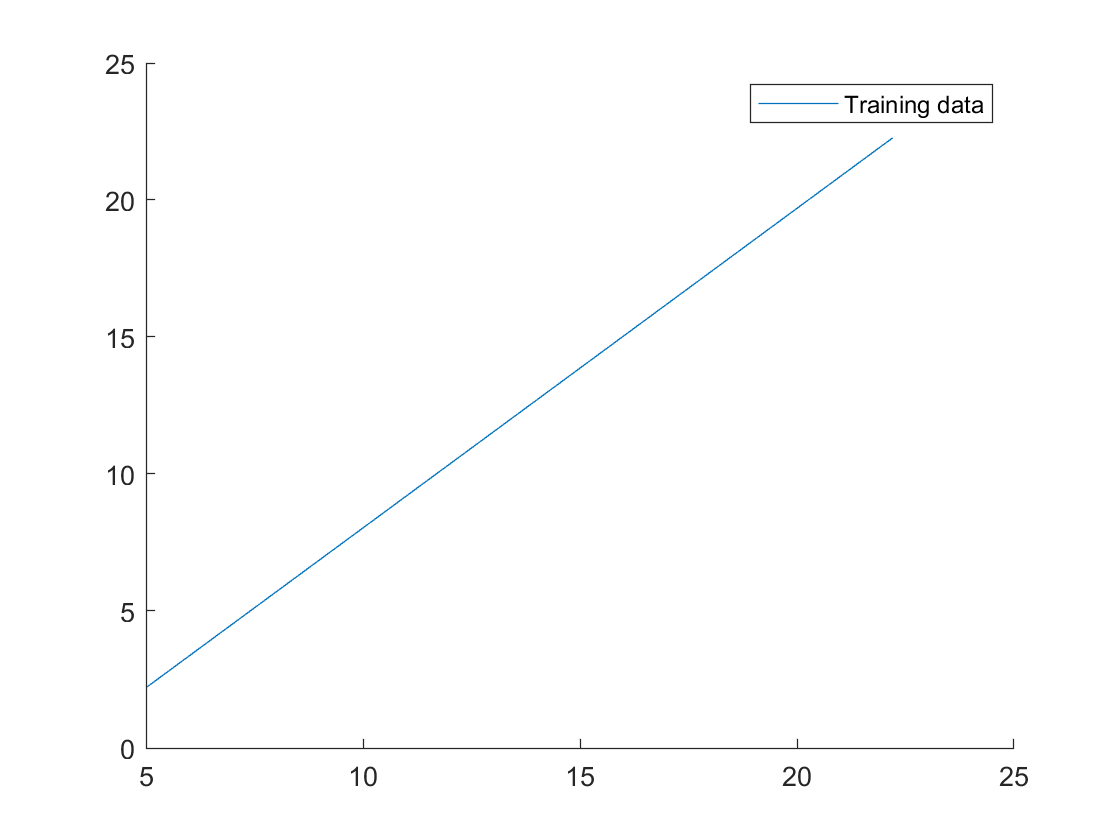

hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

sqrErrors = 97×1
    1.1358
    0.6080
    1.0356
    0.8327
    0.5145
    0.9162
    0.4763
    0.9350
    0.5329
    0.3561


sqrErrors = 97×1
    1.1151
    0.5943
    1.0081
    0.8124
    0.5012
    0.8908
    0.4600
    0.9087
    0.5179
    0.3466


sqrErrors = 97×1
    1.0946
    0.5808
    0.9810
    0.7924
    0.4880
    0.8657
    0.4439
    0.8828
    0.5031
    0.3371


sqrErrors = 97×1
    1.0743
    0.5674
    0.9542
    0.7726
    0.4750
    0.8409
    0.4282
    0.8572
    0.4885
    0.3278


sqrErrors = 97×1
    1.0542
    0.5542
    0.9278
    0.7531
    0.4622
    0.8166
    0.4127
    0.8320
    0.4741
    0.3186


sqrErrors = 97×1
    1.0342
    0.5411
    0.9018
    0.7338
    0.4496
    0.7925
    0.3975
    0.8072
    0.4600
    0.3096


sqrErrors = 97×1
    1.0145
    0.5282
    0.8761
    0.7148
    0.4371
    0.7689
    0.3826
    0.7828
    0.4460
    0.3007


sqrErrors = 97×1
  994.8955
  515.4563
  850.8290
  695.9741
  424.8320
  745.5766
  367.9310
  758.7512
  432.2989
  291.8706


sqrErrors = 97×1
  975.5236
  502.8576
  825.9153
  677.4372
  412.7197
  722.6349
  353.5879
  735.0714
  418.7840
  283.2131


sqrErrors = 97×1
  956.3421
  490.4147
  801.3717
  659.1505
  400.7826
  700.0517
  339.5299
  711.7671
  405.4838
  274.6860


sqrErrors = 97×1
  937.3511
  478.1277
  777.1983
  641.1141
  389.0206
  677.8271
  325.7570
  688.8381
  392.3981
  266.2893


sqrErrors = 97×1
  918.5506
  465.9967
  753.3951
  623.3278
  377.4338
  655.9609
  312.2693
  666.2846
  379.5271
  258.0228


sqrErrors = 97×1
  899.9405
  454.0214
  729.9622
  605.7917
  366.0222
  634.4532
  299.0668
  644.1064
  366.8707
  249.8867


sqrErrors = 97×1
  881.5209
  442.2021
  706.8994
  588.5058
  354.7857
  613.3040
  286.1494
  622.3036
  354.4290
  241.8810


sqrErrors = 97×1
  863.2918
  430.5386
  684.2068
  571.4702
  343.7244
  592.5133
  273.5172
  600.8762
  342.2018
  234.0056


sqrErrors = 97×1
  845.2531
  419.0311
  661.8845
  554.6847
  332.8383
  572.0812
  261.1702
  579.8242
  330.1893
  226.2605


sqrErrors = 97×1
  827.4048
  407.6794
  639.9323
  538.1495
  322.1274
  552.0075
  249.1083
  559.1476
  318.3914
  218.6458


sqrErrors = 97×1
  809.7470
  396.4836
  618.3503
  521.8644
  311.5916
  532.2923
  237.3315
  538.8464
  306.8082
  211.1614


sqrErrors = 97×1
  792.2797
  385.4436
  597.1385
  505.8295
  301.2311
  512.9356
  225.8400
  518.9205
  295.4395
  203.8073


sqrErrors = 97×1
  775.0028
  374.5596
  576.2970
  490.0449
  291.0456
  493.9374
  214.6335
  499.3701
  284.2855
  196.5836


sqrErrors = 97×1
  757.9164
  363.8314
  555.8256
  474.5104
  281.0354
  475.2977
  203.7123
  480.1950
  273.3461
  189.4902


sqrErrors = 97×1
  741.0205
  353.2591
  535.7244
  459.2262
  271.2003
  457.0166
  193.0762
  461.3953
  262.6214
  182.5271


sqrErrors = 97×1
  724.3150
  342.8427
  515.9934
  444.1922
  261.5404
  439.0939
  182.7252
  442.9711
  252.1112
  175.6944


sqrErrors = 97×1
  707.7999
  332.5821
  496.6327
  429.4083
  252.0557
  421.5297
  172.6594
  424.9222
  241.8157
  168.9921


sqrErrors = 97×1
  691.4753
  322.4775
  477.6421
  414.8747
  242.7461
  404.3240
  162.8788
  407.2487
  231.7348
  162.4200


sqrErrors = 97×1
  675.3412
  312.5287
  459.0217
  400.5912
  233.6117
  387.4768
  153.3833
  389.9506
  221.8686
  155.9784


sqrErrors = 97×1
  659.3975
  302.7358
  440.7715
  386.5580
  224.6525
  370.9881
  144.1730
  373.0278
  212.2169
  149.6670


sqrErrors = 97×1
  643.6443
  293.0988
  422.8916
  372.7750
  215.8685
  354.8579
  135.2478
  356.4805
  202.7799
  143.4860


sqrErrors = 97×1
  628.0815
  283.6176
  405.3818
  359.2422
  207.2596
  339.0862
  126.6078
  340.3085
  193.5575
  137.4353


sqrErrors = 97×1
  612.7092
  274.2923
  388.2422
  345.9595
  198.8259
  323.6730
  118.2529
  324.5120
  184.5498
  131.5150


sqrErrors = 97×1
  597.5274
  265.1230
  371.4728
  332.9271
  190.5674
  308.6183
  110.1833
  309.0908
  175.7566
  125.7250


sqrErrors = 97×1
  582.5360
  256.1095
  355.0736
  320.1449
  182.4840
  293.9221
  102.3987
  294.0450
  167.1781
  120.0653


sqrErrors = 97×1
  567.7350
  247.2518
  339.0447
  307.6129
  174.5759
  279.5844
   94.8993
  279.3746
  158.8142
  114.5360


sqrErrors = 97×1
  553.1245
  238.5501
  323.3859
  295.3311
  166.8429
  265.6052
   87.6851
  265.0796
  150.6650
  109.1370


sqrErrors = 97×1
  538.7045
  230.0042
  308.0973
  283.2995
  159.2850
  251.9845
   80.7561
  251.1600
  142.7304
  103.8684


sqrErrors = 97×1
  524.4750
  221.6142
  293.1789
  271.5181
  151.9024
  238.7224
   74.1122
  237.6158
  135.0103
   98.7301


sqrErrors = 97×1
  510.4358
  213.3801
  278.6308
  259.9869
  144.6949
  225.8187
   67.7534
  224.4470
  127.5050
   93.7221


sqrErrors = 97×1
  496.5872
  205.3019
  264.4528
  248.7059
  137.6626
  213.2735
   61.6798
  211.6535
  120.2142
   88.8445


sqrErrors = 97×1
  482.9290
  197.3795
  250.6450
  237.6751
  130.8054
  201.0868
   55.8914
  199.2355
  113.1381
   84.0972


sqrErrors = 97×1
  469.4613
  189.6131
  237.2074
  226.8945
  124.1234
  189.2586
   50.3881
  187.1928
  106.2765
   79.4803


sqrErrors = 97×1
  456.1840
  182.0025
  224.1400
  216.3641
  117.6166
  177.7888
   45.1700
  175.5255
   99.6297
   74.9936


sqrErrors = 97×1
  443.0971
  174.5478
  211.4429
  206.0839
  111.2850
  166.6776
   40.2370
  164.2336
   93.1974
   70.6374


sqrErrors = 97×1
  430.2008
  167.2489
  199.1159
  196.0540
  105.1285
  155.9249
   35.5892
  153.3172
   86.9798
   66.4114


sqrErrors = 97×1
  417.4949
  160.1060
  187.1591
  186.2742
   99.1473
  145.5307
   31.2266
  142.7760
   80.9767
   62.3158


sqrErrors = 97×1
  404.9794
  153.1189
  175.5725
  176.7446
   93.3411
  135.4950
   27.1491
  132.6103
   75.1884
   58.3506


sqrErrors = 97×1
  392.6544
  146.2877
  164.3561
  167.4652
   87.7102
  125.8178
   23.3567
  122.8200
   69.6146
   54.5157


sqrErrors = 97×1
  380.5199
  139.6124
  153.5099
  158.4361
   82.2544
  116.4991
   19.8496
  113.4051
   64.2555
   50.8111


sqrErrors = 97×1
  368.5758
  133.0930
  143.0340
  149.6571
   76.9738
  107.5389
   16.6276
  104.3655
   59.1110
   47.2369


sqrErrors = 97×1
  356.8221
  126.7294
  132.9282
  141.1284
   71.8684
   98.9372
   13.6907
   95.7013
   54.1811
   43.7930


sqrErrors = 97×1
  345.2590
  120.5217
  123.1926
  132.8498
   66.9382
   90.6940
   11.0390
   87.4126
   49.4658
   40.4794


sqrErrors = 97×1
  333.8862
  114.4699
  113.8272
  124.8214
   62.1831
   82.8093
    8.6724
   79.4992
   44.9652
   37.2962


sqrErrors = 97×1
  322.7040
  108.5740
  104.8320
  117.0433
   57.6032
   75.2831
    6.5911
   71.9612
   40.6792
   34.2433


sqrErrors = 97×1
  311.7122
  102.8340
   96.2070
  109.5153
   53.1984
   68.1154
    4.7948
   64.7986
   36.6078
   31.3207


sqrErrors = 97×1
  300.9108
   97.2498
   87.9523
  102.2376
   48.9689
   61.3061
    3.2838
   58.0114
   32.7510
   28.5285


sqrErrors = 97×1
  290.2999
   91.8215
   80.0677
   95.2100
   44.9145
   54.8554
    2.0578
   51.5995
   29.1089
   25.8667


sqrErrors = 97×1
  279.8795
   86.5491
   72.5533
   88.4327
   41.0353
   48.7632
    1.1171
   45.5631
   25.6814
   23.3351


sqrErrors = 97×1
  269.6495
   81.4326
   65.4091
   81.9056
   37.3312
   43.0295
    0.4615
   39.9021
   22.4685
   20.9339


sqrErrors = 97×1
  259.6100
   76.4720
   58.6351
   75.6286
   33.8023
   37.6543
    0.0910
   34.6164
   19.4702
   18.6631


sqrErrors = 97×1
  249.7610
   71.6672
   52.2313
   69.6019
   30.4486
   32.6376
    0.0058
   29.7061
   16.6866
   16.5226


sqrErrors = 97×1
  240.1023
   67.0183
   46.1978
   63.8254
   27.2701
   27.9794
    0.2056
   25.1712
   14.1176
   14.5124


sqrErrors = 97×1
  230.6342
   62.5253
   40.5344
   58.2991
   24.2668
   23.6796
    0.6907
   21.0118
   11.7632
   12.6326


sqrErrors = 97×1
  221.3565
   58.1882
   35.2412
   53.0229
   21.4386
   19.7384
    1.4608
   17.2276
    9.6234
   10.8831


sqrErrors = 97×1
  212.2693
   54.0069
   30.3182
   47.9970
   18.7856
   16.1557
    2.5162
   13.8189
    7.6983
    9.2639


sqrErrors = 97×1
  203.3725
   49.9816
   25.7654
   43.2213
   16.3077
   12.9315
    3.8567
   10.7856
    5.9878
    7.7751


sqrErrors = 97×1
  194.6662
   46.1121
   21.5828
   38.6958
   14.0051
   10.0658
    5.4823
    8.1277
    4.4919
    6.4166


sqrErrors = 97×1
  186.1503
   42.3985
   17.7704
   34.4205
   11.8776
    7.5585
    7.3932
    5.8451
    3.2106
    5.1884


sqrErrors = 97×1
  177.8249
   38.8407
   14.3282
   30.3954
    9.9252
    5.4098
    9.5891
    3.9380
    2.1440
    4.0906


sqrErrors = 97×1
  169.6899
   35.4389
   11.2563
   26.6205
    8.1481
    3.6196
   12.0703
    2.4062
    1.2920
    3.1232


sqrErrors = 97×1
  161.7454
   32.1929
    8.5545
   23.0958
    6.5461
    2.1879
   14.8366
    1.2498
    0.6546
    2.2860


sqrErrors = 97×1
  153.9914
   29.1028
    6.2229
   19.8213
    5.1193
    1.1146
   17.8880
    0.4688
    0.2318
    1.5793


sqrErrors = 97×1
  146.4278
   26.1686
    4.2615
   16.7970
    3.8677
    0.3999
   21.2246
    0.0632
    0.0237
    1.0028


sqrErrors = 97×1
  139.0547
   23.3903
    2.6703
   14.0229
    2.7912
    0.0437
   24.8464
    0.0330
    0.0302
    0.5567


sqrErrors = 97×1
  131.8720
   20.7678
    1.4493
   11.4990
    1.8899
    0.0460
   28.7533
    0.3782
    0.2513
    0.2409


sqrErrors = 97×1
  124.8798
   18.3012
    0.5985
    9.2253
    1.1638
    0.4067
   32.9454
    1.0988
    0.6870
    0.0555


sqrErrors = 97×1
  118.0781
   15.9906
    0.1179
    7.2018
    0.6128
    1.1260
   37.4226
    2.1947
    1.3374
    0.0004


sqrErrors = 97×1
  111.4668
   13.8357
    0.0075
    5.4286
    0.2371
    2.2038
   42.1850
    3.6661
    2.2024
    0.0756


sqrErrors = 97×1
  105.0459
   11.8368
    0.2673
    3.9055
    0.0365
    3.6400
   47.2325
    5.5128
    3.2820
    0.2812


sqrErrors = 97×1
   98.8155
    9.9937
    0.8974
    2.6326
    0.0110
    5.4348
   52.5652
    7.7349
    4.5762
    0.6171


sqrErrors = 97×1
   92.7756
    8.3066
    1.8976
    1.6099
    0.1608
    7.5881
   58.1831
   10.3325
    6.0851
    1.0834


sqrErrors = 97×1
   86.9261
    6.7753
    3.2680
    0.8375
    0.4857
   10.0998
   64.0861
   13.3054
    7.8086
    1.6800


sqrErrors = 97×1
   81.2671
    5.3999
    5.0086
    0.3152
    0.9858
   12.9701
   70.2743
   16.6537
    9.7467
    2.4069


sqrErrors = 97×1
   75.7986
    4.1803
    7.1194
    0.0432
    1.6610
   16.1989
   76.7476
   20.3773
   11.8994
    3.2642


sqrErrors = 97×1
   70.5204
    3.1167
    9.6004
    0.0213
    2.5115
   19.7861
   83.5061
   24.4764
   14.2668
    4.2518


sqrErrors = 97×1
   65.4328
    2.2089
   12.4516
    0.2496
    3.5371
   23.7319
   90.5498
   28.9509
   16.8488
    5.3698


sqrErrors = 97×1
   60.5356
    1.4570
   15.6730
    0.7282
    4.7378
   28.0362
   97.8786
   33.8007
   19.6454
    6.6181


sqrErrors = 97×1
   55.8289
    0.8610
   19.2646
    1.4570
    6.1138
   32.6989
  105.4925
   39.0260
   22.6566
    7.9967


sqrErrors = 97×1
   51.3126
    0.4208
   23.2264
    2.4359
    7.6649
   37.7202
  113.3917
   44.6266
   25.8825
    9.5056


sqrErrors = 97×1
   46.9868
    0.1365
   27.5584
    3.6651
    9.3912
   43.0999
  121.5760
   50.6026
   29.3230
   11.1450


sqrErrors = 97×1
   42.8514
    0.0082
   32.2606
    5.1444
   11.2927
   48.8382
  130.0454
   56.9540
   32.9781
   12.9146


sqrErrors = 97×1
   38.9065
    0.0357
   37.3330
    6.8740
   13.3693
   54.9350
  138.8000
   63.6808
   36.8478
   14.8146


sqrErrors = 97×1
   35.1521
    0.2190
   42.7756
    8.8538
   15.6211
   61.3902
  147.8397
   70.7830
   40.9322
   16.8449


sqrErrors = 97×1
   31.5881
    0.5583
   48.5884
   11.0837
   18.0481
   68.2040
  157.1646
   78.2606
   45.2312
   19.0056


sqrErrors = 97×1
   28.2145
    1.0534
   54.7715
   13.5639
   20.6502
   75.3762
  166.7747
   86.1135
   49.7448
   21.2966


sqrErrors = 97×1
   25.0315
    1.7044
   61.3247
   16.2943
   23.4276
   82.9070
  176.6699
   94.3419
   54.4730
   23.7179


sqrErrors = 97×1
   22.0388
    2.5113
   68.2481
   19.2749
   26.3801
   90.7962
  186.8503
  102.9456
   59.4159
   26.2696


sqrErrors = 97×1
   19.2367
    3.4741
   75.5417
   22.5057
   29.5077
   99.0440
  197.3159
  111.9248
   64.5734
   28.9516


sqrErrors = 97×1
   16.6250
    4.5927
   83.2055
   25.9866
   32.8106
  107.6502
  208.0665
  121.2793
   69.9455
   31.7639


sqrErrors = 97×1
   14.2037
    5.8673
   91.2395
   29.7178
   36.2886
  116.6150
  219.1024
  131.0092
   75.5322
   34.7066


sqrErrors = 97×1
   11.9729
    7.2977
   99.6437
   33.6992
   39.9418
  125.9382
  230.4234
  141.1145
   81.3336
   37.7797


sqrErrors = 97×1
    9.9326
    8.8840
  108.4181
   37.9308
   43.7701
  135.6200
  242.0296
  151.5952
   87.3496
   40.9830


sqrErrors = 97×1
    1.1223
    0.5981
    1.0226
    0.8211
    0.5054
    0.9040
    0.4675
    0.9227
    0.5236
    0.3485


sqrErrors = 97×1
    1.1017
    0.5845
    0.9953
    0.8010
    0.4922
    0.8787
    0.4514
    0.8966
    0.5087
    0.3391


sqrErrors = 97×1
    1.0813
    0.5711
    0.9683
    0.7811
    0.4791
    0.8538
    0.4355
    0.8708
    0.4941
    0.3297


sqrErrors = 97×1
    1.0611
    0.5578
    0.9417
    0.7614
    0.4663
    0.8293
    0.4198
    0.8454
    0.4796
    0.3205


sqrErrors = 97×1
    1.0411
    0.5447
    0.9155
    0.7420
    0.4536
    0.8050
    0.4045
    0.8204
    0.4654
    0.3115


sqrErrors = 97×1
    1.0213
    0.5318
    0.8897
    0.7229
    0.4411
    0.7812
    0.3895
    0.7958
    0.4513
    0.3025


sqrErrors = 97×1
    1.0016
    0.5190
    0.8642
    0.7040
    0.4287
    0.7577
    0.3747
    0.7715
    0.4375
    0.2937


sqrErrors = 97×1
  982.1921
  506.3239
  839.0844
  685.3558
  416.5450
  734.5850
  360.2217
  747.6625
  423.9390
  285.0087


sqrErrors = 97×1
  962.9448
  493.8380
  814.3445
  666.9618
  404.5522
  711.8144
  346.0311
  724.1578
  410.5565
  276.4544


sqrErrors = 97×1
  943.8881
  481.5079
  789.9747
  648.8180
  392.7347
  689.4023
  332.1257
  701.0285
  397.3886
  268.0304


sqrErrors = 97×1
  925.0218
  469.3338
  765.9752
  630.9245
  381.0923
  667.3486
  318.5054
  678.2746
  384.4353
  259.7368


sqrErrors = 97×1
  906.3459
  457.3155
  742.3458
  613.2811
  369.6251
  645.6535
  305.1703
  655.8961
  371.6966
  251.5735


sqrErrors = 97×1
  887.8605
  445.4530
  719.0867
  595.8879
  358.3330
  624.3169
  292.1203
  633.8930
  359.1726
  243.5406


sqrErrors = 97×1
  869.5656
  433.7465
  696.1978
  578.7450
  347.2161
  603.3388
  279.3555
  612.2652
  346.8632
  235.6379


sqrErrors = 97×1
  851.4611
  422.1959
  673.6790
  561.8522
  336.2744
  582.7192
  266.8759
  591.0129
  334.7684
  227.8657


sqrErrors = 97×1
  833.5471
  410.8011
  651.5305
  545.2097
  325.5079
  562.4580
  254.6814
  570.1359
  322.8883
  220.2237


sqrErrors = 97×1
  815.8236
  399.5622
  629.7521
  528.8173
  314.9165
  542.5554
  242.7721
  549.6343
  311.2227
  212.7121


sqrErrors = 97×1
  798.2905
  388.4792
  608.3440
  512.6752
  304.5003
  523.0113
  231.1479
  529.5082
  299.7718
  205.3309


sqrErrors = 97×1
  780.9478
  377.5520
  587.3060
  496.7832
  294.2593
  503.8257
  219.8089
  509.7574
  288.5356
  198.0800


sqrErrors = 97×1
  763.7956
  366.7808
  566.6383
  481.1415
  284.1935
  484.9986
  208.7550
  490.3820
  277.5139
  190.9594


sqrErrors = 97×1
  746.8339
  356.1654
  546.3408
  465.7499
  274.3028
  466.5299
  197.9863
  471.3820
  266.7069
  183.9692


sqrErrors = 97×1
  730.0626
  345.7059
  526.4134
  450.6086
  264.5873
  448.4198
  187.5028
  452.7573
  256.1145
  177.1093


sqrErrors = 97×1
  713.4818
  335.4023
  506.8563
  435.7175
  255.0470
  430.6682
  177.3044
  434.5081
  245.7367
  170.3797


sqrErrors = 97×1
  697.0914
  325.2545
  487.6693
  421.0765
  245.6818
  413.2751
  167.3911
  416.6342
  235.5735
  163.7805


sqrErrors = 97×1
  680.8915
  315.2627
  468.8526
  406.6858
  236.4919
  396.2404
  157.7631
  399.1358
  225.6250
  157.3116


sqrErrors = 97×1
  664.8821
  305.4267
  450.4060
  392.5453
  227.4771
  379.5643
  148.4201
  382.0127
  215.8911
  150.9730


sqrErrors = 97×1
  649.0631
  295.7466
  432.3297
  378.6550
  218.6374
  363.2467
  139.3624
  365.2650
  206.3718
  144.7648


sqrErrors = 97×1
  633.4345
  286.2223
  414.6235
  365.0148
  209.9730
  347.2875
  130.5898
  348.8927
  197.0672
  138.6870


sqrErrors = 97×1
  617.9964
  276.8540
  397.2876
  351.6249
  201.4837
  331.6869
  122.1023
  332.8958
  187.9771
  132.7394


sqrErrors = 97×1
  602.7488
  267.6415
  380.3219
  338.4852
  193.1695
  316.4448
  113.9001
  317.2743
  179.1017
  126.9223


sqrErrors = 97×1
  587.6917
  258.5849
  363.7263
  325.5957
  185.0306
  301.5612
  105.9829
  302.0282
  170.4410
  121.2354


sqrErrors = 97×1
  572.8249
  249.6842
  347.5010
  312.9564
  177.0668
  287.0360
   98.3510
  287.1575
  161.9948
  115.6789


sqrErrors = 97×1
  558.1487
  240.9394
  331.6458
  300.5673
  169.2782
  272.8694
   91.0041
  272.6621
  153.7633
  110.2527


sqrErrors = 97×1
  543.6629
  232.3505
  316.1609
  288.4284
  161.6648
  259.0613
   83.9425
  258.5422
  145.7464
  104.9569


sqrErrors = 97×1
  529.3676
  223.9174
  301.0461
  276.5397
  154.2265
  245.6116
   77.1660
  244.7976
  137.9441
   99.7914


sqrErrors = 97×1
  515.2627
  215.6402
  286.3016
  264.9012
  146.9634
  232.5205
   70.6746
  231.4284
  130.3564
   94.7562


sqrErrors = 97×1
  501.3482
  207.5189
  271.9272
  253.5129
  139.8755
  219.7878
   64.4685
  218.4346
  122.9834
   89.8514


sqrErrors = 97×1
  487.6243
  199.5535
  257.9231
  242.3748
  132.9628
  207.4137
   58.5474
  205.8162
  115.8250
   85.0769


sqrErrors = 97×1
  474.0908
  191.7439
  244.2891
  231.4869
  126.2252
  195.3981
   52.9116
  193.5732
  108.8812
   80.4328


sqrErrors = 97×1
  460.7477
  184.0902
  231.0254
  220.8493
  119.6628
  183.7409
   47.5608
  181.7056
  102.1521
   75.9190


sqrErrors = 97×1
  447.5951
  176.5924
  218.1318
  210.4618
  113.2756
  172.4423
   42.4953
  170.2134
   95.6376
   71.5355


sqrErrors = 97×1
  434.6330
  169.2505
  205.6085
  200.3245
  107.0635
  161.5021
   37.7149
  159.0965
   89.3376
   67.2824


sqrErrors = 97×1
  421.8613
  162.0645
  193.4553
  190.4374
  101.0266
  150.9205
   33.2197
  148.3551
   83.2524
   63.1596


sqrErrors = 97×1
  409.2800
  155.0343
  181.6724
  180.8006
   95.1649
  140.6974
   29.0096
  137.9890
   77.3817
   59.1671


sqrErrors = 97×1
  396.8893
  148.1601
  170.2596
  171.4139
   89.4784
  130.8327
   25.0846
  127.9983
   71.7257
   55.3050


sqrErrors = 97×1
  384.6889
  141.4417
  159.2171
  162.2774
   83.9670
  121.3266
   21.4449
  118.3831
   66.2843
   51.5733


sqrErrors = 97×1
  372.6791
  134.8792
  148.5447
  153.3912
   78.6308
  112.1789
   18.0903
  109.1432
   61.0575
   47.9718


sqrErrors = 97×1
  360.8597
  128.4725
  138.2426
  144.7551
   73.4698
  103.3898
   15.0208
  100.2787
   56.0454
   44.5007


sqrErrors = 97×1
  349.2307
  122.2218
  128.3106
  136.3693
   68.4840
   94.9591
   12.2365
   91.7895
   51.2478
   41.1600


sqrErrors = 97×1
  337.7922
  116.1269
  118.7489
  128.2336
   63.6733
   86.8870
    9.7374
   83.6758
   46.6649
   37.9496


sqrErrors = 97×1
  326.5442
  110.1879
  109.5573
  120.3482
   59.0378
   79.1733
    7.5234
   75.9375
   42.2966
   34.8695


sqrErrors = 97×1
  315.4866
  104.4048
  100.7360
  112.7129
   54.5775
   71.8182
    5.5946
   68.5745
   38.1430
   31.9197


sqrErrors = 97×1
  304.6195
   98.7775
   92.2848
  105.3279
   50.2923
   64.8215
    3.9509
   61.5870
   34.2040
   29.1003


sqrErrors = 97×1
  293.9429
   93.3062
   84.2039
   98.1930
   46.1823
   58.1834
    2.5924
   54.9748
   30.4796
   26.4113


sqrErrors = 97×1
  283.4566
   87.9907
   76.4931
   91.3084
   42.2475
   51.9037
    1.5191
   48.7380
   26.9698
   23.8525


sqrErrors = 97×1
  273.1609
   82.8311
   69.1526
   84.6740
   38.4878
   45.9826
    0.7309
   42.8766
   23.6746
   21.4242


sqrErrors = 97×1
  263.0556
   77.8273
   62.1822
   78.2897
   34.9034
   40.4199
    0.2278
   37.3906
   20.5941
   19.1261


sqrErrors = 97×1
  253.1408
   72.9795
   55.5821
   72.1557
   31.4941
   35.2158
    0.0099
   32.2800
   17.7282
   16.9584


sqrErrors = 97×1
  243.4164
   68.2875
   49.3521
   66.2719
   28.2600
   30.3701
    0.0772
   27.5448
   15.0769
   14.9210


sqrErrors = 97×1
  233.8825
   63.7514
   43.4923
   60.6383
   25.2010
   25.8830
    0.4297
   23.1849
   12.6403
   13.0140


sqrErrors = 97×1
  224.5390
   59.3712
   38.0028
   55.2549
   22.3172
   21.7543
    1.0672
   19.2005
   10.4182
   11.2373


sqrErrors = 97×1
  215.3860
   55.1469
   32.8834
   50.1217
   19.6086
   17.9842
    1.9900
   15.5914
    8.4108
    9.5910


sqrErrors = 97×1
  206.4234
   51.0785
   28.1343
   45.2386
   17.0752
   14.5725
    3.1979
   12.3578
    6.6180
    8.0749


sqrErrors = 97×1
  197.6513
   47.1659
   23.7553
   40.6058
   14.7169
   11.5193
    4.6910
    9.4995
    5.0399
    6.6893


sqrErrors = 97×1
  189.0697
   43.4092
   19.7466
   36.2232
   12.5338
    8.8247
    6.4692
    7.0166
    3.6764
    5.4339


sqrErrors = 97×1
  180.6785
   39.8084
   16.1080
   32.0908
   10.5259
    6.4885
    8.5326
    4.9091
    2.5275
    4.3089


sqrErrors = 97×1
  172.4778
   36.3635
   12.8397
   28.2086
    8.6931
    4.5109
   10.8811
    3.1770
    1.5932
    3.3143


sqrErrors = 97×1
  164.4675
   33.0744
    9.9415
   24.5766
    7.0356
    2.8917
   13.5148
    1.8203
    0.8735
    2.4499


sqrErrors = 97×1
  156.6477
   29.9412
    7.4135
   21.1948
    5.5532
    1.6310
   16.4337
    0.8389
    0.3685
    1.7160


sqrErrors = 97×1
  149.0183
   26.9640
    5.2558
   18.0633
    4.2459
    0.7289
   19.6377
    0.2330
    0.0781
    1.1123


sqrErrors = 97×1
  141.5794
   24.1425
    3.4682
   15.1819
    3.1139
    0.1852
   23.1268
    0.0024
    0.0023
    0.6390


sqrErrors = 97×1
  134.3310
   21.4770
    2.0509
   12.5507
    2.1570
    0.0000
   26.9012
    0.1473
    0.1412
    0.2960


sqrErrors = 97×1
  127.2730
   18.9674
    1.0037
   10.1697
    1.3753
    0.1734
   30.9606
    0.6675
    0.4946
    0.0834


sqrErrors = 97×1
  120.4055
   16.6136
    0.3267
    8.0389
    0.7687
    0.7052
   35.3053
    1.5631
    1.0627
    0.0011


sqrErrors = 97×1
  113.7284
   14.4157
    0.0200
    6.1584
    0.3373
    1.5955
   39.9351
    2.8341
    1.8455
    0.0492


sqrErrors = 97×1
  107.2418
   12.3737
    0.0834
    4.5280
    0.0811
    2.8444
   44.8500
    4.4805
    2.8428
    0.2276


sqrErrors = 97×1
  100.9456
   10.4875
    0.5171
    3.1478
    0.0001
    4.4517
   50.0502
    6.5023
    4.0548
    0.5363


sqrErrors = 97×1
   94.8399
    8.7573
    1.3209
    2.0179
    0.0943
    6.4175
   55.5354
    8.8995
    5.4814
    0.9753


sqrErrors = 97×1
   88.9247
    7.1829
    2.4950
    1.1381
    0.3636
    8.7419
   61.3058
   11.6720
    7.1226
    1.5448


sqrErrors = 97×1
   83.1999
    5.7644
    4.0392
    0.5085
    0.8081
   11.4247
   67.3614
   14.8200
    8.9784
    2.2445


sqrErrors = 97×1
   77.6656
    4.5018
    5.9536
    0.1292
    1.4277
   14.4660
   73.7022
   18.3433
   11.0489
    3.0746


sqrErrors = 97×1
   72.3217
    3.3950
    8.2383
    0.0000
    2.2226
   17.8659
   80.3281
   22.2420
   13.3340
    4.0350


sqrErrors = 97×1
   67.1683
    2.4442
   10.8931
    0.1211
    3.1926
   21.6242
   87.2391
   26.5162
   15.8337
    5.1258


sqrErrors = 97×1
   62.2053
    1.6492
   13.9181
    0.4923
    4.3378
   25.7410
   94.4353
   31.1657
   18.5481
    6.3468


sqrErrors = 97×1
   57.4328
    1.0101
   17.3134
    1.1138
    5.6581
   30.2163
  101.9167
   36.1906
   21.4770
    7.6983


sqrErrors = 97×1
   52.8508
    0.5269
   21.0788
    1.9855
    7.1536
   35.0502
  109.6832
   41.5909
   24.6206
    9.1801


sqrErrors = 97×1
   48.4592
    0.1995
   25.2145
    3.1073
    8.8243
   40.2425
  117.7349
   47.3665
   27.9789
   10.7922


sqrErrors = 97×1
   44.2580
    0.0281
   29.7203
    4.4794
   10.6702
   45.7933
  126.0718
   53.5176
   31.5517
   12.5346


sqrErrors = 97×1
   40.2473
    0.0125
   34.5963
    6.1017
   12.6912
   51.7026
  134.6938
   60.0440
   35.3392
   14.4074


sqrErrors = 97×1
   36.4271
    0.1528
   39.8426
    7.9741
   14.8874
   57.9704
  143.6009
   66.9459
   39.3413
   16.4105


sqrErrors = 97×1
   32.7974
    0.4489
   45.4590
   10.0968
   17.2588
   64.5968
  152.7932
   74.2231
   43.5580
   18.5440


sqrErrors = 97×1
   29.3581
    0.9010
   51.4456
   12.4697
   19.8054
   71.5816
  162.2707
   81.8757
   47.9893
   20.8078


sqrErrors = 97×1
   26.1092
    1.5089
   57.8025
   15.0928
   22.5271
   78.9249
  172.0334
   89.9037
   52.6353
   23.2020


sqrErrors = 97×1
   23.0508
    2.2727
   64.5295
   17.9661
   25.4240
   86.6267
  182.0811
   98.3071
   57.4959
   25.7264


sqrErrors = 97×1
   20.1829
    3.1924
   71.6267
   21.0895
   28.4961
   94.6870
  192.4141
  107.0859
   62.5711
   28.3813


sqrErrors = 97×1
   17.5054
    4.2680
   79.0942
   24.4632
   31.7433
  103.1058
  203.0322
  116.2401
   67.8610
   31.1664


sqrErrors = 97×1
   15.0184
    5.4994
   86.9318
   28.0871
   35.1658
  111.8832
  213.9354
  125.7697
   73.3654
   34.0819


sqrErrors = 97×1
   12.7218
    6.8868
   95.1396
   31.9612
   38.7633
  121.0190
  225.1239
  135.6746
   79.0845
   37.1278


sqrErrors = 97×1
   10.6157
    8.4300
  103.7177
   36.0855
   42.5361
  130.5133
  236.5974
  145.9550
   85.0183
   40.3039


sqrErrors = 97×1
    8.7000
   10.1291
  112.6659
   40.4600
   46.4840
  140.3661
  248.3562
  156.6107
   91.1666
   43.6104


sqrErrors = 97×1
    1.1088
    0.5882
    1.0097
    0.8096
    0.4964
    0.8919
    0.4588
    0.9105
    0.5144
    0.3410


sqrErrors = 97×1
    1.0883
    0.5748
    0.9826
    0.7896
    0.4833
    0.8668
    0.4428
    0.8845
    0.4997
    0.3317


sqrErrors = 97×1
    1.0680
    0.5615
    0.9558
    0.7698
    0.4703
    0.8421
    0.4271
    0.8589
    0.4851
    0.3224


sqrErrors = 97×1
    1.0480
    0.5483
    0.9294
    0.7503
    0.4576
    0.8177
    0.4116
    0.8337
    0.4708
    0.3133


sqrErrors = 97×1
    1.0281
    0.5353
    0.9033
    0.7311
    0.4450
    0.7936
    0.3964
    0.8089
    0.4567
    0.3044


sqrErrors = 97×1
    1.0084
    0.5225
    0.8777
    0.7121
    0.4326
    0.7699
    0.3815
    0.7844
    0.4428
    0.2955


sqrErrors = 97×1
  988.8833
  509.8022
  852.3577
  693.3204
  420.3879
  746.6330
  366.9172
  760.3605
  429.1255
  286.8099


sqrErrors = 97×1
  969.5703
  497.2732
  827.4214
  674.8191
  408.3395
  723.6750
  352.5941
  736.6555
  415.6607
  278.2284


sqrErrors = 97×1
  950.4477
  484.9000
  802.8553
  656.5680
  396.4664
  701.0754
  338.5560
  713.3258
  402.4105
  269.7772


sqrErrors = 97×1
  931.5157
  472.6828
  778.6594
  638.5672
  384.7684
  678.8344
  324.8032
  690.3716
  389.3750
  261.4564


sqrErrors = 97×1
  912.7740
  460.6214
  754.8337
  620.8165
  373.2456
  656.9518
  311.3354
  667.7927
  376.5541
  253.2659


sqrErrors = 97×1
  894.2229
  448.7159
  731.3782
  603.3161
  361.8979
  635.4278
  298.1529
  645.5893
  363.9478
  245.2058


sqrErrors = 97×1
  875.8622
  436.9663
  708.2928
  586.0658
  350.7255
  614.2622
  285.2555
  623.7612
  351.5561
  237.2760


sqrErrors = 97×1
  857.6919
  425.3725
  685.5777
  569.0657
  339.7282
  593.4552
  272.6432
  602.3085
  339.3791
  229.4765


sqrErrors = 97×1
  839.7121
  413.9347
  663.2328
  552.3159
  328.9060
  573.0066
  260.3162
  581.2312
  327.4166
  221.8074


sqrErrors = 97×1
  821.9228
  402.6527
  641.2581
  535.8162
  318.2591
  552.9166
  248.2742
  560.5293
  315.6688
  214.2686


sqrErrors = 97×1
  804.3239
  391.5266
  619.6536
  519.5668
  307.7873
  533.1850
  236.5175
  540.2027
  304.1357
  206.8602


sqrErrors = 97×1
  786.9155
  380.5564
  598.4193
  503.5676
  297.4907
  513.8119
  225.0459
  520.2516
  292.8171
  199.5821


sqrErrors = 97×1
  769.6975
  369.7420
  577.5552
  487.8185
  287.3692
  494.7974
  213.8594
  500.6758
  281.7132
  192.4343


sqrErrors = 97×1
  752.6700
  359.0836
  557.0613
  472.3197
  277.4230
  476.1413
  202.9581
  481.4755
  270.8239
  185.4169


sqrErrors = 97×1
  735.8330
  348.5810
  536.9376
  457.0711
  267.6519
  457.8438
  192.3420
  462.6505
  260.1492
  178.5298


sqrErrors = 97×1
  719.1864
  338.2343
  517.1840
  442.0726
  258.0560
  439.9047
  182.0110
  444.2009
  249.6892
  171.7730


sqrErrors = 97×1
  702.7302
  328.0435
  497.8007
  427.3244
  248.6352
  422.3241
  171.9652
  426.1267
  239.4438
  165.1466


sqrErrors = 97×1
  686.4646
  318.0085
  478.7876
  412.8264
  239.3896
  405.1021
  162.2045
  408.4279
  229.4130
  158.6505


sqrErrors = 97×1
  670.3893
  308.1295
  460.1447
  398.5786
  230.3192
  388.2385
  152.7290
  391.1045
  219.5968
  152.2848


sqrErrors = 97×1
  654.5046
  298.4063
  441.8720
  384.5809
  221.4240
  371.7334
  143.5386
  374.1565
  209.9953
  146.0494


sqrErrors = 97×1
  638.8103
  288.8390
  423.9695
  370.8335
  212.7039
  355.5869
  134.6334
  357.5839
  200.6083
  139.9443


sqrErrors = 97×1
  623.3064
  279.4276
  406.4372
  357.3363
  204.1590
  339.7988
  126.0134
  341.3866
  191.4360
  133.9696


sqrErrors = 97×1
  607.9930
  270.1720
  389.2751
  344.0893
  195.7893
  324.3692
  117.6785
  325.5648
  182.4784
  128.1252


sqrErrors = 97×1
  592.8701
  261.0723
  372.4831
  331.0925
  187.5948
  309.2982
  109.6288
  310.1183
  173.7353
  122.4112


sqrErrors = 97×1
  577.9376
  252.1286
  356.0614
  318.3459
  179.5754
  294.5856
  101.8642
  295.0472
  165.2069
  116.8274


sqrErrors = 97×1
  563.1956
  243.3407
  340.0099
  305.8495
  171.7312
  280.2315
   94.3848
  280.3515
  156.8931
  111.3741


sqrErrors = 97×1
  548.6440
  234.7086
  324.3286
  293.6033
  164.0622
  266.2360
   87.1906
  266.0312
  148.7939
  106.0511


sqrErrors = 97×1
  534.2829
  226.2325
  309.0175
  281.6073
  156.5683
  252.5989
   80.2815
  252.0863
  140.9094
  100.8584


sqrErrors = 97×1
  520.1122
  217.9122
  294.0766
  269.8615
  149.2496
  239.3203
   73.6575
  238.5168
  133.2395
   95.7960


sqrErrors = 97×1
  506.1320
  209.7478
  279.5058
  258.3659
  142.1061
  226.4002
   67.3188
  225.3227
  125.7842
   90.8640


sqrErrors = 97×1
  492.3423
  201.7393
  265.3053
  247.1206
  135.1378
  213.8387
   61.2651
  212.5039
  118.5435
   86.0623


sqrErrors = 97×1
  478.7430
  193.8867
  251.4750
  236.1254
  128.3446
  201.6356
   55.4967
  200.0606
  111.5175
   81.3910


sqrErrors = 97×1
  465.3341
  186.1899
  238.0149
  225.3804
  121.7266
  189.7910
   50.0134
  187.9926
  104.7060
   76.8500


sqrErrors = 97×1
  452.1158
  178.6490
  224.9250
  214.8856
  115.2838
  178.3049
   44.8152
  176.3000
   98.1092
   72.4393


sqrErrors = 97×1
  439.0879
  171.2640
  212.2053
  204.6411
  109.0161
  167.1774
   39.9022
  164.9828
   91.7271
   68.1590


sqrErrors = 97×1
  426.2504
  164.0349
  199.8557
  194.6467
  102.9237
  156.4083
   35.2744
  154.0410
   85.5595
   64.0090


sqrErrors = 97×1
  413.6034
  156.9617
  187.8764
  184.9025
   97.0064
  145.9977
   30.9317
  143.4746
   79.6066
   59.9894


sqrErrors = 97×1
  401.1468
  150.0443
  176.2673
  175.4086
   91.2642
  135.9456
   26.8742
  133.2836
   73.8683
   56.1001


sqrErrors = 97×1
  388.8808
  143.2829
  165.0284
  166.1648
   85.6973
  126.2520
   23.1018
  123.4680
   68.3446
   52.3411


sqrErrors = 97×1
  376.8051
  136.6773
  154.1597
  157.1713
   80.3055
  116.9169
   19.6146
  114.0278
   63.0356
   48.7125


sqrErrors = 97×1
  364.9199
  130.2275
  143.6611
  148.4279
   75.0889
  107.9404
   16.4126
  104.9629
   57.9412
   45.2142


sqrErrors = 97×1
  353.2252
  123.9337
  133.5328
  139.9348
   70.0474
   99.3223
   13.4957
   96.2734
   53.0614
   41.8462


sqrErrors = 97×1
  341.7210
  117.7957
  123.7747
  131.6918
   65.1811
   91.0627
   10.8640
   87.9594
   48.3962
   38.6086


sqrErrors = 97×1
  330.4071
  111.8137
  114.3868
  123.6991
   60.4900
   83.1616
    8.5174
   80.0207
   43.9457
   35.5014


sqrErrors = 97×1
  319.2838
  105.9875
  105.3691
  115.9565
   55.9741
   75.6190
    6.4560
   72.4574
   39.7097
   32.5244


sqrErrors = 97×1
  308.3509
  100.3171
   96.7215
  108.4642
   51.6334
   68.4349
    4.6797
   65.2695
   35.6884
   29.6778


sqrErrors = 97×1
  297.6085
   94.8027
   88.4442
  101.2221
   47.4678
   61.6094
    3.1886
   58.4570
   31.8818
   26.9616


sqrErrors = 97×1
  287.0565
   89.4441
   80.5371
   94.2301
   43.4774
   55.1423
    1.9827
   52.0199
   28.2897
   24.3756


sqrErrors = 97×1
  276.6950
   84.2415
   73.0002
   87.4884
   39.6621
   49.0337
    1.0619
   45.9581
   24.9123
   21.9201


sqrErrors = 97×1
  266.5239
   79.1946
   65.8335
   80.9969
   36.0221
   43.2836
    0.4263
   40.2718
   21.7495
   19.5948


sqrErrors = 97×1
  256.5433
   74.3037
   59.0369
   74.7556
   32.5572
   37.8920
    0.0758
   34.9608
   18.8013
   17.3999


sqrErrors = 97×1
  246.7531
   69.5687
   52.6106
   68.7644
   29.2674
   32.8589
    0.0105
   30.0252
   16.0678
   15.3354


sqrErrors = 97×1
  237.1534
   64.9895
   46.5545
   63.0235
   26.1529
   28.1843
    0.2303
   25.4651
   13.5489
   13.4011


sqrErrors = 97×1
  227.7442
   60.5662
   40.8686
   57.5328
   23.2135
   23.8682
    0.7353
   21.2803
   11.2446
   11.5972


sqrErrors = 97×1
  218.5254
   56.2988
   35.5528
   52.2923
   20.4493
   19.9106
    1.5255
   17.4709
    9.1549
    9.9237


sqrErrors = 97×1
  209.4971
   52.1873
   30.6073
   47.3020
   17.8603
   16.3115
    2.6008
   14.0369
    7.2799
    8.3805


sqrErrors = 97×1
  200.6592
   48.2316
   26.0320
   42.5619
   15.4464
   13.0709
    3.9613
   10.9782
    5.6194
    6.9676


sqrErrors = 97×1
  192.0118
   44.4319
   21.8269
   38.0720
   13.2077
   10.1888
    5.6069
    8.2950
    4.1736
    5.6851


sqrErrors = 97×1
  183.5548
   40.7880
   17.9919
   33.8323
   11.1442
    7.6652
    7.5377
    5.9872
    2.9425
    4.5329


sqrErrors = 97×1
  175.2883
   37.3000
   14.5272
   29.8428
    9.2558
    5.5001
    9.7536
    4.0547
    1.9259
    3.5110


sqrErrors = 97×1
  167.2123
   33.9678
   11.4327
   26.1035
    7.5427
    3.6935
   12.2547
    2.4976
    1.1240
    2.6195


sqrErrors = 97×1
  159.3267
   30.7916
    8.7084
   22.6144
    6.0047
    2.2454
   15.0410
    1.3160
    0.5367
    1.8583


sqrErrors = 97×1
  151.6316
   27.7712
    6.3542
   19.3755
    4.6418
    1.1558
   18.1124
    0.5097
    0.1640
    1.2275


sqrErrors = 97×1
  144.1269
   24.9067
    4.3703
   16.3869
    3.4542
    0.4247
   21.4690
    0.0788
    0.0060
    0.7270


sqrErrors = 97×1
  136.8127
   22.1981
    2.7566
   13.6484
    2.4417
    0.0521
   25.1107
    0.0233
    0.0626
    0.3568


sqrErrors = 97×1
  129.6889
   19.6454
    1.5131
   11.1601
    1.6044
    0.0380
   29.0376
    0.3432
    0.3338
    0.1170


sqrErrors = 97×1
  122.7556
   17.2485
    0.6397
    8.9220
    0.9423
    0.3824
   33.2496
    1.0384
    0.8196
    0.0075


sqrErrors = 97×1
  116.0128
   15.0075
    0.1366
    6.9342
    0.4553
    1.0853
   37.7468
    2.1091
    1.5201
    0.0284


sqrErrors = 97×1
  109.4604
   12.9224
    0.0037
    5.1965
    0.1435
    2.1467
   42.5292
    3.5551
    2.4351
    0.1796


sqrErrors = 97×1
  103.0985
   10.9932
    0.2409
    3.7090
    0.0069
    3.5666
   47.5967
    5.3766
    3.5648
    0.4611


sqrErrors = 97×1
   96.9270
    9.2199
    0.8484
    2.4718
    0.0454
    5.3450
   52.9494
    7.5734
    4.9092
    0.8730


sqrErrors = 97×1
   90.9460
    7.6024
    1.8261
    1.4847
    0.2591
    7.4819
   58.5872
   10.1456
    6.4681
    1.4152


sqrErrors = 97×1
   85.1554
    6.1408
    3.1740
    0.7479
    0.6480
    9.9773
   64.5102
   13.0932
    8.2417
    2.0877


sqrErrors = 97×1
   79.5553
    4.8351
    4.8920
    0.2612
    1.2121
   12.8312
   70.7184
   16.4162
   10.2299
    2.8906


sqrErrors = 97×1
   74.1457
    3.6853
    6.9803
    0.0248
    1.9513
   16.0436
   77.2117
   20.1146
   12.4327
    3.8238


sqrErrors = 97×1
   68.9265
    2.6914
    9.4388
    0.0385
    2.8657
   19.6145
   83.9901
   24.1884
   14.8502
    4.8874


sqrErrors = 97×1
   63.8977
    1.8533
   12.2674
    0.3025
    3.9553
   23.5439
   91.0538
   28.6375
   17.4823
    6.0813


sqrErrors = 97×1
   59.0594
    1.1711
   15.4663
    0.8167
    5.2201
   27.8317
   98.4025
   33.4621
   20.3290
    7.4056


sqrErrors = 97×1
   54.4116
    0.6448
   19.0354
    1.5810
    6.6600
   32.4781
  106.0365
   38.6620
   23.3903
    8.8601


sqrErrors = 97×1
   49.9543
    0.2744
   22.9747
    2.5956
    8.2751
   37.4830
  113.9556
   44.2374
   26.6663
   10.4451


sqrErrors = 97×1
   45.6873
    0.0599
   27.2841
    3.8604
   10.0654
   42.8464
  122.1598
   50.1881
   30.1568
   12.1603


sqrErrors = 97×1
   41.6109
    0.0012
   31.9638
    5.3753
   12.0308
   48.5683
  130.6492
   56.5142
   33.8620
   14.0059


sqrErrors = 97×1
   37.7249
    0.0984
   37.0137
    7.1405
   14.1714
   54.6487
  139.4238
   63.2157
   37.7819
   15.9818


sqrErrors = 97×1
   34.0294
    0.3515
   42.4337
    9.1559
   16.4872
   61.0876
  148.4835
   70.2926
   41.9163
   18.0881


sqrErrors = 97×1
   30.5243
    0.7605
   48.2240
   11.4215
   18.9782
   67.8849
  157.8284
   77.7449
   46.2654
   20.3247


sqrErrors = 97×1
   27.2096
    1.3253
   54.3845
   13.9373
   21.6443
   75.0408
  167.4584
   85.5725
   50.8291
   22.6917


sqrErrors = 97×1
   24.0855
    2.0461
   60.9151
   16.7033
   24.4856
   82.5552
  177.3736
   93.7756
   55.6074
   25.1890


sqrErrors = 97×1
   21.1518
    2.9227
   67.8160
   19.7194
   27.5021
   90.4281
  187.5740
  102.3540
   60.6004
   27.8166


sqrErrors = 97×1
   18.4085
    3.9552
   75.0871
   22.9858
   30.6937
   98.6595
  198.0595
  111.3078
   65.8080
   30.5746


sqrErrors = 97×1
   15.8557
    5.1435
   82.7283
   26.5024
   34.0606
  107.2493
  208.8301
  120.6371
   71.2302
   33.4629


sqrErrors = 97×1
   13.4934
    6.4878
   90.7398
   30.2692
   37.6026
  116.1977
  219.8860
  130.3417
   76.8670
   36.4815


sqrErrors = 97×1
   11.3215
    7.9879
   99.1215
   34.2863
   41.3197
  125.5046
  231.2270
  140.4217
   82.7185
   39.6305


sqrErrors = 97×1
    9.3401
    9.6439
  107.8733
   38.5535
   45.2121
  135.1700
  242.8531
  150.8771
   88.7845
   42.9098


sqrErrors = 97×1
    7.5491
   11.4558
  116.9954
   43.0709
   49.2796
  145.1938
  254.7644
  161.7079
   95.0652
   46.3195


sqrErrors = 97×1
    1.0953
    0.5785
    0.9970
    0.7981
    0.4874
    0.8799
    0.4502
    0.8983
    0.5053
    0.3336


sqrErrors = 97×1
    1.0750
    0.5651
    0.9700
    0.7783
    0.4744
    0.8549
    0.4343
    0.8725
    0.4907
    0.3244


sqrErrors = 97×1
    1.0549
    0.5519
    0.9434
    0.7587
    0.4616
    0.8304
    0.4188
    0.8471
    0.4763
    0.3152


sqrErrors = 97×1
    1.0349
    0.5389
    0.9171
    0.7393
    0.4490
    0.8061
    0.4034
    0.8221
    0.4621
    0.3062


sqrErrors = 97×1
    1.0152
    0.5260
    0.8912
    0.7202
    0.4365
    0.7823
    0.3884
    0.7974
    0.4481
    0.2974


sqrErrors = 97×1
  995.5972
  513.2923
  865.7352
  701.3310
  424.2484
  758.7791
  373.6744
  773.1654
  434.3435
  288.6168


sqrErrors = 97×1
  976.2184
  500.7202
  840.6025
  682.7224
  412.1445
  735.6336
  359.2186
  749.2601
  420.7965
  280.0081


sqrErrors = 97×1
  957.0301
  488.3040
  815.8400
  664.3641
  400.2157
  712.8466
  345.0480
  725.7301
  407.4640
  271.5297


sqrErrors = 97×1
  938.0322
  476.0437
  791.4477
  646.2559
  388.4622
  690.4181
  331.1625
  702.5755
  394.3462
  263.1817


sqrErrors = 97×1
  919.2249
  463.9392
  767.4257
  628.3979
  376.8837
  668.3482
  317.5622
  679.7963
  381.4430
  254.9641


sqrErrors = 97×1
  900.6079
  451.9906
  743.7738
  610.7902
  365.4805
  646.6367
  304.2471
  657.3925
  368.7545
  246.8767


sqrErrors = 97×1
  882.1814
  440.1980
  720.4921
  593.4326
  354.2524
  625.2837
  291.2171
  635.3640
  356.2805
  238.9197


sqrErrors = 97×1
  863.9454
  428.5611
  697.5806
  576.3253
  343.1995
  604.2892
  278.4723
  613.7110
  344.0212
  231.0931


sqrErrors = 97×1
  845.8999
  417.0802
  675.0393
  559.4681
  332.3218
  583.6532
  266.0126
  592.4333
  331.9765
  223.3967


sqrErrors = 97×1
  828.0447
  405.7551
  652.8683
  542.8612
  321.6193
  563.3757
  253.8381
  571.5311
  320.1465
  215.8308


sqrErrors = 97×1
  810.3801
  394.5860
  631.0674
  526.5045
  311.0919
  543.4567
  241.9487
  551.0042
  308.5310
  208.3951


sqrErrors = 97×1
  792.9059
  383.5727
  609.6367
  510.3979
  300.7397
  523.8962
  230.3445
  530.8527
  297.1302
  201.0898


sqrErrors = 97×1
  775.6222
  372.7152
  588.5762
  494.5416
  290.5626
  504.6942
  219.0254
  511.0766
  285.9440
  193.9149


sqrErrors = 97×1
  758.5289
  362.0137
  567.8859
  478.9355
  280.5608
  485.8507
  207.9915
  491.6759
  274.9725
  186.8702


sqrErrors = 97×1
  741.6261
  351.4680
  547.5659
  463.5795
  270.7341
  467.3657
  197.2428
  472.6506
  264.2155
  179.9559


sqrErrors = 97×1
  724.9137
  341.0783
  527.6160
  448.4738
  261.0826
  449.2392
  186.7792
  454.0007
  253.6732
  173.1720


sqrErrors = 97×1
  708.3918
  330.8444
  508.0363
  433.6183
  251.6062
  431.4712
  176.6008
  435.7262
  243.3455
  166.5184


sqrErrors = 97×1
  692.0603
  320.7663
  488.8268
  419.0130
  242.3050
  414.0617
  166.7076
  417.8270
  233.2325
  159.9951


sqrErrors = 97×1
  675.9193
  310.8442
  469.9875
  404.6578
  233.1790
  397.0107
  157.0995
  400.3032
  223.3340
  153.6022


sqrErrors = 97×1
  659.9688
  301.0779
  451.5185
  390.5529
  224.2282
  380.3182
  147.7765
  383.1549
  213.6502
  147.3396


sqrErrors = 97×1
  644.2087
  291.4675
  433.4196
  376.6982
  215.4526
  363.9842
  138.7387
  366.3819
  204.1810
  141.2073


sqrErrors = 97×1
  628.6391
  282.0130
  415.6909
  363.0937
  206.8521
  348.0087
  129.9861
  349.9843
  194.9265
  135.2054


sqrErrors = 97×1
  613.2599
  272.7144
  398.3324
  349.7394
  198.4268
  332.3917
  121.5186
  333.9621
  185.8865
  129.3338


sqrErrors = 97×1
  598.0712
  263.5717
  381.3441
  336.6353
  190.1766
  317.1332
  113.3363
  318.3153
  177.0612
  123.5926


sqrErrors = 97×1
  583.0729
  254.5848
  364.7260
  323.7814
  182.1016
  302.2332
  105.4391
  303.0439
  168.4505
  117.9817


sqrErrors = 97×1
  568.2651
  245.7538
  348.4782
  311.1777
  174.2018
  287.6917
   97.8271
  288.1478
  160.0545
  112.5011


sqrErrors = 97×1
  553.6478
  237.0787
  332.6005
  298.8242
  166.4772
  273.5087
   90.5003
  273.6272
  151.8730
  107.1509


sqrErrors = 97×1
  539.2209
  228.5595
  317.0930
  286.7209
  158.9278
  259.6841
   83.4586
  259.4819
  143.9062
  101.9310


sqrErrors = 97×1
  524.9845
  220.1961
  301.9557
  274.8679
  151.5535
  246.2181
   76.7021
  245.7121
  136.1540
   96.8415


sqrErrors = 97×1
  510.9385
  211.9886
  287.1886
  263.2650
  144.3544
  233.1106
   70.2307
  232.3176
  128.6165
   91.8823


sqrErrors = 97×1
  497.0830
  203.9370
  272.7917
  251.9123
  137.3304
  220.3616
   64.0445
  219.2985
  121.2935
   87.0534


sqrErrors = 97×1
  483.4179
  196.0413
  258.7651
  240.8098
  130.4817
  207.9711
   58.1434
  206.6548
  114.1852
   82.3549


sqrErrors = 97×1
  469.9433
  188.3015
  245.1086
  229.9576
  123.8081
  195.9391
   52.5275
  194.3865
  107.2915
   77.7867


sqrErrors = 97×1
  456.6592
  180.7175
  231.8223
  219.3555
  117.3097
  184.2656
   47.1968
  182.4936
  100.6125
   73.3488


sqrErrors = 97×1
  443.5655
  173.2895
  218.9062
  209.0036
  110.9864
  172.9506
   42.1512
  170.9761
   94.1480
   69.0413


sqrErrors = 97×1
  430.6622
  166.0173
  206.3603
  198.9020
  104.8383
  161.9940
   37.3908
  159.8339
   87.8982
   64.8641


sqrErrors = 97×1
  417.9495
  158.9009
  194.1846
  189.0505
   98.8654
  151.3960
   32.9155
  149.0672
   81.8630
   60.8173


sqrErrors = 97×1
  405.4271
  151.9405
  182.3791
  179.4492
   93.0677
  141.1565
   28.7254
  138.6758
   76.0425
   56.9008


sqrErrors = 97×1
  393.0953
  145.1360
  170.9438
  170.0982
   87.4451
  131.2755
   24.8205
  128.6598
   70.4365
   53.1146


sqrErrors = 97×1
  380.9539
  138.4873
  159.8788
  160.9973
   81.9978
  121.7530
   21.2007
  119.0193
   65.0452
   49.4588


sqrErrors = 97×1
  369.0029
  131.9945
  149.1839
  152.1467
   76.7255
  112.5889
   17.8660
  109.7541
   59.8685
   45.9333


sqrErrors = 97×1
  357.2424
  125.6576
  138.8592
  143.5462
   71.6285
  103.7834
   14.8165
  100.8643
   54.9065
   42.5382


sqrErrors = 97×1
  345.6724
  119.4765
  128.9047
  135.1960
   66.7066
   95.3364
   12.0522
   92.3498
   50.1590
   39.2734


sqrErrors = 97×1
  334.2928
  113.4514
  119.3204
  127.0960
   61.9599
   87.2479
    9.5730
   84.2108
   45.6262
   36.1389


sqrErrors = 97×1
  323.1037
  107.5821
  110.1063
  119.2461
   57.3884
   79.5179
    7.3790
   76.4472
   41.3080
   33.1348


sqrErrors = 97×1
  312.1050
  101.8687
  101.2624
  111.6465
   52.9921
   72.1463
    5.4702
   69.0589
   37.2045
   30.2610


sqrErrors = 97×1
  301.2968
   96.3111
   92.7887
  104.2971
   48.7709
   65.1333
    3.8465
   62.0461
   33.3155
   27.5175


sqrErrors = 97×1
  290.6790
   90.9095
   84.6852
   97.1978
   44.7249
   58.4788
    2.5079
   55.4086
   29.6412
   24.9044


sqrErrors = 97×1
  280.2517
   85.6637
   76.9520
   90.3488
   40.8540
   52.1828
    1.4546
   49.1465
   26.1815
   22.4216


sqrErrors = 97×1
  270.0149
   80.5739
   69.5889
   83.7500
   37.1584
   46.2452
    0.6863
   43.2598
   22.9365
   20.0692


sqrErrors = 97×1
  259.9685
   75.6398
   62.5960
   77.4014
   33.6379
   40.6662
    0.2033
   37.7485
   19.9060
   17.8471


sqrErrors = 97×1
  250.1126
   70.8617
   55.9733
   71.3030
   30.2926
   35.4457
    0.0054
   32.6126
   17.0902
   15.7554


sqrErrors = 97×1
  240.4471
   66.2395
   49.7208
   65.4548
   27.1224
   30.5836
    0.0926
   27.8521
   14.4890
   13.7939


sqrErrors = 97×1
  230.9721
   61.7731
   43.8385
   59.8568
   24.1274
   26.0801
    0.4650
   23.4670
   12.1025
   11.9629


sqrErrors = 97×1
  221.6876
   57.4626
   38.3264
   54.5090
   21.3076
   21.9351
    1.1226
   19.4572
    9.9305
   10.2621


sqrErrors = 97×1
  212.5935
   53.3080
   33.1845
   49.4114
   18.6630
   18.1486
    2.0653
   15.8229
    7.9732
    8.6917


sqrErrors = 97×1
  203.6898
   49.3093
   28.4128
   44.5640
   16.1935
   14.7205
    3.2932
   12.5639
    6.2305
    7.2516


sqrErrors = 97×1
  194.9766
   45.4664
   24.0113
   39.9668
   13.8993
   11.6510
    4.8062
    9.6803
    4.7025
    5.9419


sqrErrors = 97×1
  186.4539
   41.7795
   19.9800
   35.6198
   11.7801
    8.9400
    6.6044
    7.1721
    3.3890
    4.7625


sqrErrors = 97×1
  178.1216
   38.2484
   16.3189
   31.5230
    9.8362
    6.5874
    8.6878
    5.0393
    2.2902
    3.7135


sqrErrors = 97×1
  169.9798
   34.8732
   13.0280
   27.6764
    8.0674
    4.5934
   11.0563
    3.2819
    1.4060
    2.7948


sqrErrors = 97×1
  162.0284
   31.6538
   10.1074
   24.0800
    6.4738
    2.9578
   13.7099
    1.8999
    0.7365
    2.0064


sqrErrors = 97×1
  154.2675
   28.5904
    7.5569
   20.7338
    5.0554
    1.6808
   16.6488
    0.8933
    0.2815
    1.3484


sqrErrors = 97×1
  146.6971
   25.6828
    5.3766
   17.6379
    3.8122
    0.7623
   19.8727
    0.2620
    0.0412
    0.8207


sqrErrors = 97×1
  139.3171
   22.9311
    3.5665
   14.7921
    2.7441
    0.2022
   23.3819
    0.0062
    0.0155
    0.4233


sqrErrors = 97×1
  132.1276
   20.3353
    2.1266
   12.1965
    1.8512
    0.0007
   27.1762
    0.1257
    0.2045
    0.1563


sqrErrors = 97×1
  125.1285
   17.8953
    1.0569
    9.8512
    1.1334
    0.1577
   31.2556
    0.6207
    0.6080
    0.0196


sqrErrors = 97×1
  118.3199
   15.6113
    0.3574
    7.7560
    0.5909
    0.6731
   35.6202
    1.4910
    1.2262
    0.0133


sqrErrors = 97×1
  111.7017
   13.4831
    0.0281
    5.9110
    0.2235
    1.5471
   40.2700
    2.7367
    2.0590
    0.1373


sqrErrors = 97×1
  105.2740
   11.5108
    0.0690
    4.3163
    0.0313
    2.7795
   45.2049
    4.3578
    3.1065
    0.3916


sqrErrors = 97×1
   99.0368
    9.6944
    0.4801
    2.9717
    0.0142
    4.3705
   50.4250
    6.3542
    4.3685
    0.7763


sqrErrors = 97×1
   92.9900
    8.0339
    1.2614
    1.8774
    0.1723
    6.3199
   55.9303
    8.7261
    5.8452
    1.2913


sqrErrors = 97×1
   87.1336
    6.5292
    2.4129
    1.0332
    0.5056
    8.6279
   61.7207
   11.4734
    7.5365
    1.9367


sqrErrors = 97×1
   81.4677
    5.1804
    3.9346
    0.4393
    1.0141
   11.2943
   67.7962
   14.5960
    9.4425
    2.7123


sqrErrors = 97×1
   75.9923
    3.9875
    5.8265
    0.0955
    1.6977
   14.3193
   74.1569
   18.0941
   11.5630
    3.6184


sqrErrors = 97×1
   70.7074
    2.9505
    8.0886
    0.0020
    2.5565
   17.7028
   80.8028
   21.9675
   13.8982
    4.6547


sqrErrors = 97×1
   65.6128
    2.0693
   10.7209
    0.1587
    3.5905
   21.4447
   87.7338
   26.2163
   16.4480
    5.8215


sqrErrors = 97×1
   60.7088
    1.3441
   13.7234
    0.5655
    4.7997
   25.5452
   94.9500
   30.8405
   19.2125
    7.1185


sqrErrors = 97×1
   55.9952
    0.7747
   17.0961
    1.2226
    6.1840
   30.0041
  102.4513
   35.8401
   22.1915
    8.5459


sqrErrors = 97×1
   51.4721
    0.3612
   20.8390
    2.1299
    7.7435
   34.8216
  110.2378
   41.2151
   25.3852
   10.1036


sqrErrors = 97×1
   47.1394
    0.1036
   24.9521
    3.2873
    9.4782
   39.9975
  118.3095
   46.9655
   28.7935
   11.7917


sqrErrors = 97×1
   42.9972
    0.0018
   29.4354
    4.6950
   11.3880
   45.5319
  126.6663
   53.0913
   32.4164
   13.6101


sqrErrors = 97×1
   39.0454
    0.0560
   34.2889
    6.3529
   13.4731
   51.4249
  135.3083
   59.5924
   36.2540
   15.5588


sqrErrors = 97×1
   35.2841
    0.2660
   39.5126
    8.2610
   15.7333
   57.6763
  144.2354
   66.4690
   40.3062
   17.6379


sqrErrors = 97×1
   31.7132
    0.6319
   45.1065
   10.4193
   18.1686
   64.2863
  153.4477
   73.7209
   44.5730
   19.8473


sqrErrors = 97×1
   28.3328
    1.1536
   51.0706
   12.8278
   20.7791
   71.2547
  162.9451
   81.3482
   49.0544
   22.1871


sqrErrors = 97×1
   25.1429
    1.8313
   57.4049
   15.4865
   23.5649
   78.5817
  172.7277
   89.3509
   53.7505
   24.6572


sqrErrors = 97×1
   22.1434
    2.6648
   64.1094
   18.3954
   26.5257
   86.2671
  182.7955
   97.7290
   58.6612
   27.2576


sqrErrors = 97×1
   19.3344
    3.6542
   71.1841
   21.5545
   29.6618
   94.3111
  193.1484
  106.4825
   63.7865
   29.9884


sqrErrors = 97×1
   16.7158
    4.7995
   78.6290
   24.9638
   32.9730
  102.7135
  203.7865
  115.6114
   69.1264
   32.8495


sqrErrors = 97×1
   14.2877
    6.1007
   86.4441
   28.6233
   36.4594
  111.4744
  214.7097
  125.1157
   74.6810
   35.8409


sqrErrors = 97×1
   12.0500
    7.5577
   94.6294
   32.5330
   40.1210
  120.5939
  225.9181
  134.9953
   80.4502
   38.9627


sqrErrors = 97×1
   10.0028
    9.1706
  103.1849
   36.6929
   43.9577
  130.0718
  237.4117
  145.2504
   86.4340
   42.2148


sqrErrors = 97×1
    8.1461
   10.9394
  112.1106
   41.1030
   47.9696
  139.9083
  249.1904
  155.8808
   92.6324
   45.5973


sqrErrors = 97×1
    6.4798
   12.8641
  121.4065
   45.7633
   52.1567
  150.1032
  261.2542
  166.8866
   99.0455
   49.1101


sqrErrors = 97×1
    1.0820
    0.5688
    0.9842
    0.7868
    0.4785
    0.8679
    0.4417
    0.8863
    0.4963
    0.3263


sqrErrors = 97×1
    1.0618
    0.5556
    0.9574
    0.7670
    0.4657
    0.8432
    0.4260
    0.8606
    0.4818
    0.3171


sqrErrors = 97×1
    1.0418
    0.5425
    0.9310
    0.7476
    0.4530
    0.8188
    0.4105
    0.8354
    0.4675
    0.3081


sqrErrors = 97×1
    1.0220
    0.5296
    0.9049
    0.7284
    0.4405
    0.7947
    0.3954
    0.8106
    0.4534
    0.2992


sqrErrors = 97×1
    1.0023
    0.5168
    0.8792
    0.7094
    0.4281
    0.7710
    0.3805
    0.7861
    0.4396
    0.2904


sqrErrors = 97×1
  982.8893
  504.1792
  853.8877
  690.6717
  415.9671
  747.6902
  365.9048
  761.9716
  425.9638
  281.7935


sqrErrors = 97×1
  963.6352
  491.7199
  828.9289
  672.2061
  403.9828
  724.7158
  351.6016
  738.2412
  412.5491
  273.2879


sqrErrors = 97×1
  944.5716
  479.4165
  804.3402
  653.9906
  392.1736
  702.0999
  337.5836
  714.8863
  399.3490
  264.9127


sqrErrors = 97×1
  925.6984
  467.2690
  780.1218
  636.0254
  380.5396
  679.8425
  323.8507
  691.9067
  386.3635
  256.6678


sqrErrors = 97×1
  907.0157
  455.2773
  756.2736
  618.3103
  369.0807
  657.9435
  310.4029
  669.3026
  373.5927
  248.5533


sqrErrors = 97×1
  888.5234
  443.4415
  732.7955
  600.8455
  357.7971
  636.4031
  297.2403
  647.0738
  361.0365
  240.5691


sqrErrors = 97×1
  870.2216
  431.7616
  709.6877
  583.6308
  346.6886
  615.2212
  284.3629
  625.2204
  348.6949
  232.7153


sqrErrors = 97×1
  852.1103
  420.2376
  686.9500
  566.6664
  335.7552
  594.3977
  271.7706
  603.7424
  336.5680
  224.9918


sqrErrors = 97×1
  834.1894
  408.8695
  664.5826
  549.9521
  324.9971
  573.9328
  259.4635
  582.6398
  324.6556
  217.3986


sqrErrors = 97×1
  816.4590
  397.6572
  642.5853
  533.4881
  314.4141
  553.8264
  247.4416
  561.9126
  312.9579
  209.9357


sqrErrors = 97×1
  798.9190
  386.6008
  620.9583
  517.2743
  304.0063
  534.0784
  235.7048
  541.5608
  301.4749
  202.6032


sqrErrors = 97×1
  781.5695
  375.7003
  599.7014
  501.3107
  293.7737
  514.6890
  224.2531
  521.5843
  290.2064
  195.4011


sqrErrors = 97×1
  764.4105
  364.9557
  578.8148
  485.5972
  283.7162
  495.6581
  213.0867
  501.9833
  279.1526
  188.3293


sqrErrors = 97×1
  747.4419
  354.3670
  558.2983
  470.1340
  273.8339
  476.9856
  202.2053
  482.7576
  268.3134
  181.3878


sqrErrors = 97×1
  730.6637
  343.9341
  538.1521
  454.9210
  264.1268
  458.6717
  191.6092
  463.9074
  257.6888
  174.5766


sqrErrors = 97×1
  714.0760
  333.6571
  518.3760
  439.9582
  254.5949
  440.7163
  181.2981
  445.4325
  247.2788
  167.8958


sqrErrors = 97×1
  697.6788
  323.5360
  498.9702
  425.2456
  245.2381
  423.1193
  171.2723
  427.3330
  237.0835
  161.3454


sqrErrors = 97×1
  681.4720
  313.5708
  479.9345
  410.7831
  236.0565
  405.8809
  161.5316
  409.6089
  227.1028
  154.9252


sqrErrors = 97×1
  665.4557
  303.7614
  461.2691
  396.5709
  227.0501
  389.0010
  152.0761
  392.2602
  217.3367
  148.6355


sqrErrors = 97×1
  649.6299
  294.1080
  442.9738
  382.6089
  218.2188
  372.4795
  142.9057
  375.2869
  207.7853
  142.4760


sqrErrors = 97×1
  633.9945
  284.6104
  425.0488
  368.8971
  209.5627
  356.3166
  134.0205
  358.6889
  198.4484
  136.4469


sqrErrors = 97×1
  618.5495
  275.2687
  407.4939
  355.4355
  201.0818
  340.5121
  125.4204
  342.4664
  189.3262
  130.5481


sqrErrors = 97×1
  603.2950
  266.0829
  390.3093
  342.2241
  192.7761
  325.0662
  117.1055
  326.6192
  180.4187
  124.7797


sqrErrors = 97×1
  588.2310
  257.0529
  373.4948
  329.2629
  184.6455
  309.9787
  109.0757
  311.1475
  171.7257
  119.1416


sqrErrors = 97×1
  573.3574
  248.1788
  357.0506
  316.5520
  176.6901
  295.2498
  101.3311
  296.0511
  163.2474
  113.6338


sqrErrors = 97×1
  558.6743
  239.4607
  340.9765
  304.0912
  168.9099
  280.8794
   93.8717
  281.3301
  154.9837
  108.2564


sqrErrors = 97×1
  544.1816
  230.8983
  325.2727
  291.8806
  161.3049
  266.8674
   86.6974
  266.9845
  146.9346
  103.0093


sqrErrors = 97×1
  529.8794
  222.4919
  309.9390
  279.9202
  153.8750
  253.2140
   79.8083
  253.0143
  139.1001
   97.8926


sqrErrors = 97×1
  515.7677
  214.2414
  294.9756
  268.2100
  146.6203
  239.9190
   73.2043
  239.4195
  131.4803
   92.9062


sqrErrors = 97×1
  501.8464
  206.1467
  280.3823
  256.7501
  139.5407
  226.9826
   66.8855
  226.2001
  124.0751
   88.0501


sqrErrors = 97×1
  488.1156
  198.2079
  266.1593
  245.5403
  132.6364
  214.4046
   60.8519
  213.3560
  116.8845
   83.3244


sqrErrors = 97×1
  474.5752
  190.4250
  252.3064
  234.5807
  125.9072
  202.1852
   55.1034
  200.8874
  109.9086
   78.7290


sqrErrors = 97×1
  461.2253
  182.7979
  238.8237
  223.8714
  119.3532
  190.3242
   49.6400
  188.7941
  103.1472
   74.2640


sqrErrors = 97×1
  448.0658
  175.3268
  225.7113
  213.4122
  112.9743
  178.8218
   44.4619
  177.0762
   96.6005
   69.9293


sqrErrors = 97×1
  435.0968
  168.0115
  212.9690
  203.2032
  106.7707
  167.6778
   39.5688
  165.7337
   90.2684
   65.7249


sqrErrors = 97×1
  422.3182
  160.8521
  200.5970
  193.2445
  100.7422
  156.8924
   34.9610
  154.7666
   84.1510
   61.6509


sqrErrors = 97×1
  409.7301
  153.8486
  188.5951
  183.5359
   94.8888
  146.4654
   30.6383
  144.1749
   78.2482
   57.7072


sqrErrors = 97×1
  397.3325
  147.0010
  176.9635
  174.0776
   89.2107
  136.3969
   26.6007
  133.9586
   72.5600
   53.8938


sqrErrors = 97×1
  385.1253
  140.3092
  165.7020
  164.8694
   83.7077
  126.6870
   22.8483
  124.1177
   67.0864
   50.2108


sqrErrors = 97×1
  373.1086
  133.7733
  154.8108
  155.9115
   78.3799
  117.3355
   19.3811
  114.6522
   61.8274
   46.6581


sqrErrors = 97×1
  361.2823
  127.3933
  144.2897
  147.2038
   73.2272
  108.3426
   16.1990
  105.5620
   56.7831
   43.2358


sqrErrors = 97×1
  349.6465
  121.1692
  134.1388
  138.7462
   68.2498
   99.7081
   13.3021
   96.8472
   51.9534
   39.9438


sqrErrors = 97×1
  338.2012
  115.1010
  124.3582
  130.5389
   63.4475
   91.4322
   10.6903
   88.5079
   47.3383
   36.7821


sqrErrors = 97×1
  326.9463
  109.1886
  114.9477
  122.5818
   58.8204
   83.5147
    8.3637
   80.5439
   42.9379
   33.7508


sqrErrors = 97×1
  315.8818
  103.4321
  105.9075
  114.8748
   54.3684
   75.9557
    6.3223
   72.9553
   38.7520
   30.8498


sqrErrors = 97×1
  305.0078
   97.8315
   97.2374
  107.4181
   50.0916
   68.7553
    4.5660
   65.7421
   34.7808
   28.0792


sqrErrors = 97×1
  294.3243
   92.3868
   88.9375
  100.2116
   45.9900
   61.9133
    3.0949
   58.9043
   31.0242
   25.4389


sqrErrors = 97×1
  283.8312
   87.0979
   81.0079
   93.2553
   42.0636
   55.4298
    1.9089
   52.4419
   27.4823
   22.9289


sqrErrors = 97×1
  273.5286
   81.9650
   73.4484
   86.5492
   38.3123
   49.3049
    1.0081
   46.3548
   24.1550
   20.5493


sqrErrors = 97×1
  263.4165
   76.9879
   66.2592
   80.0932
   34.7362
   43.5384
    0.3924
   40.6432
   21.0422
   18.3000


sqrErrors = 97×1
  253.4948
   72.1667
   59.4401
   73.8875
   31.3353
   38.1305
    0.0619
   35.3069
   18.1442
   16.1810


sqrErrors = 97×1
  243.7635
   67.5013
   52.9913
   67.9320
   28.1096
   33.0810
    0.0166
   30.3461
   15.4607
   14.1924


sqrErrors = 97×1
  234.2227
   62.9919
   46.9126
   62.2267
   25.0590
   28.3900
    0.2564
   25.7606
   12.9919
   12.3341


sqrErrors = 97×1
  224.8724
   58.6383
   41.2041
   56.7716
   22.1836
   24.0575
    0.7814
   21.5505
   10.7377
   10.6062


sqrErrors = 97×1
  215.7125
   54.4406
   35.8659
   51.5667
   19.4834
   20.0836
    1.5915
   17.7158
    8.6981
    9.0086


sqrErrors = 97×1
  206.7431
   50.3988
   30.8978
   46.6120
   16.9583
   16.4681
    2.6868
   14.2565
    6.8731
    7.5413


sqrErrors = 97×1
  197.9642
   46.5129
   26.2999
   41.9075
   14.6084
   13.2111
    4.0672
   11.1726
    5.2628
    6.2044


sqrErrors = 97×1
  189.3757
   42.7828
   22.0723
   37.4533
   12.4337
   10.3127
    5.7328
    8.4640
    3.8671
    4.9978


sqrErrors = 97×1
  180.9776
   39.2087
   18.2148
   33.2492
   10.4342
    7.7727
    7.6836
    6.1309
    2.6860
    3.9216


sqrErrors = 97×1
  172.7700
   35.7904
   14.7276
   29.2953
    8.6098
    5.5912
    9.9195
    4.1731
    1.7196
    2.9757


sqrErrors = 97×1
  164.7529
   32.5280
   11.6105
   25.5916
    6.9606
    3.7682
   12.4406
    2.5908
    0.9677
    2.1601


sqrErrors = 97×1
  156.9262
   29.4214
    8.8636
   22.1381
    5.4866
    2.3038
   15.2468
    1.3838
    0.4305
    1.4749


sqrErrors = 97×1
  149.2900
   26.4708
    6.4870
   18.9349
    4.1878
    1.1978
   18.3382
    0.5522
    0.1080
    0.9200


sqrErrors = 97×1
  141.8442
   23.6760
    4.4805
   15.9818
    3.0641
    0.4503
   21.7147
    0.0960
    0.0000
    0.4955


sqrErrors = 97×1
  134.5889
   21.0371
    2.8442
   13.2789
    2.1156
    0.0613
   25.3764
    0.0152
    0.1067
    0.2012


sqrErrors = 97×1
  127.5241
   18.5541
    1.5782
   10.8263
    1.3422
    0.0309
   29.3233
    0.3098
    0.4280
    0.0374


sqrErrors = 97×1
  120.6497
   16.2269
    0.6823
    8.6238
    0.7441
    0.3589
   33.5553
    0.9798
    0.9639
    0.0038


sqrErrors = 97×1
  113.9657
   14.0557
    0.1567
    6.6716
    0.3211
    1.0454
   38.0725
    2.0251
    1.7144
    0.1006


sqrErrors = 97×1
  107.4723
   12.0403
    0.0012
    4.9695
    0.0733
    2.0904
   42.8748
    3.4459
    2.6796
    0.3278


sqrErrors = 97×1
  101.1692
   10.1808
    0.2159
    3.5177
    0.0006
    3.4940
   47.9623
    5.2420
    3.8594
    0.6853


sqrErrors = 97×1
   95.0567
    8.4772
    0.8009
    2.3160
    0.1032
    5.2560
   53.3349
    7.4136
    5.2538
    1.1731


sqrErrors = 97×1
   89.1346
    6.9294
    1.7560
    1.3646
    0.3809
    7.3765
   58.9927
    9.9605
    6.8629
    1.7912


sqrErrors = 97×1
   83.4029
    5.5376
    3.0813
    0.6633
    0.8337
    9.8555
   64.9357
   12.8828
    8.6865
    2.5397


sqrErrors = 97×1
   77.8617
    4.3016
    4.7769
    0.2123
    1.4618
   12.6930
   71.1638
   16.1805
   10.7248
    3.4186


sqrErrors = 97×1
   72.5110
    3.2215
    6.8426
    0.0115
    2.2650
   15.8890
   77.6771
   19.8536
   12.9777
    4.4278


sqrErrors = 97×1
   67.3507
    2.2973
    9.2785
    0.0608
    3.2434
   19.4435
   84.4755
   23.9020
   15.4453
    5.5673


sqrErrors = 97×1
   62.3809
    1.5289
   12.0847
    0.3604
    4.3969
   23.3566
   91.5591
   28.3259
   18.1275
    6.8371


sqrErrors = 97×1
   57.6015
    0.9165
   15.2610
    0.9102
    5.7257
   27.6281
   98.9279
   33.1252
   21.0243
    8.2373


sqrErrors = 97×1
   53.0126
    0.4599
   18.8075
    1.7102
    7.2296
   32.2581
  106.5818
   38.2998
   24.1357
    9.7678


sqrErrors = 97×1
   48.6141
    0.1592
   22.7243
    2.7603
    8.9087
   37.2466
  114.5208
   43.8498
   27.4617
   11.4287


sqrErrors = 97×1
   44.4061
    0.0144
   27.0112
    4.0607
   10.7629
   42.5936
  122.7451
   49.7752
   31.0024
   13.2199


sqrErrors = 97×1
   40.3886
    0.0254
   31.6683
    5.6113
   12.7923
   48.2991
  131.2544
   56.0761
   34.7577
   15.1415


sqrErrors = 97×1
   36.5615
    0.1923
   36.6956
    7.4121
   14.9969
   54.3631
  140.0490
   62.7523
   38.7276
   17.1934


sqrErrors = 97×1
   32.9249
    0.5151
   42.0932
    9.4631
   17.3767
   60.7856
  149.1287
   69.8038
   42.9121
   19.3756


    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

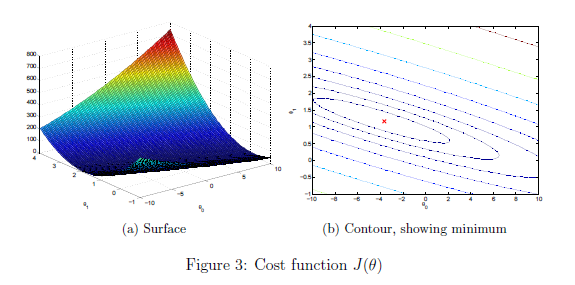

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

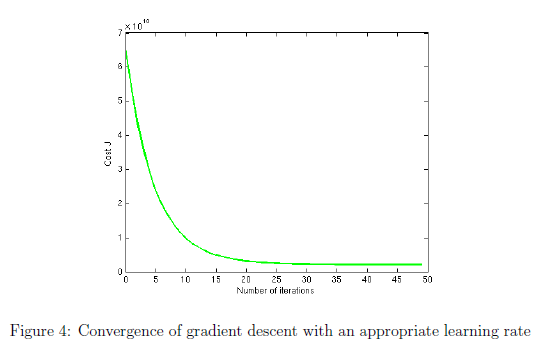

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

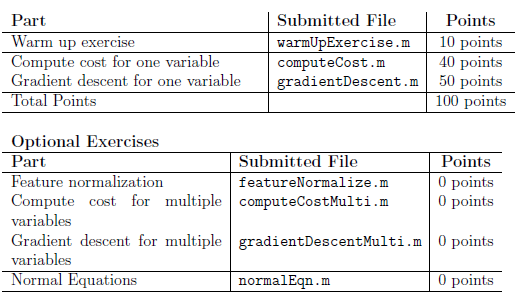

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.